# IC widefield sound evoked

% average dF traces in tmem16a cKO animals
defaultDir = 'F:\Calvin\tmem16a\widefield IC sound'

defaultDir = 'F:\Calvin\tmem16a\widefield IC sound'

cd(defaultDir);
addpath('496_2 tecta flfl','446_2 tecta flfl','453_2 tecta flfl','302_3 tecta flfl','304_2 tecta het','434_2 flfl','443_3 flfl','446_2 tecta flfl','440_4 tecta flfl','442_1 flfl','442_2 flfl','438_1 flfl','434_3 tecta flfl','434_4 flfl','306_2 tecta het','306_3 tecta flfl','319_3 flfl','329_2 tecta het','338_1 flfl','338_2 tecta flfl','338_3 tecta het','306_1 flfl','343_1 tecta flfl','346_1 flfl','440_1 tecta flfl', '440_2 tecta flfl','472_3 tecta flfl','493_2 flfl','504_1 flfl')

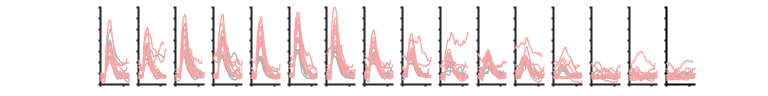

% load traces from 0, 20, 40


% played to L ear unless otherwise noted

tmem1cko0db = load('302_3_0dB.mat'); % good! L ear
tmem2cko0db = load('306_3_0dB.mat'); % good! L ear
tmem3cko0db = load('338_2_0dB.mat'); % decent
%tmem4cko0db = load('343_1_0dB.mat'); % poor quality window, right ear
tmem5cko0db = load('434_3_0dB.mat'); % r ear. not great
tmem6cko0db = load('440_1_0dB.mat'); % L ear, good
tmem7cko0db = load('440_2_0dB.mat'); % L ear, good
tmem8cko0db = load('440_4_0dB.mat'); % R ear, not great (swollen)
tmem9cko0db = load('472_3_0dB.mat'); % R ear
tmem10cko0db = load('496_2_0dB.mat'); %R ear
%tmem7cko0db.avgRIC(13,:) = NaN;

time = [1:1:length(tmem1cko0db.avgLIC)];

for i = 1:16
    avgcko0db(i,:) = nanmean([tmem1cko0db.avgRIC(i,:);tmem2cko0db.avgRIC(i,:);tmem3cko0db.avgRIC(i,:);tmem5cko0db.avgLIC(i,1:56);tmem6cko0db.avgRIC(i,1:56);tmem7cko0db.avgRIC(i,1:56);tmem8cko0db.avgLIC(i,1:56);tmem9cko0db.avgLIC(i,1:56);tmem10cko0db.avgLIC(i,1:56)],1);
    stdcko0db(i,:) = nanstd([tmem1cko0db.avgRIC(i,:);tmem2cko0db.avgRIC(i,:);tmem3cko0db.avgRIC(i,:);tmem5cko0db.avgLIC(i,1:56);tmem6cko0db.avgRIC(i,1:56);tmem7cko0db.avgRIC(i,1:56);tmem8cko0db.avgLIC(i,1:56);tmem9cko0db.avgLIC(i,1:56);tmem10cko0db.avgLIC(i,1:56)],1)/sqrt(9);
end


% controls - mixed fl/fl and cre+ hets 
con1db0 = load('304_2_0dB.mat'); % Cre+ het
con2db0 = load('319_3_0dB.mat'); % fl/fl
con3db0 = load('329_2_0dB.mat'); %Cre+ het
con4db0 = load('338_3_0dB.mat'); % played to R ear, Cre + het
con5db0 = load('338_1_0dB.mat'); %fl/fl
con6db0 = load('306_1_0dB.mat'); % fl/fl
con7db0 = load('346_1_0dB.mat'); % fl/fl
con8db0 = load('306_2_0db.mat'); % Cre+ het
con9db0 = load('434_2_0dB.mat'); % R ear fl/fl
con10db0 = load('434_4_0dB.mat'); % L ear fl/fl
con11db0 = load('438_1_0dB.mat'); % l ear flfl, good!
con12db0 = load('442_1_0dB.mat'); % l ear flfl, good!
con13db0 = load('442_1_0dB.mat'); % l ear flfl, good!
con14db0 = load('443_3_0dBmoco.mat'); % l ear flfl, good!
con15db0 = load('493_2_0dB.mat'); %L ear, movement
con16db0 = load('504_1_0dB.mat'); %L ear, ok
con5db0.avgRIC(12,:) = NaN;
con5db0.avgRIC(13,:) = NaN;

avgCon0db = [];
for i = 1:16 %fl/fl only
    avgConflfl0db(i,:) = nanmean([con2db0.avgRIC(i,:);con5db0.avgRIC(i,:);con6db0.avgRIC(i,:);con7db0.avgRIC(i,:);con9db0.avgRIC(i,1:56);con10db0.avgLIC(i,1:56);con11db0.avgRIC(i,1:56);con12db0.avgRIC(i,1:56);con13db0.avgRIC(i,1:56);con14db0.avgRIC(i,1:56);con15db0.avgRIC(i,1:56);con16db0.avgRIC(i,1:56)],1);
    stdConflfl0db(i,:) = nanstd([con2db0.avgRIC(i,:);con5db0.avgRIC(i,:);con6db0.avgRIC(i,:);con7db0.avgRIC(i,:);con9db0.avgRIC(i,1:56);con10db0.avgLIC(i,1:56);con11db0.avgRIC(i,1:56);con12db0.avgRIC(i,1:56);con13db0.avgRIC(i,1:56);con14db0.avgRIC(i,1:56);con15db0.avgRIC(i,1:56);con16db0.avgRIC(i,1:56)],1)/sqrt(12);
end
for i = 1:16 %Cre+ het
    avgConCre0db(i,:) = nanmean([con1db0.avgRIC(i,:);con3db0.avgRIC(i,:);con3db0.avgLIC(i,:);con8db0.avgRIC(i,:)],1);
    stdConCre0db(i,:) = nanstd([con1db0.avgRIC(i,:);con3db0.avgRIC(i,:);con3db0.avgLIC(i,:);con8db0.avgRIC(i,:)],1)/sqrt(4);
end
for i = 1:16 % all controls
    avgCon0db(i,:) = nanmean([con1db0.avgRIC(i,:);con3db0.avgRIC(i,:);con5db0.avgLIC(i,:);con8db0.avgRIC(i,:);con2db0.avgRIC(i,:);con5db0.avgRIC(i,:);con6db0.avgRIC(i,:);con7db0.avgRIC(i,:);con9db0.avgRIC(i,1:56);con10db0.avgLIC(i,1:56);con11db0.avgRIC(i,1:56);con12db0.avgRIC(i,1:56);con13db0.avgRIC(i,1:56);con14db0.avgRIC(i,1:56)],1);
    stdCon0db(i,:) = nanstd([con1db0.avgRIC(i,:);con3db0.avgRIC(i,:);con5db0.avgLIC(i,:);con8db0.avgRIC(i,:);con2db0.avgRIC(i,:);con5db0.avgRIC(i,:);con6db0.avgRIC(i,:);con7db0.avgRIC(i,:);con9db0.avgRIC(i,1:56);con10db0.avgLIC(i,1:56);con11db0.avgRIC(i,1:56);con12db0.avgRIC(i,1:56);con13db0.avgRIC(i,1:56);con14db0.avgRIC(i,1:56)],1)/sqrt(14);
end



% plot of all traces
l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:16
    subplot(1,16,i);
    %plot(con1db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
    hold on
    plot(con2db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(con3db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(con4db0.avgLIC(i,:),'Color',l_grey,'LineWidth',1)
    plot(con5db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
    plot(con6db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
    plot(con7db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
      plot(con9db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
         plot(con10db0.avgLIC(i,:),'Color',l_grey,'LineWidth',1)
            plot(con11db0.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
   plot(tmem1cko0db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
    plot(tmem2cko0db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
     plot(tmem3cko0db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
     plot(tmem5cko0db.avgLIC(i,:),'Color',l_red,'LineWidth',1)
       plot(tmem6cko0db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
         plot(tmem7cko0db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
         plot(tmem8cko0db.avgLIC(i,:),'Color',l_red,'LineWidth',1)
         plot(tmem9cko0db.avgLIC(i,:),'Color',l_red,'LineWidth',1)
    %plot(time,avgCon0db(i,:),'k','LineWidth',2);
    %plot(avgcko0db(i,:),'r','LineWidth',2)
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[8 1])

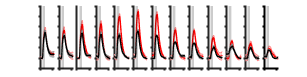


% standard error 
figure
for i = 1:13
    subplot(1,13,i);
    c1 = shadedErrorBar(time,avgcko0db(i,:)-min(avgcko0db(i,:))+0.05,stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
     c = shadedErrorBar(time,avgConflfl0db(i,:)-min(avgConflfl0db(i,:))+0.05,stdConflfl0db(i,:));
    c.mainLine.LineWidth = 1;
     hold on
    % c = shadedErrorBar(time,avgConCre0db(i,:),stdConCre0db(i,:),'lineprops','b');
   % c.mainLine.LineWidth = 1.5;
    ylim([0 0.30])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])

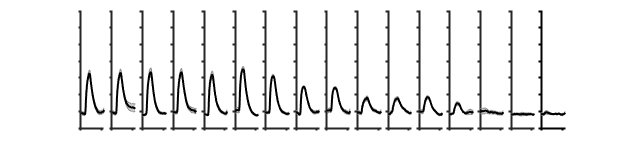

%print(gcf,'-dpdf')

% plot separately

figure
for i = 1:16
    subplot(1,16,i);
    c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
    c.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

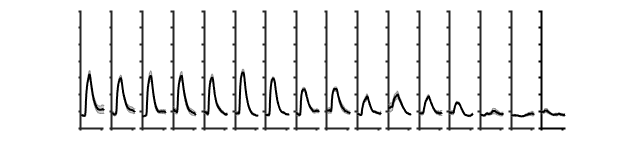

%print(gcf,'-dpdf')

figure
for i = 1:16
    subplot(1,16,i);
    c = shadedErrorBar(time,avgConflfl0db(i,:),stdConflfl0db(i,:));
    c.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

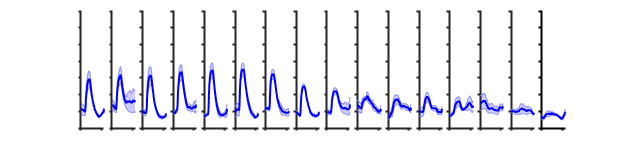

%print(gcf,'-dpdf')

figure
for i = 1:16
    subplot(1,16,i);
    c = shadedErrorBar(time,avgConCre0db(i,:),stdConCre0db(i,:),'lineprops','b');
    c.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

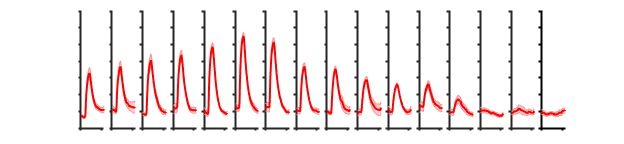

%print(gcf,'-dpdf')

figure
for i = 1:16
    subplot(1,16,i);
    c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[6.5 1.5])

%print(gcf,'-dpdf')

% plot frewer freqeuncies
% figure
% rep = 0
% for i = 1:2:15
%     subplot(1,8,i-rep);
%     c = shadedErrorBar(time,avgCon0db(i,:),stdCon0db(i,:));
%     c.mainLine.LineWidth = 1.5;
%     hold on
%     c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
%     c1.mainLine.LineWidth = 1.5;
%     ylim([0 0.35])
%     yticklabels([]);
%     xticklabels([]);
%     rep = rep + 1
% end
% figQuality(gcf,gca,[6.5 1.5])

% get gain - 0 db

for i = 1:13
    cko0dbMax(i,:) = [max([tmem2cko0db.avgRIC(i,5:20)]),max([tmem5cko0db.avgLIC(i,5:20)]),max([tmem6cko0db.avgRIC(i,5:20)]),max([tmem8cko0db.avgLIC(i,5:20)]),max([tmem10cko0db.avgLIC(i,5:20)]),max([tmem1cko0db.avgRIC(i,5:20)]),max([tmem3cko0db.avgRIC(i,5:20)]),max([tmem7cko0db.avgRIC(i,5:20)]),max([tmem9cko0db.avgLIC(i,5:20)])];
    con0dbMax(i,:) = [max([con2db0.avgRIC(i,5:20)]),max([con6db0.avgRIC(i,5:20)]),max([con9db0.avgRIC(i,5:20)]),max([con11db0.avgRIC(i,5:20)]),max([con12db0.avgRIC(i,5:20)]),max([con13db0.avgRIC(i,5:20)]),max([con15db0.avgRIC(i,5:20)]),max([con16db0.avgRIC(i,5:20)]),max([con5db0.avgRIC(i,5:20)]),max([con7db0.avgRIC(i,5:20)]),max([con10db0.avgLIC(i,5:20)]),max([con14db0.avgRIC(i,5:20)]),];
end
meancko0Gain = mean([cko0dbMax],2);
stdcko0Gain = std(cko0dbMax,1,2)/sqrt(9);
meancon0Gain = mean([con0dbMax],2);
stdcon0Gain = std(con0dbMax,1,2)/sqrt(12);




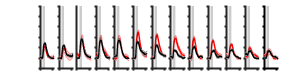



% 20 dB atten 

% adjusting ROI for IC size visible
tmem1cko20db = load('302_3_20dB.mat');
tmem2cko20db = load('306_3_20dB.mat');
tmem3cko20db = load('338_2_20dB.mat');
tmem4cko20db = load('343_1_20dB.mat'); % not great window, left IC
tmem5cko20db = load('434_3_20dB.mat'); % L IC
tmem6cko20db = load('440_1_20dB.mat'); % L ear, good
tmem7cko20db = load('440_2_20dB.mat'); % L ear, good
tmem8cko20db = load('440_4_20dB.mat'); % R ear, not great (swollen)
tmem10cko20db = load('496_2_20dB.mat'); % R ear

% tmem6cko20db.avgRIC(1,:) = NaN;
% tmem6cko20db.avgRIC(2,:) = NaN;
% tmem7cko20db.avgRIC(1,:) = NaN;
% tmem7cko20db.avgRIC(2,:) = NaN;
% tmem6cko20db.avgRIC(12,:) = NaN;
% tmem6cko20db.avgRIC(13,:) = NaN;
% tmem3cko20db.avgRIC(13,:) = NaN;
% tmem7cko20db.avgRIC(13,:) = NaN;
% tmem8cko20db.avgLIC(13,:) = NaN;

time = [1:1:length(tmem1cko20db.avgLIC)];
for i = 1:16
    avgcko20db(i,:) = nanmean([tmem1cko20db.avgRIC(i,:);tmem2cko20db.avgRIC(i,:);tmem3cko20db.avgRIC(i,:);tmem5cko20db.avgLIC(i,1:56);tmem6cko20db.avgRIC(i,1:56);tmem7cko20db.avgRIC(i,1:56);tmem8cko20db.avgLIC(i,1:56);tmem10cko20db.avgLIC(i,1:56);],1);
    stdcko20db(i,:) = nanstd([tmem1cko20db.avgRIC(i,:);tmem2cko20db.avgRIC(i,:);tmem3cko20db.avgRIC(i,:);tmem5cko20db.avgLIC(i,1:56);tmem6cko20db.avgRIC(i,1:56);tmem7cko20db.avgRIC(i,1:56);tmem8cko20db.avgLIC(i,1:56);tmem10cko20db.avgLIC(i,1:56);],1)/sqrt(8);
end


% controls - mixed fl/fl and cre+ hets 
con1db20 = load('304_2_20dB.mat');
con2db20 = load('319_3_20dB.mat');
con3db20 = load('329_2_20dB.mat');
con4db20 = load('338_3_20dB.mat'); % played to R ear
con5db20 = load('338_1_20dB.mat');
con6db20 = load('306_1_20dB.mat');
con7db20 = load('346_1_20dB.mat');
con8db20 = load('306_2_20dB.mat');
con9db20 = load('434_2_20dB.mat');
con10db20 = load('434_4_20dB.mat');
con11db20 = load('438_1_20dB.mat');
con12db20 = load('442_1_20dB.mat');
con13db20 = load('442_1_20dB.mat');
con15db20 = load('493_2_20dB.mat');
con16db20 = load('504_1_20dB.mat');

avgCon20db = [];
for i = 1:16 
    stdCon20db(i,:) = nanstd([con1db20.avgRIC(i,:);con2db20.avgRIC(i,:);con3db20.avgRIC(i,:);con4db20.avgLIC(i,:);con5db20.avgRIC(i,:);con6db20.avgRIC(i,:);con7db20.avgRIC(i,:);con8db20.avgRIC(i,:)],1)/sqrt(8);
    avgCon20db(i,:) = nanmean([con1db20.avgRIC(i,:);con2db20.avgRIC(i,:);con3db20.avgRIC(i,:);con4db20.avgLIC(i,:);con5db20.avgRIC(i,:);con6db20.avgRIC(i,:);con7db20.avgRIC(i,:);con8db20.avgRIC(i,:)],1);
end

for i = 1:16 %fl/fl only
    avgConflfl20db(i,:) = nanmean([con2db20.avgRIC(i,:);con5db20.avgRIC(i,:);con6db20.avgRIC(i,:);con7db20.avgRIC(i,:);con9db20.avgRIC(i,1:56);con10db20.avgLIC(i,1:56);con11db20.avgRIC(i,1:56);con12db20.avgRIC(i,1:56);con13db20.avgRIC(i,1:56);con15db20.avgRIC(i,1:56);con16db20.avgRIC(i,1:56)],1);
    stdConflfl20db(i,:) = nanstd([con2db20.avgRIC(i,:);con5db20.avgRIC(i,:);con6db20.avgRIC(i,:);con7db20.avgRIC(i,:);con9db20.avgRIC(i,1:56);con10db20.avgLIC(i,1:56);con11db20.avgRIC(i,1:56);con12db20.avgRIC(i,1:56);con13db20.avgRIC(i,1:56);con15db20.avgRIC(i,1:56);con16db20.avgRIC(i,1:56)],1)/sqrt(11);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];

figure
for i = 1:13
    subplot(1,13,i);
     c1 = shadedErrorBar(time,avgcko20db(i,:)-min(avgcko20db(i,:))+0.05,stdcko20db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    c = shadedErrorBar(time,avgConflfl20db(i,:)-min(avgConflfl20db(i,:))+0.05,stdConflfl20db(i,:));
    c.mainLine.LineWidth = 1;
    ylim([0 0.30])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);

end
figQuality(gcf,gca,[3.2 0.8])

%print(gcf,'-dpdf')

for i = 1:13
    cko20dbMax(i,:) = [max([tmem2cko20db.avgRIC(i,5:20)]),max([tmem5cko20db.avgLIC(i,5:20)]),max([tmem6cko20db.avgRIC(i,5:20)]),max([tmem8cko20db.avgLIC(i,5:20)]),max([tmem10cko20db.avgLIC(i,5:20)]),max([tmem1cko20db.avgRIC(i,5:20)]),max([tmem3cko20db.avgRIC(i,5:20)]),max([tmem7cko20db.avgRIC(i,5:20)])];
    con20dbMax(i,:) = [max([con2db20.avgRIC(i,5:20)]),max([con6db20.avgRIC(i,5:20)]),max([con9db20.avgRIC(i,5:20)]),max([con11db20.avgRIC(i,5:20)]),max([con12db20.avgRIC(i,5:20)]),max([con13db20.avgRIC(i,5:20)]),max([con15db20.avgRIC(i,5:20)]),max([con16db20.avgRIC(i,5:20)]),max([con5db20.avgRIC(i,5:20)]),max([con7db20.avgRIC(i,5:20)]),max([con10db20.avgLIC(i,5:20)])];
end
meancko20Gain = mean([cko20dbMax],2);
stdcko20Gain = std(cko20dbMax,1,2)/sqrt(8);
meancon20Gain = mean([con20dbMax],2);
stdcon20Gain = std(con20dbMax,1,2)/sqrt(11);


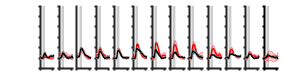


% 40 dB
tmem1cko40db = load('302_3_40dB.mat');
tmem2cko40db = load('306_3_40dB.mat');
tmem3cko40db = load('338_2_40dB.mat');
%tmem4cko40db = load('343_1_40dB.mat'); % R ear, not great
tmem5cko40db = load('434_3_40dB.mat');
tmem6cko40db = load('440_1_40dB.mat'); % L ear, good
tmem7cko40db = load('440_2_40dB.mat'); % L ear, good
tmem8cko40db = load('440_4_40dB.mat'); % R ear, not great (swollen)
tmem10cko40db = load('496_2_40dB.mat'); %R ear
% drop 1, 2, 13
%tmem1cko40db.avgRIC(13,:) = NaN;
% tmem2cko40db.avgRIC(12,:) = NaN;
% tmem3cko40db.avgRIC(12,:) = NaN;
% tmem5cko40db.avgLIC(12,:) = NaN;
% tmem6cko40db.avgRIC(4,:) = NaN;
% tmem6cko40db.avgRIC(8,:) = NaN;
% tmem6cko40db.avgRIC(10,:) = NaN;
% tmem6cko40db.avgRIC(11,:) = NaN;
% tmem6cko40db.avgRIC(12,:) = NaN;
% tmem7cko40db.avgRIC(3,:) = NaN;
% tmem7cko40db.avgRIC(4,:) = NaN;
% tmem7cko40db.avgRIC(8,:) = NaN;
% tmem7cko40db.avgRIC(10,:) = NaN;
% tmem7cko40db.avgRIC(11,:) = NaN;
% tmem7cko40db.avgRIC(12,:) = NaN;
% tmem8cko40db.avgLIC(12,:) = NaN;
% tmem8cko40db.avglIC(3,:) = NaN;
tmem1cko40db.avgRIC(10,:) = NaN;

time = [1:1:length(tmem1cko40db.avgLIC)];
for i = 1:16 % only those above threshold
    avgcko40db(i,:) = nanmean([tmem1cko40db.avgRIC(i,:);tmem2cko40db.avgRIC(i,:);tmem3cko40db.avgRIC(i,:);tmem5cko40db.avgLIC(i,1:56);tmem6cko40db.avgRIC(i,1:56);tmem7cko40db.avgRIC(i,1:56);tmem8cko40db.avgLIC(i,1:56);tmem10cko40db.avgLIC(i,1:56)],1);
    stdcko40db(i,:)= nanstd([tmem1cko40db.avgRIC(i,:);tmem2cko40db.avgRIC(i,:);tmem3cko40db.avgRIC(i,:);tmem5cko40db.avgLIC(i,1:56);tmem6cko40db.avgRIC(i,1:56);tmem7cko40db.avgRIC(i,1:56);tmem8cko40db.avgLIC(i,1:56);tmem10cko40db.avgLIC(i,1:56)],1)/sqrt(8);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
% controls - mixed fl/fl and cre+ hets 
con1db40 = load('304_2_40dB.mat');
con2db40 = load('319_3_40dB.mat');
con3db40 = load('329_2_40dB.mat');
con4db40 = load('338_3_40dB.mat'); % played to R ear
con5db40 = load('338_1_40dB.mat');
con6db40 = load('306_1_40dB.mat');
con7db40 = load('346_1_40dB.mat');
con8db40 = load('306_2_40dB.mat');
con9db40 = load('434_2_40dB.mat');
%con10db40 = load('434_4_40dB.mat'); too much movement
con11db40 = load('438_1_40dB.mat');
con12db40 = load('442_1_40dB.mat');
con13db40 = load('442_1_40dB.mat');
con15db40 = load('493_2_40dB.mat');
con16db40 = load('504_1_40dB.mat');

% con6db40.avgRIC(11,:) = NaN;
% con6db40.avgRIC(12,:) = NaN;
% con2db40.avgRIC(10,:) = NaN;
% con2db40.avgRIC(11,:) = NaN;
% con2db40.avgRIC(12,:) = NaN;
% con5db40.avgRIC(3,:) = NaN;
% con5db40.avgRIC(4,:) = NaN;
% con5db40.avgRIC(8,:) = NaN;
% con5db40.avgRIC(10,:) = NaN;
% con5db40.avgRIC(11,:) = NaN;
% con5db40.avgRIC(12,:) = NaN;
% con7db40.avgRIC(12,:) = NaN;
% con9db40.avgRIC(12,:) = NaN;
% %con10db40.avgRIC(12,:) = NaN;
% con11db40.avgRIC(3,:) = NaN;
% con11db40.avgRIC(11,:) = NaN;
% con11db40.avgRIC(12,:) = NaN;
% con12db40.avgRIC(12,:) = NaN;
% con13db40.avgRIC(3,:) = NaN;
% con13db40.avgRIC(10,:) = NaN;
% con13db40.avgRIC(11,:) = NaN;
% con13db40.avgRIC(12,:) = NaN;

avgCon0db = [];
for i = 1:16
    avgCon40db(i,:) = nanmean([con1db40.avgRIC(i,:);con2db40.avgRIC(i,:);con3db40.avgRIC(i,:);con4db40.avgLIC(i,:);con5db40.avgRIC(i,:);con6db40.avgRIC(i,:);con7db40.avgRIC(i,:);con8db40.avgRIC(i,:)],1);
    stdCon40db(i,:) = nanstd([con1db40.avgRIC(i,:);con2db40.avgRIC(i,:);con3db40.avgRIC(i,:);con4db40.avgLIC(i,:);con5db40.avgRIC(i,:);con6db40.avgRIC(i,:);con7db40.avgRIC(i,:);con8db40.avgRIC(i,:)],1)/sqrt(7);
end
for i = 1:16 %fl/fl only
    avgConflfl40db(i,:) = nanmean([con2db40.avgRIC(i,:);con5db40.avgRIC(i,:);con6db40.avgRIC(i,:);con7db40.avgRIC(i,:);con9db40.avgRIC(i,1:56);con11db40.avgRIC(i,1:56);con12db40.avgRIC(i,1:56);con13db40.avgRIC(i,1:56);con15db40.avgRIC(i,1:56);con16db40.avgRIC(i,1:56);],1);
    stdConflfl40db(i,:) = nanstd([con2db40.avgRIC(i,:);con5db40.avgRIC(i,:);con6db40.avgRIC(i,:);con7db40.avgRIC(i,:);con9db40.avgRIC(i,1:56);con11db40.avgRIC(i,1:56);con12db40.avgRIC(i,1:56);con13db40.avgRIC(i,1:56);con15db40.avgRIC(i,1:56);con16db40.avgRIC(i,1:56);],1)/sqrt(10);
end

% % all traces
% figure
% for i = 1:16
%     subplot(1,16,i);
%     plot(con1db40.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     hold on
%     plot(con2db40.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(con3db40.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(con4db40.avgLIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(con5db40.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(con6db40.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
%     plot(tmem1cko40db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
%      plot(tmem2cko40db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
%       plot(tmem3cko40db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
%     plot(time,avgCon40db(i,:),'k','LineWidth',2);
%     plot(avgcko40db(i,:),'r','LineWidth',2)
%     ylim([0 0.35])
%     yticklabels([]);
%     xticklabels([]);
% end
% figQuality(gcf,gca,[8 1])

% std error plot
figure
for i = 1:13
    subplot(1,13,i);
     c1 = shadedErrorBar(time,avgcko40db(i,:)-min(avgcko40db(i,:))+0.05,stdcko40db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    c = shadedErrorBar(time,avgConflfl40db(i,:)-min(avgConflfl40db(i,:))+0.05,stdConflfl40db(i,:));
    c.mainLine.LineWidth = 1;
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);

end

figQuality(gcf,gca,[3.2 0.8])

%print(gcf,'-dpdf')
for i = 1:13
    cko40dbMax(i,:) = [max([tmem2cko40db.avgRIC(i,5:20)]),max([tmem5cko40db.avgLIC(i,5:20)]),max([tmem6cko40db.avgRIC(i,5:20)]),max([tmem8cko40db.avgLIC(i,5:20)]),max([tmem10cko40db.avgLIC(i,5:20)]),max([tmem1cko40db.avgRIC(i,5:20)]),max([tmem3cko40db.avgRIC(i,5:20)]),max([tmem7cko40db.avgRIC(i,5:20)])];
    con40dbMax(i,:) = [max([con2db40.avgRIC(i,5:20)]),max([con6db40.avgRIC(i,5:20)]),max([con9db40.avgRIC(i,5:20)]),max([con11db40.avgRIC(i,5:20)]),max([con12db40.avgRIC(i,5:20)]),max([con13db40.avgRIC(i,5:20)]),max([con15db40.avgRIC(i,5:20)]),max([con16db40.avgRIC(i,5:20)]),max([con5db40.avgRIC(i,5:20)]),max([con7db40.avgRIC(i,5:20)])];
end
meancko40Gain = nanmean([cko40dbMax],2);
stdcko40Gain = nanstd(cko40dbMax,1,2)/sqrt(8);
meancon40Gain = mean([con40dbMax],2);
stdcon40Gain = std(con40dbMax,1,2)/sqrt(10);


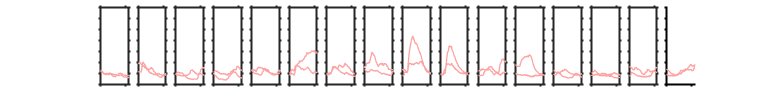

% 60 dB attenuation

%tmem1cko40db = load('302_3_40dB.mat');
tmem2cko60db = load('306_3_60dB.mat');
%tmem3cko40db = load('338_2_40dB.mat');
%tmem4cko40db = load('343_1_40dB.mat');
tmem5cko60db = load('434_3_60dB.mat');
tmem6cko60db = load('440_1_60dB.mat');
tmem8cko60db = load('440_4_60dB.mat');
tmem10cko60db = load('496_2_60dB.mat');

time = [1:1:length(tmem2cko60db.avgLIC)];
for i = 1:16
   avgcko60db(i,:) = mean([tmem2cko60db.avgRIC(i,:);tmem5cko60db.avgLIC(i,1:56);tmem6cko60db.avgRIC(i,1:56);tmem8cko60db.avgLIC(i,1:56);tmem10cko60db.avgLIC(i,1:56);],1);
   stdcko60db(i,:)= std([tmem2cko60db.avgRIC(i,:);tmem5cko60db.avgLIC(i,1:56);tmem6cko60db.avgRIC(i,1:56);tmem8cko60db.avgLIC(i,1:56);tmem10cko60db.avgLIC(i,1:56);],1)/sqrt(5);
end

% controls - mixed fl/fl and cre+ hets 
con1db60 = load('304_2_60dB.mat');
con2db60 = load('319_3_60dB.mat');
con3db60 = load('329_2_60dB.mat');
%con4db40 = load('338_3_40dB.mat'); % played to R ear
%con5db40 = load('338_1_40dB.mat');
con6db60 = load('306_1_60dB.mat');
%con7db40 = load('346_1_40dB.mat');
con9db60 = load('434_2_60dB.mat');
con10db60 = load('434_4_60dB.mat');
con11db60 = load('438_1_60dB.mat');
con12db60 = load('442_1_60dB.mat');
con13db60 = load('442_2_60dB.mat');
con15db60 = load('493_2_60dB.mat');
con16db60 = load('504_1_60dB.mat'); 
l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
% plot individuals 
for i = 1:16
    subplot(1,16,i);
    plot(tmem2cko60db.avgRIC(i,:),'Color',l_red,'LineWidth',1)
    hold on
     plot(tmem5cko60db.avgLIC(i,1:56),'Color',l_red,'LineWidth',1)
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[8 1])

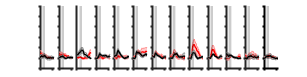


avgCon0db = [];
for i = 1:16
    avgCon60db(i,:) = mean([con1db60.avgRIC(i,:);con2db60.avgRIC(i,:);con3db60.avgRIC(i,:);con6db60.avgRIC(i,:)],1);
    stdCon60db(i,:) = std([con1db60.avgRIC(i,:);con2db60.avgRIC(i,:);con3db60.avgRIC(i,:);con6db60.avgRIC(i,:)],1)/sqrt(4);
end
for i = 1:16 %fl/fl only
    avgConflfl60db(i,:) = mean([con2db60.avgRIC(i,:);con6db60.avgRIC(i,:);con9db60.avgRIC(i,1:56);con10db60.avgLIC(i,1:56);con11db60.avgRIC(i,1:56);con12db60.avgRIC(i,1:56);con13db60.avgRIC(i,1:56);con15db60.avgRIC(i,1:56);con16db60.avgRIC(i,1:56);],1);
    stdConflfl60db(i,:) = std([con2db60.avgRIC(i,:);con6db60.avgRIC(i,:);con9db60.avgRIC(i,1:56);con10db60.avgLIC(i,1:56);con11db60.avgRIC(i,1:56);con12db60.avgRIC(i,1:56);con13db60.avgRIC(i,1:56);con15db60.avgRIC(i,1:56);con16db60.avgRIC(i,1:56);],1)/sqrt(9);
end


% std error plot
figure
for i = 1:13
    subplot(1,13,i);
    c1 = shadedErrorBar(time,avgcko60db(i,:)-min(avgcko60db(i,:))+0.05,stdcko60db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    c = shadedErrorBar(time,avgConflfl60db(i,:)-min(avgConflfl60db(i,:))+0.05,stdConflfl60db(i,:));
    c.mainLine.LineWidth = 1;
  ylim([0 0.3]) 
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])

%print(gcf,'-dpdf')

for i = 1:13
    cko60dbMax(i,:) = [max([tmem2cko60db.avgRIC(i,5:20)]),max([tmem5cko60db.avgLIC(i,5:20)]),max([tmem6cko60db.avgRIC(i,5:20)]),max([tmem8cko60db.avgLIC(i,5:20)]),max([tmem10cko60db.avgLIC(i,5:20)])];
    con60dbMax(i,:) = [max([con2db60.avgRIC(i,5:20)]),max([con6db60.avgRIC(i,5:20)]),max([con9db60.avgRIC(i,5:20)]),max([con11db60.avgRIC(i,5:20)]),max([con12db60.avgRIC(i,5:20)]),max([con13db60.avgRIC(i,5:20)]),max([con15db60.avgRIC(i,5:20)]),max([con16db60.avgRIC(i,5:20)])];
end
meancko60Gain = mean([cko60dbMax],2);
stdcko60Gain = std(cko60dbMax,1,2)/sqrt(5);
meancon60Gain = mean([con60dbMax],2);
stdcon60Gain = std(con60dbMax,1,2)/sqrt(8);
i = 10;
gainMatxCon = [con0dbMax(i,:);[con20dbMax(i,:) NaN];[con40dbMax(i,:) NaN NaN];[con60dbMax(i,:) NaN NaN NaN NaN];];
gainMatxcko = [cko0dbMax(i,:);[cko20dbMax(i,:) NaN];[cko40dbMax(i,:) NaN];[cko60dbMax(i,:) NaN NaN NaN NaN];];
gainMatx = [gainMatxCon,gainMatxcko]

gainMatx =     0.0650    0.0496    0.0955    0.0977    0.0825    0.0825    0.0604    0.1130    0.1041    0.0856    0.0811    0.1366    0.1611    0.0984    0.1406    0.1408    0.1555    0.1116    0.1319    0.1270    0.2043
    0.0586    0.0766    0.0744    0.0835    0.0928    0.0928    0.0692    0.0906    0.1055    0.0749    0.0988       NaN    0.1719    0.1159    0.1374    0.1683    0.1257    0.1095    0.1100    0.1331       NaN
    0.0900    0.0628    0.0735    0.0766    0.0620    0.0620    0.0690    0.0718    0.0664    0.0540       NaN       NaN    0.1754    0.0785    0.0465    0.0952    0.0905       NaN    0.1110    0.0506       NaN
    0.0607    0.0810    0.0559    0.0576    0.0594    0.0538    0.0579    0.0907       NaN       NaN       NaN       NaN    0.1759    0.0953    0.0548    0.0626    0.0880       NaN       NaN       NaN       NaN


% plot gain 

i = 1; % 3 kHz
x = [4:-1:1];
fig1 = figure;
c = shadedErrorBar(x,[meancon0Gain(i),meancon20Gain(i),meancon40Gain(i),meancon60Gain(i)]*100-5,[stdcon0Gain(i),stdcon20Gain(i),stdcon40Gain(i),stdcon60Gain(i)]*100)

c = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


c.mainLine.LineWidth = 1;
hold on
c1 = shadedErrorBar(x,[meancko0Gain(i),meancko20Gain(i),meancko40Gain(i),meancko60Gain(i)]*100-5,[stdcko0Gain(i),stdcko20Gain(i),stdcko40Gain(i),stdcko60Gain(i)]*100,'lineprops','r')

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


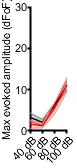

c1.mainLine.LineWidth = 1;
hold on
ylim([0 30])
xticks([1 2 3 4])
xticklabels({'40 dB','60 dB','80 dB','100 dB'})
xtickangle([45])
xlim([1 4])
ylabel('Max evoked amplitude (dFoF)')
figQuality(gcf,gca,[0.8 1.75])

%print(gcf,'-dpdf')


i = 4; % 6 kHz
x = [4:-1:1];
fig2 = figure;
c = shadedErrorBar(x,[meancon0Gain(i),meancon20Gain(i),meancon40Gain(i),meancon60Gain(i)]*100-5,[stdcon0Gain(i),stdcon20Gain(i),stdcon40Gain(i),stdcon60Gain(i)]*100)

c = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


c.mainLine.LineWidth = 1;
hold on
c1 = shadedErrorBar(x,[meancko0Gain(i),meancko20Gain(i),meancko40Gain(i),meancko60Gain(i)]*100-5,[stdcko0Gain(i),stdcko20Gain(i),stdcko40Gain(i),stdcko60Gain(i)]*100,'lineprops','r')

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


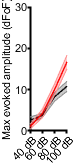

c1.mainLine.LineWidth = 1;
hold on
ylim([0 30])
xticks([1 2 3 4])
xticklabels({'40 dB','60 dB','80 dB','100 dB'})
xtickangle([45])
xlim([1 4])
ylabel('Max evoked amplitude (dFoF)')
figQuality(gcf,gca,[0.8 1.75])

%print(gcf,'-dpdf')

i = 7; % 9.5 kHz 
fig3 = figure;
c = shadedErrorBar(x,[meancon0Gain(i),meancon20Gain(i),meancon40Gain(i),meancon60Gain(i)]*100-5,[stdcon0Gain(i),stdcon20Gain(i),stdcon40Gain(i),stdcon60Gain(i)]*100)

c = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


c.mainLine.LineWidth = 1;
hold on
c1 = shadedErrorBar(x,[meancko0Gain(i),meancko20Gain(i),meancko40Gain(i),meancko60Gain(i)]*100-5,[stdcko0Gain(i),stdcko20Gain(i),stdcko40Gain(i),stdcko60Gain(i)]*100,'lineprops','r')

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


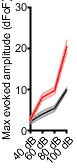

c1.mainLine.LineWidth = 1;
hold on
ylim([0 30])
xticks([1 2 3 4])
xticklabels({'40 dB','60 dB','80 dB','100 dB'})
xtickangle([45])
xlim([1 4])
ylabel('Max evoked amplitude (dFoF)')
figQuality(gcf,gca,[0.8 1.75])

%print(gcf,'-dpdf')

i = 10; % 24 kHz 
fig4 = figure;
c = shadedErrorBar(x,[meancon0Gain(i),meancon20Gain(i),meancon40Gain(i),meancon60Gain(i)]*100-5,[stdcon0Gain(i),stdcon20Gain(i),stdcon40Gain(i),stdcon60Gain(i)]*100)

c = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


c.mainLine.LineWidth = 1;
hold on
c1 = shadedErrorBar(x,[meancko0Gain(i),meancko20Gain(i),meancko40Gain(i),meancko60Gain(i)]*100-5,[stdcko0Gain(i),stdcko20Gain(i),stdcko40Gain(i),stdcko60Gain(i)]*100,'lineprops','r')

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


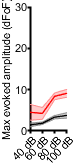

c1.mainLine.LineWidth = 1;
hold on
ylim([0 30])
xticks([1 2 3 4])
xticklabels({'40 dB','60 dB','80 dB','100 dB'})
xtickangle([45])
xlim([1 4])
ylabel('Max evoked amplitude (dFoF)')
figQuality(gcf,gca,[0.8 1.75])

%print(gcf,'-dpdf')


% stats on this 
% rm anova model - missing values causes this to not work
genoBasecon = {'con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M2','M2','M2','M2','M3','M3','M3','M3','M4','M4','M4','M4','M5','M5','M5','M5','M6','M6','M6','M6','M7','M7','M7','M7','M15','M15','M15','M15','M17','M17','M17','M17','M18','M18','M18','M18','M20','M20','M20','M20','M21','M21','M21','M21',};
mousecko = {'M8','M8','M8','M8','M9','M9','M9','M9','M10','M10','M10','M10','M11','M11','M11','M11','M12','M12','M12','M12','M13','M13','M13','M13','M14','M14','M14','M14','M16','M16','M16','M16','M19','M19','M19','M19',};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [gainMatx(:,1)',gainMatx(:,2)',gainMatx(:,3)',gainMatx(:,4)',gainMatx(:,5)',gainMatx(:,6)',gainMatx(:,7)',gainMatx(:,8)',gainMatx(:,9)',gainMatx(:,10)',gainMatx(:,11)',gainMatx(:,12)',gainMatx(:,13)',gainMatx(:,14)',gainMatx(:,15)',gainMatx(:,16)',gainMatx(:,17)',gainMatx(:,18)',gainMatx(:,19)',gainMatx(:,20)',gainMatx(:,21)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})
lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')
[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')



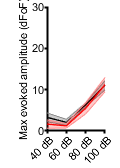

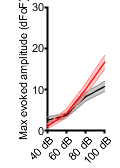

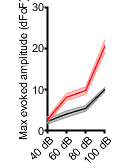

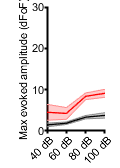


subP = handleTheSubplot({fig1,fig2,fig3,fig4},[1 4]);

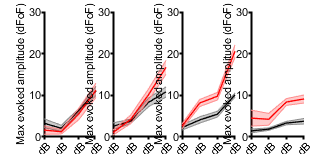

figQuality(subP,gca,[3.5 1.6])
print(gcf,'-dpdf')

% increased correlation between L and R IC? doesn't appear to be obvious

for i = 1:16
    avgckoRIC0db(i,:) = mean([tmem1cko0db.avgRIC(i,:);tmem2cko0db.avgRIC(i,:);tmem3cko0db.avgRIC(i,:)],1);
    avgckoLIC0db(i,:) = mean([tmem1cko0db.avgLIC(i,:);tmem2cko0db.avgLIC(i,:);tmem3cko0db.avgLIC(i,:)],1);
    diffcko0db(i,:) = avgckoRIC0db(i,:)-avgckoLIC0db(i,:);
end

lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

figure
for i = 1:16
  
    subplot(1,16,i);
    plot(avgckoRIC0db(i,:),'Color',dk_blue,'LineWidth',2)
    hold on
    plot(avgckoLIC0db(i,:),'Color',dk_org,'LineWidth',2)
    ylim([0 0.35])
end
figQuality(gcf,gca,[10 2])

for i = 1:16
    avgConRIC0db(i,:) = mean([con1db0.avgRIC(i,:);con2db0.avgRIC(i,:);con3db0.avgRIC(i,:);con4db0.avgLIC(i,:)],1);
    avgConLIC0db(i,:) = mean([con1db0.avgLIC(i,:);con2db0.avgLIC(i,:);con3db0.avgLIC(i,:);con4db0.avgRIC(i,:)],1);
    diffCon0db(i,:) =  avgConRIC0db(i,:)-avgConLIC0db(i,:);
end

figure
for i = 1:16
  
    subplot(1,16,i);
    plot(avgConRIC0db(i,:),'Color',dk_blue,'LineWidth',2)
    hold on
    plot(avgConLIC0db(i,:),'Color',dk_org,'LineWidth',2)
    ylim([0 0.35])
end
figQuality(gcf,gca,[10 2])

% subtracted
figure
for i = 1:16
  
    subplot(1,16,i);
    plot(diffcko0db(i,:),'Color','r','LineWidth',2)
    hold on
    plot(diffCon0db(i,:),'Color','k','LineWidth',2)
    ylim([0 0.15])
end
figQuality(gcf,gca,[10 2])


% threshold analysis 3-48 kHz

tmem10db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %302_3
tmem120db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
tmem140db = [0 0 1 1 1 1 1 1 1 1 1 1 0];

tmem20db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %306_3
tmem220db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
tmem240db = [0 0 1 1 1 1 1 1 1 1 1 0 0];
tmem260db = [0 0 0 0 1 1 1 1 1 0 0 0 0];

tmem30db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %338_2
tmem320db = [1 1 1 1 1 1 1 1 1 1 1 1 0];
tmem340db = [0 0 1 1 1 1 1 1 1 1 1 0 0];

tmem50db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 434_3
tmem520db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
tmem540db = [0 0 1 1 1 1 1 1 1 1 1 0 0];
tmem560db = [0 0 0 0 1 1 1 1 1 1 0 0 0];

tmem60db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 440_1
tmem620db = [0 1 1 1 1 1 1 1 1 1 1 0 0];
tmem640db = [0 0 1 0 1 1 1 0 1 0 0 0 0]; 
tmem660db = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

tmem70db = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 440_2
tmem720db = [1 1 1 1 1 1 1 1 1 1 1 1 0];
tmem740db = [0 0 0 0 1 1 1 0 1 0 0 0 0]; 

tmem80db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 440_4
tmem820db = [1 1 1 1 1 1 1 1 1 1 1 1 0];
tmem840db = [0 0 0 1 1 1 1 1 1 1 1 0 0];
tmem860db = [0 0 0 0 0 1 1 0 1 0 0 0 0]; 

tmem100db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %496_2
tmem1020db = [1 1 1 1 1 1 1 1 1 1 1 1 0];
tmem1030db = [1 1 1 1 1 1 1 1 1 1 1 1 0];
tmem1040db = [0 1 1 1 1 1 1 1 1 1 1 1 0];
tmem1050db = [0 0 1 1 1 1 1 1 1 1 1 0 0];
tmem1060db = [0 0 0 1 1 1 1 1 1 1 1 0 0];
tmem1070db = [0 0 0 0 1 1 1 1 1 1 0 0 0];

threshtmem1 = getThresh(tmem10db,tmem120db,tmem140db)

threshtmem1 =     72    75    57    53    54    53    52    50    60    59    60    60    78


threshtmem2 = getThresh4files(tmem20db,tmem220db,tmem240db,tmem260db)

threshtmem2 =     72    75    57    53    34    33    32    30    40    59    60    80    78


threshtmem3 = getThresh(tmem30db,tmem320db,tmem340db)

threshtmem3 =     72    75    57    53    54    53    52    50    60    59    60    80    98


threshtmem5 = getThresh4files(tmem50db,tmem520db,tmem540db,tmem560db)

threshtmem5 =     72    75    57    53    34    33    32    30    40    39    60    80    78


threshtmem6 = getThresh4files(tmem60db,tmem620db,tmem640db,tmem660db)

threshtmem6 =     92    75    57    73    54    53    52    70    60    79    80   100    98


threshtmem7 = getThresh(tmem70db,tmem720db,tmem740db)

threshtmem7 =     72    75    77    73    54    53    52    70    60    79    80    80   108


threshtmem8 = getThresh4files(tmem80db,tmem820db,tmem840db,tmem860db)

threshtmem8 =     72    75    77    53    54    33    32    50    40    59    60    80    98


threshtmem10 = getThresh4files(tmem100db,tmem1020db,tmem1040db,tmem1060db)

threshtmem10 =     72    55    57    33    34    33    32    30    40    39    40    60    98


threshtmem10(1) = threshtmem10(1)-5;
threshtmem10(3) = threshtmem10(3)-5;
threshtmem10(5:10) = threshtmem10(5:10)-5;

ckoMean = mean([threshtmem1;threshtmem2;threshtmem3;threshtmem5;threshtmem6;threshtmem7;threshtmem8;threshtmem10],1);
ckoSTD = std([threshtmem1;threshtmem2;threshtmem3;threshtmem5;threshtmem6;threshtmem7;threshtmem8;threshtmem10],1)/sqrt(8);
ckoMeanMatx = [threshtmem1(1:13)',threshtmem2(1:13)',threshtmem3(1:13)',threshtmem5(1:13)',threshtmem6(1:13)',threshtmem7(1:13)',threshtmem8(1:13)',threshtmem10(1:13)'];


tmem3 = [threshtmem1(1),threshtmem2(1),threshtmem3(1),threshtmem6(1),threshtmem5(1),threshtmem7(1),threshtmem8(1),threshtmem10(1)];
tmem6 = [threshtmem1(4),threshtmem2(4),threshtmem3(4),threshtmem6(4),threshtmem5(4),threshtmem7(4),threshtmem8(4),threshtmem10(4)];
tmem9_5 = [threshtmem1(6),threshtmem2(6),threshtmem3(6),threshtmem6(6),threshtmem5(6),threshtmem7(6),threshtmem8(6),threshtmem10(6)];
tmem12 = [threshtmem1(7),threshtmem2(7),threshtmem3(7),threshtmem6(7),threshtmem5(7),threshtmem7(7),threshtmem8(7),threshtmem10(7)];
tmem24 = [threshtmem1(10),threshtmem2(10),threshtmem3(10),threshtmem6(10),threshtmem5(10),threshtmem7(10),threshtmem8(10),threshtmem10(10)];
tmem38 = [threshtmem1(11),threshtmem2(11),threshtmem3(11),threshtmem6(11),threshtmem5(11),threshtmem7(11),threshtmem8(11),threshtmem10(11)];

con60db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %306_1 flfl
con620db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con640db = [1 1 1 1 1 1 1 1 1 1 0 0 0];
con660db = [0 0 0 0 1 1 1 0 0 0 0 0 0];

con20db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %319_3 flfl
con220db = [1 1 1 1 1 1 1 1 1 1 0 0 0];
con240db = [0 0 1 1 1 1 1 1 1 0 0 0 0];
con260db = [0 0 0 0 0 1 1 0 0 0 0 0 0];

con50db = [1 1 1 1 1 1 1 1 1 1 1 0 0]; %338_1 flfl
con520db = [1 1 1 1 1 1 1 1 1 1 0 0 0];
con540db = [0 0 0 0 1 1 1 0 1 0 0 0 0];

con80db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %346_1 fl/fl
con820db = [1 1 1 1 1 1 1 1 1 1 1 0 0];
con840db = [1 1 1 1 1 1 1 1 1 1 1 0 0];

con90db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %434_2 fl/fl
con920db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con940db = [0 1 1 1 1 1 1 1 1 1 1 0 0];
con960db = [0 0 0 0 1 1 1 0 0 0 0 0 0];

con100db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %434_4 fl/fl
con1020db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1040db = [0 0 1 1 1 1 1 1 1 1 1 0 0];
con1060db = [0 0 0 0 1 1 1 0 0 0 0 0 0];

con110db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %438_1
con1120db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1140db = [0 1 1 1 1 1 1 1 1 1 1 0 0];
con1160db = [0 0 0 1 1 1 1 1 1 1 0 0 0];
con1180db = [0 0 0 0 0 0 0 0 0 0 0 0 0];

con120db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %442_1
con1220db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1240db = [0 1 1 1 1 1 1 1 1 1 1 0 0];
con1260db = [0 0 0 1 1 1 1 1 0 0 0 0 0];

con130db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %442_2
con1320db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1340db = [0 0 0 1 1 1 1 1 1 0 0 0 0];
con1360db = [0 0 0 0 0 0 0 0 0 0 0 0 0];

con150db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; 
con1520db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %493_2
con1540db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1550db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1560db = [0 0 1 1 1 1 1 0 0 0 0 0 0];

con160db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; 
con1620db = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %504_1
con1640db = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1650db = [0 0 1 1 1 1 1 1 1 1 1 1 0];
con1660db = [0 0 1 1 1 1 1 1 1 1 1 1 0];
con1670db = [0 0 1 1 1 1 1 1 1 1 0 0 0];

threshCon6 = getThresh4files(con60db,con620db,con640db,con660db)

threshCon6 =     52    55    57    53    34    33    32    50    60    59    80    80    78


threshCon2 = getThresh4files(con20db,con220db,con240db,con260db)

threshCon2 =     72    75    57    53    54    33    32    50    60    79   100   100    98


threshCon5 = getThresh(con50db,con520db,con540db)

threshCon5 =     72    75    77    73    54    53    52    70    60    79   100   110   108


threshCon8 = getThresh(con80db,con820db,con840db)

threshCon8 =     52    55    57    53    54    53    52    50    60    59    60   100    98


threshCon9 = getThresh4files(con90db,con920db,con940db,con960db)

threshCon9 =     72    55    57    53    34    33    32    50    60    59    60    80    78


threshCon10 = getThresh4files(con100db,con1020db,con1040db,con1060db)

threshCon10 =     72    75    57    53    34    33    32    50    60    59    60    80    78


threshCon11 = getThresh4files(con110db,con1120db,con1140db,con1160db)

threshCon11 =     72    55    57    33    34    33    32    30    40    39    60    80    78


threshCon12 = getThresh4files(con120db,con1220db,con1240db,con1260db)

threshCon12 =     72    55    57    33    34    33    32    30    60    59    60    80    78


threshCon13 = getThresh4files(con130db,con1320db,con1340db,con1360db)

threshCon13 =     72    75    77    53    54    53    52    50    60    79    80    80    78


threshCon15 = getThresh4files(con150db,con1520db,con1540db,con1560db)

threshCon15 =     52    55    37    33    34    33    32    50    60    59    60    60    58


threshCon15(1:2) = threshCon15(1:2)-5;
threshCon15(8:13) = threshCon15(8:13)-5;
threshCon16 = getThresh4files(con150db,con1520db,con1540db,con1560db)

threshCon16 =     52    55    37    33    34    33    32    50    60    59    60    60    58


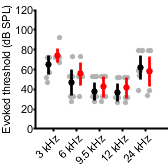

threshCon16(1:2) = threshCon16(1:2)+5;
threshCon16(13) = threshCon16(13)+5;
threshCon16(3:10) = threshCon16(3:10)-5;
con3 = [threshCon6(1),threshCon2(1),threshCon5(1),threshCon8(1),threshCon9(1),threshCon10(1),threshCon11(1),threshCon12(1),threshCon13(1),threshCon15(1),threshCon16(1)];
con6 = [threshCon6(4),threshCon2(4),threshCon5(4),threshCon8(4),threshCon9(4),threshCon10(4),threshCon11(4),threshCon12(4),threshCon13(4),threshCon15(4),threshCon16(4)];
con9_5 = [threshCon6(6),threshCon2(6),threshCon5(6),threshCon8(6),threshCon9(6),threshCon10(6),threshCon11(6),threshCon12(6),threshCon13(6),threshCon15(6),threshCon16(6)];
con12 = [threshCon6(7),threshCon2(7),threshCon5(7),threshCon8(7),threshCon9(7),threshCon10(7),threshCon11(7),threshCon12(7),threshCon13(7),threshCon15(7),threshCon16(7)];
con24 = [threshCon6(10),threshCon2(10),threshCon5(10),threshCon8(10),threshCon9(10),threshCon10(10),threshCon11(10),threshCon12(10),threshCon13(10),threshCon15(10),threshCon16(10)];
con38 = [threshCon6(11),threshCon2(11),threshCon5(11),threshCon8(11),threshCon9(11),threshCon10(11),threshCon11(11),threshCon12(11),threshCon13(11),threshCon15(11)];

conMean = mean([threshCon6;threshCon2;threshCon5;threshCon8;threshCon9;threshCon10;threshCon11;threshCon12;threshCon13;threshCon15;threshCon16]); 
conSTD = std([threshCon6;threshCon2;threshCon5;threshCon8;threshCon9;threshCon10;threshCon11;threshCon12;threshCon13;threshCon15;threshCon16])/sqrt(11); 
conMeanMatx = [threshCon6(1:13)',threshCon2(1:13)',threshCon5(1:13)',threshCon8(1:13)',threshCon9(1:13)',threshCon10(1:13)',threshCon11(1:13)',threshCon12(1:13)',threshCon13(1:13)',threshCon15(1:13)',threshCon16(1:13)'];

conditions = {'3 kHz','6 kHz','9.5 kHz','12 kHz','24 kHz'};
figure
hold on
ylbl = 'Evoked threshold (dB SPL)';
dim = [1.75 1.75];
markSz = [17 17];
color1 = 'k';
color2 = 'r';
compare5offsetM(con3,con6,con9_5,con12,con24,conditions,ylbl,dim,markSz,color1,color1)
compare5offsetP(tmem3,tmem6,tmem9_5,tmem12,tmem24,conditions,ylbl,dim,markSz,color2,color1)
ylim([0 120])


% genoBasecon = {'con','con','con','con','con'};
% genoBasecko = {'cko','cko','cko','cko','cko'};
% 
% geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
% mousecon = {'M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M19','M19','M19','M19','M19'};
% mousecko = {'M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M15','M15','M15','M15','M15','M16','M16','M16','M16','M16','M17','M17','M17','M17','M17','M18','M18','M18','M18','M18'};
% mouse = [mousecon,mousecko]';
% locationBase = {'4','5','6','7','8'}; 
% location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
% THcon = [con3(1),con6(1),con9_5(1),con12(1),con24(1),con3(2),con6(2),con9_5(2),con12(2),con24(2),con3(3),con6(3),con9_5(3),con12(3),con24(3),con3(4),con6(4),con9_5(4),con12(4),con24(4),con3(5),con6(5),con9_5(5),con12(5),con24(5),con3(6),con6(6),con9_5(6),con12(6),con24(6),con3(7),con6(7),con9_5(7),con12(7),con24(7),con3(8),con6(8),con9_5(8),con12(8),con24(8),con3(9),con6(9),con9_5(9),con12(9),con24(9),con3(10),con6(10),con9_5(10),con12(10),con24(10),con3(11),con6(11),con9_5(11),con12(11),con24(11),];
% THcko = [tmem3(1),tmem6(1),tmem9_5(1),tmem12(1),tmem24(1),tmem3(2),tmem6(2),tmem9_5(2),tmem12(2),tmem24(2),tmem3(3),tmem6(3),tmem9_5(3),tmem12(3),tmem24(3),tmem3(4),tmem6(4),tmem9_5(4),tmem12(4),tmem24(4),tmem3(5),tmem6(5),tmem9_5(5),tmem12(5),tmem24(5),tmem3(6),tmem6(6),tmem9_5(6),tmem12(6),tmem24(6),tmem3(7),tmem6(7),tmem9_5(7),tmem12(7),tmem24(7),tmem3(8),tmem6(8),tmem9_5(8),tmem12(8),tmem24(8)];
% PK = [THcon,THcko]';
% tbl = table(geno,mouse,location,PK,'VariableNames',{'Genotype','Mouse','Location','TH'})
% lme = fitlme(tbl,'TH~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')
% [beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

% shaded error of all
figure;
freq = [1:1:13]

freq =      1     2     3     4     5     6     7     8     9    10    11    12    13


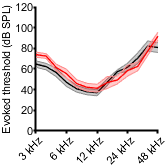

c = shadedErrorBar(freq,conMean,conSTD);
c.mainLine.LineWidth = 1;
c = shadedErrorBar(freq,ckoMean,ckoSTD,'lineprops','r');
c.mainLine.LineWidth = 1;
ylim([0 120])
xlim([1 13])
ylabel(ylbl,'FontSize',8);
xticks([1 4 7 10 13]);
xticklabels({'3 kHz','6 kHz','12 kHz','24 kHz','48 kHz'})
xtickangle([45])
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

% linear mixed model for all freqs
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11'};
mousecko = {'M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17','M18','M18','M18','M18','M18','M18','M18','M18','M18','M18','M18','M18','M18','M19','M19','M19','M19','M19','M19','M19','M19','M19','M19','M19','M19','M19'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11','12','13'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',conMeanMatx(:,7)',conMeanMatx(:,8)',conMeanMatx(:,9)',conMeanMatx(:,10)',conMeanMatx(:,11)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)',ckoMeanMatx(:,6)',ckoMeanMatx(:,7)',ckoMeanMatx(:,8)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 247×4 table
    Genotype    Mouse     Location    BW
    ________    ______    ________    __

    {'con'}     {'M1'}     {'1' }     52
    {'con'}     {'M1'}     {'2' }     55
    {'con'}     {'M1'}     {'3' }     57
    {'con'}     {'M1'}     {'4' }     53
    {'con'}     {'M1'}     {'5' }     34
    {'con'}     {'M1'}     {'6' }     33
    {'con'}     {'M1'}     {'7' }     32
    {'con'}     {'M1'}     {'8' }     50
    {'con'}     {'M1'}     {'9' }     60
    {'con'}     {'M1'}     {'10'}     59
    {'con'}     {'M1'}     {'11'}     80
    {'con'}     {'M1'}     {'12'}     80
    {'con'}     {'M1'}     {'13'}     78
    {'con'}     {'M2'}     {'1' }     72
    {'con'}     {'M2'}     {'2' }     75
    {'con'}     {'M2'}     {'3' }     57


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')  

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             247
    Fixed effects coefficients           2
    Random effects coefficients         32
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1866.4    1883.9    -928.19          1856.4  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF     pValue       Lower      Upper 
    {'(Intercept)' }        57.399      4.9676     11.555    245    6.148e-25     47.614    67.183
    {'Genotype_cko'}        2.5437      4.3939    0.57892    245      0.56318    -6.1109    11.198

Random effects covariance parameters (95% CIs):
Group: Location (13 Levels)
    Name1                  Name2                  Type        

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    57.3986
    2.5437


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat      DF        pValue        Lower      Upper 
    {'(Intercept)' }        57.399      4.9676     11.555    22.105    7.7182e-11     47.099    67.698
    {'Genotype_cko'}        2.5437      4.3939    0.57892        17       0.57024    -6.7266    11.814


meanMatx = [conMeanMatx, ckoMeanMatx];


% rm anova model
geno2 = {'con','con','con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko'}';
tbl2 = table(geno2,meanMatx(1,:)',meanMatx(2,:)',meanMatx(3,:)',meanMatx(4,:)',meanMatx(5,:)',meanMatx(6,:)',meanMatx(7,:)',meanMatx(8,:)',meanMatx(9,:)',meanMatx(10,:)',meanMatx(11,:)',meanMatx(12,:)',meanMatx(13,:)','VariableNames',{'geno','f1','f2','f3','f4','f5','f6','f7','f8','f9','f10','f11','f12','f13'})

tbl2 = 19×14 table
     geno      f1    f2    f3    f4    f5    f6    f7    f8    f9    f10    f11    f12    f13
    _______    __    __    __    __    __    __    __    __    __    ___    ___    ___    ___

    {'con'}    52    55    57    53    34    33    32    50    60    59      80     80     78
    {'con'}    72    75    57    53    54    33    32    50    60    79     100    100     98
    {'con'}    72    75    77    73    54    53    52    70    60    79     100    110    108
    {'con'}    52    55    57    5

freqs = table([1 2 3 4 5 6 7 8 9 10 11 12 13]','VariableNames',{'frequencies'});
rm = fitrm(tbl2,'f1-f13~geno','WithinDesign',freqs)

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [19×14 table]
         ResponseNames: {'f1'  'f2'  'f3'  'f4'  'f5'  'f6'  'f7'  'f8'  'f9'  'f10'  'f11'  'f12'  'f13'}
    BetweenFactorNames: {'geno'}
          BetweenModel: '1 + geno'

   Within Subjects:
          WithinDesign: [13×1 table]
     WithinFactorNames: {'frequencies'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×13 table]
            Covariance: [13×13 table]


ranovatbl = ranova(rm)

ranovatbl = 3×8 table
                               SumSq     DF     MeanSq      F         pValue       pValueGG     pValueHF      pValueLB 
                               ______    ___    ______    ______    __________    __________    _________    __________

    (Intercept):frequencies     48826     12    4068.9    61.019    1.0004e-60    7.7632e-31    1.732e-47    5.0425e-07
    geno:frequencies           2516.7     12    209.72    3.1451    0.00039534     0.0077156     0.001451      0.094068
    Error(frequencies)          13603    204    66.682                                                                 



% only with 60dB included
con3 = [threshCon6(1),threshCon2(1),threshCon9(1),threshCon10(1),threshCon11(1),threshCon12(1),threshCon13(1),threshCon15(1),threshCon16(1)];
con6 = [threshCon6(4),threshCon2(4),threshCon9(4),threshCon10(4),threshCon11(4),threshCon12(4),threshCon13(4),threshCon15(4),threshCon16(4)];
con9_5 = [threshCon6(6),threshCon2(6),threshCon9(6),threshCon10(6),threshCon11(6),threshCon12(6),threshCon13(6),threshCon15(6),threshCon16(6)];
con12 = [threshCon6(7),threshCon2(7),threshCon9(7),threshCon10(7),threshCon11(7),threshCon12(7),threshCon13(7),threshCon15(7),threshCon16(7)];
con24 = [threshCon6(10),threshCon2(10),threshCon9(10),threshCon10(10),threshCon11(10),threshCon12(10),threshCon13(10),threshCon15(10),threshCon16(10)];
con38 = [threshCon6(11),threshCon2(11),threshCon9(11),threshCon10(11),threshCon11(11),threshCon12(11),threshCon13(11),threshCon15(11)];

tmem3 = [threshtmem2(1),threshtmem6(1),threshtmem5(1),threshtmem8(1),threshtmem10(1)];
tmem6 = [threshtmem2(4),threshtmem6(4),threshtmem5(4),threshtmem8(4),threshtmem10(4)];
tmem9_5 = [threshtmem2(6),threshtmem6(6),threshtmem5(6),threshtmem8(6),threshtmem10(6)];
tmem12 = [threshtmem2(7),threshtmem6(7),threshtmem5(7),threshtmem8(7),threshtmem10(7)];
tmem24 = [threshtmem2(10),threshtmem6(10),threshtmem5(10),threshtmem8(10),threshtmem10(10)];
tmem38 = [threshtmem1(11),threshtmem3(11),threshtmem6(11),threshtmem5(11),threshtmem7(11),threshtmem8(11),threshtmem10(11)];



conditions = {'3 kHz','6 kHz','9.5 kHz','12 kHz','24 kHz'};
figure
hold on
ylbl = 'Evoked threshold (dB SPL)';
dim = [1.75 1.75];
markSz = [17 17];
color1 = 'k';
color2 = 'r';
compare5offsetM(con3,con6,con9_5,con12,con24,conditions,ylbl,dim,markSz,color1,color1)
compare5offsetP(tmem3,tmem6,tmem9_5,tmem12,tmem24,conditions,ylbl,dim,markSz,color2,color1)
ylim([0 120])


% profile analysis of contralateral IC

% load profile - 0dB atten
% selected IC for image quality
% con2 = load('319_3_0dBprofile.mat');
% con11 = load('442_1_0dBprofile.mat');
% con12 = load('442_2_0dBprofile.mat');
% con13 = load('438_1_0dBprofile.mat');
% con14 = load('443_3_0dBprofile.mat');
% 
% tmem1 = load('302_3_0dBprofile.mat');
% tmem2 = load('306_3_0dBprofile.mat');
% tmem3 = load('338_2_0dBprofile.mat');
% tmem6 = load('440_1_0dBprofile.mat');
% tmem7 = load('440_2_0dBprofile.mat');
% 
% % pretty well aligned with selection at 6 kHz
% 
% % average trace - aligned to 6 khz
% tmem = struct();
% con = struct();
% x = [1:1:150];
% for i = 1:12
%     tmem(i).mean = mean([tmem6.meanLIC(i).profile';tmem7.meanLIC(i).profile';tmem1.meanLIC(i).profile';tmem2.meanLIC(i).profile';tmem3.meanLIC(i).profile';],1);
%     con(i).mean = mean([con11.meanLIC(i).profile';con12.meanLIC(i).profile';con13.meanLIC(i).profile';con2.meanLIC(i).profile';con14.meanLIC(i).profile'],1);
%     tmem(i).std = std([tmem6.meanLIC(i).profile';tmem7.meanLIC(i).profile';tmem1.meanLIC(i).profile';tmem2.meanLIC(i).profile';tmem3.meanLIC(i).profile';],1)/sqrt(5);
%     con(i).std = std([con11.meanLIC(i).profile';con12.meanLIC(i).profile';con13.meanLIC(i).profile';con2.meanLIC(i).profile';con14.meanLIC(i).profile'],1)/sqrt(5);
%     subplot(4,3,i)
%     c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%     c1.mainLine.LineWidth = 1.5;
%     hold on
%     c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
%     c1.mainLine.LineWidth = 1.5;
%     ylim([0 0.35])
% end

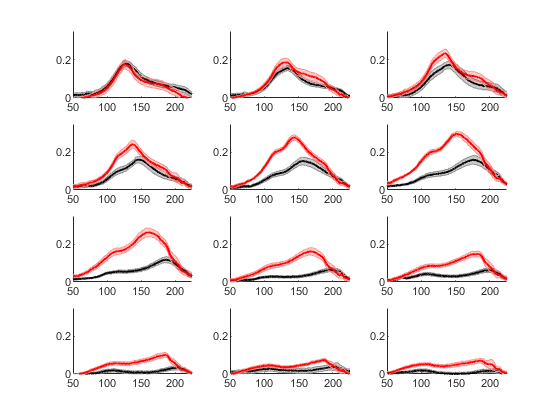


% trace aligned to 3Khz response, raw (not normalized)

con2 = load('319_3_0dBprofile3khz.mat');
con11 = load('442_1_0dBprofile3khz.mat');
con12 = load('442_2_0dBprofile3khz.mat');
con13 = load('438_1_0dBprofile3khz.mat');
con14 = load('443_3_0dBprofile3khz.mat');
con5 = load('338_1_0dBprofile3khz.mat'); %meh
con7 = load('346_1_0dBprofile3khz.mat'); % meh
con15 = load('493_2_0dBprofile3khz.mat'); % movement
con16 = load('504_1_0dBprofile3khz.mat');

tmem1 = load('302_3_0dBprofile3khz.mat');
tmem2 = load('306_3_0dBprofile3khz.mat');
tmem3 = load('338_2_0dBprofile3khz.mat');
tmem6 = load('440_1_0dBprofile3khz.mat');
tmem7 = load('440_2_0dBprofile3khz.mat');
tmem5 = load('434_3_0dBprofile3khz.mat'); % meh
tmem9 = load('472_3_0dBprofile3khz.mat');
tmem10 = load('496_2_0dBprofile3khz.mat');

% cre + controls
tecta1 = load('304_2_0dBprofile3khz.mat');
tecta2 = load('338_3_0dBprofile3khz.mat');

% all freq
figure
tmem = struct();
con = struct();
tecta = struct();
x = [1:1:250];
for i = 1:12
    tmem(i).mean = nanmean([tmem6.meanLIC(i).profileraw';tmem7.meanLIC(i).profileraw';tmem1.meanLIC(i).profileraw';tmem2.meanLIC(i).profileraw';tmem3.meanLIC(i).profileraw';tmem5.meanLIC(i).profileraw';tmem9.meanLIC(i).profileraw';tmem10.meanLIC(i).profileraw';],1)-0.1;
    con(i).mean = nanmean([con11.meanLIC(i).profileraw';con12.meanLIC(i).profileraw';con13.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con14.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con7.meanLIC(i).profileraw';con15.meanLIC(i).profileraw';con16.meanLIC(i).profileraw'],1)-0.1;
    %tecta(i).mean = nanmean([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)-0.1;
    tmem(i).std = nanstd([tmem6.meanLIC(i).profileraw';tmem7.meanLIC(i).profileraw';tmem1.meanLIC(i).profileraw';tmem2.meanLIC(i).profileraw';tmem3.meanLIC(i).profileraw';tmem5.meanLIC(i).profileraw';tmem9.meanLIC(i).profileraw';tmem10.meanLIC(i).profileraw';],1)/sqrt(8);
    con(i).std = nanstd([con11.meanLIC(i).profileraw';con12.meanLIC(i).profileraw';con13.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con14.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con7.meanLIC(i).profileraw';con15.meanLIC(i).profileraw';con16.meanLIC(i).profileraw'],1)/sqrt(9);
   % tecta(i).std = nanstd([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)/sqrt(2);
    subplot(4,3,i)
    c1 = shadedErrorBar(x,con(i).mean,con(i).std);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
     % c1 = shadedErrorBar(x,tecta(i).mean,tecta(i).std,'lineprops','b');
    %c1.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    xlim([50 225])
end

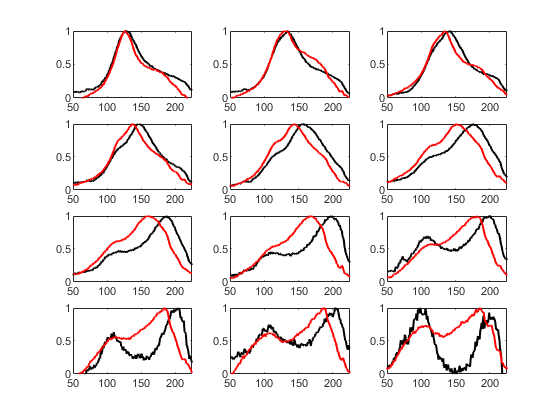


% all freq normalized

% normalized plots 
figure
for i = 1:12
    subplot(4,3,i)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    con(i).norm = con(i).mean/nanmax(con(i).mean(51:225));
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    tmem(i).norm = tmem(i).mean/nanmax(tmem(i).mean(50:225));
   % plot(tecta(i).mean/nanmax(tecta(i).mean(50:225)),'b','LineWidth',1.5)
   % tecta(i).norm = tecta(i).mean/nanmax(tecta(i).mean(50:225));
    ylim([0 1])
    xlim([50 225])
end

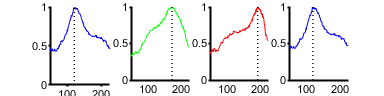

% plot examples RGB
i = 1; %3 khz response
figure
subplot(1,4,1)
plot(x,[con14.meanLIC(i).profileraw]/nanmax([con14.meanLIC(i).profileraw(52:240)]),'b');
% c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con14.meanLIC(i).profileraw(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
 
subplot(1,4,2)
i = 6;
plot(x,[con14.meanLIC(i).profileraw]/nanmax([con14.meanLIC(i).profileraw(52:240)]),'g');
% c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con14.meanLIC(i).profileraw(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
   ylim([0 1])
 xlim([50 225])
   figQuality(gcf,gca,[4 1])
   subplot(1,4,3)
   
i = 8;
plot(x,[con14.meanLIC(i).profileraw]/nanmax([con14.meanLIC(i).profileraw(52:240)]),'r');
% c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con14.meanLIC(i).profileraw(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
   ylim([0 1])
 xlim([50 225])
   figQuality(gcf,gca,[4 1])
   
   subplot(1,4,4)
   i = 1;
plot(x,[con14.meanLIC(i).profileraw]/nanmax([con14.meanLIC(i).profileraw(52:240)]),'b');
% c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con14.meanLIC(i).profileraw(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
  print(gcf,'-dpdf')

 i = 1; %3 khz response
figure
subplot(1,4,1)  
   
   plot(x,tmem1.meanLIC(i).profileraw/nanmax([tmem1.meanLIC(i).profileraw(50:240)]),'b');
 %c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem1.meanLIC(i).profileraw(50:225)))

y2_1 = 0.2950

x2_1 = 76

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])

  figQuality(gcf,gca,[4 1])
  
  subplot(1,4,2)  
   i = 6;
   plot(x,tmem1.meanLIC(i).profileraw/nanmax([tmem1.meanLIC(i).profileraw(50:240)]),'g');
 %c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem1.meanLIC(i).profileraw(50:225)))

y2_1 = 0.4641

x2_1 = 102

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])

  figQuality(gcf,gca,[4 1])
  i = 8;
  subplot(1,4,3)
     plot(x,tmem1.meanLIC(i).profileraw/nanmax([tmem1.meanLIC(i).profileraw(50:240)]),'r');
 %c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem1.meanLIC(i).profileraw(50:225)))

y2_1 = 0.2933

x2_1 = 119

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;

    ylim([0 1])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
  
   i = 1; %3 khz response
subplot(1,4,4)  
   
   plot(x,tmem1.meanLIC(i).profileraw/nanmax([tmem1.meanLIC(i).profileraw(50:240)]),'b');
 %c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem1.meanLIC(i).profileraw(50:225)))

y2_1 = 0.2950

x2_1 = 76

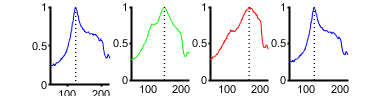

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])

  figQuality(gcf,gca,[4 1])
print(gcf,'-dpdf')

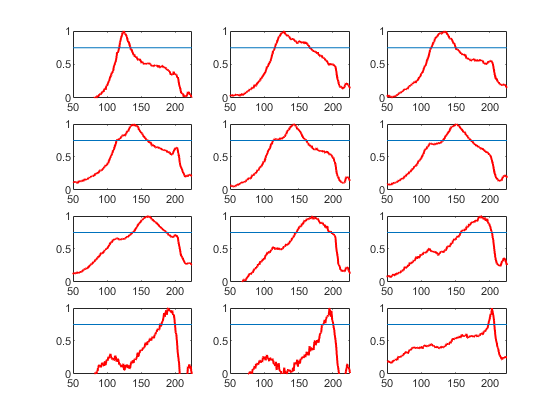


% plot individual normalized linescans
% can be a little noisy, variable - add smoothing? 
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.63; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem1BW = (tmem1.meanLIC(i).profileraw'-0.1)/(max(tmem1.meanLIC(i).profileraw(50:225)'-0.1));
    plot(tmem1BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem1bandW(i) = sum(smooth(tmem1BW(50:225))> perctile)*scale;
    [tmem1Peak(i) tmem1PeakLoc(i)] = max(smooth(tmem1.meanLIC(i).profileraw(50:225)'));
    tmem1PeakLoc(i) = tmem1PeakLoc(i)+49;
end

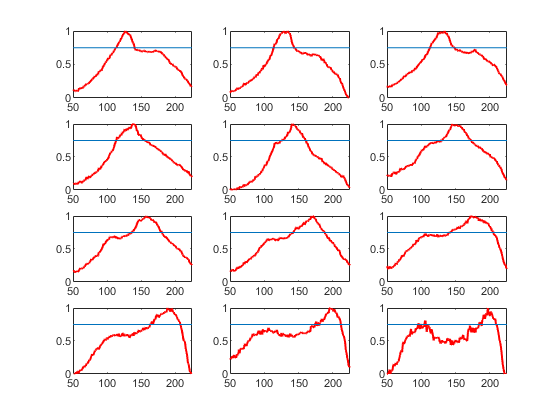

tmem1PeakLoc =  tmem1PeakLoc*scale;
tmem1pk7 = (tmem1PeakLoc(5)-tmem1PeakLoc(1));
tmem1pk12 = (tmem1PeakLoc(7)-tmem1PeakLoc(1));
tmem1pk15 = (tmem1PeakLoc(8)-tmem1PeakLoc(1));
figure
scale = 7.64; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem2BW = (tmem2.meanLIC(i).profileraw'-0.1)/(nanmax(tmem2.meanLIC(i).profileraw(50:225)'-0.1));
    plot(tmem2BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem2bandW(i) = sum(smooth(tmem2BW(50:225)) > perctile)*scale;
    [tmem2Peak(i) tmem2PeakLoc(i)] = max(smooth(tmem2.meanLIC(i).profileraw(50:225)'));
    tmem2PeakLoc(i) = tmem2PeakLoc(i)+49;
end

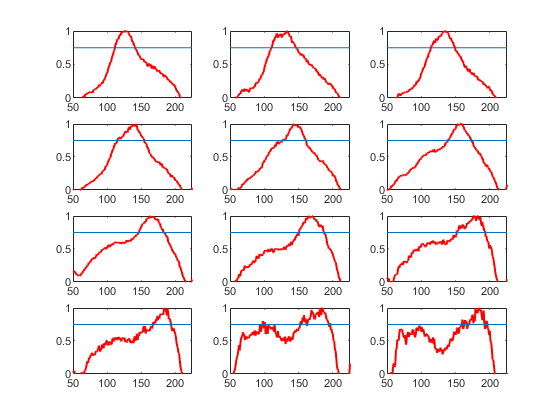

tmem2PeakLoc = tmem2PeakLoc*scale;
tmem2pk7 = (tmem2PeakLoc(5)-tmem2PeakLoc(1));
tmem2pk12 = (tmem2PeakLoc(7)-tmem2PeakLoc(1));
tmem2pk15 = (tmem2PeakLoc(8)-tmem2PeakLoc(1));
figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem3BW = (tmem3.meanLIC(i).profileraw'-0.1)/(nanmax(tmem3.meanLIC(i).profileraw(50:225)'-0.1));
    plot(tmem3BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem3bandW(i) = sum(smooth(tmem3BW(50:225)) > perctile)*scale;
    [tmem3Peak(i) tmem3PeakLoc(i)] = max(smooth(tmem3.meanLIC(i).profileraw(50:225)'));
    tmem3PeakLoc(i) = tmem3PeakLoc(i)+49;
end

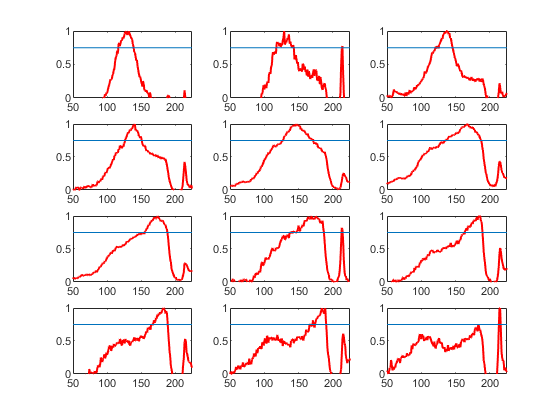

tmem3PeakLoc = tmem3PeakLoc*scale;
tmem3pk7 = (tmem3PeakLoc(5)-tmem3PeakLoc(1));
tmem3pk12 = (tmem3PeakLoc(7)-tmem3PeakLoc(1));
tmem3pk15 = (tmem3PeakLoc(8)-tmem3PeakLoc(1));
figure
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem6BW = (tmem6.meanLIC(i).profileraw'-0.1)/(nanmax(tmem6.meanLIC(i).profileraw(50:225)'-0.1));
    plot(tmem6BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem6bandW(i) = sum(smooth(tmem6BW(50:225)) > perctile)*scale;
        [tmem6Peak(i) tmem6PeakLoc(i)] = max(smooth(tmem6.meanLIC(i).profileraw(50:225)'));
    tmem6PeakLoc(i) = tmem6PeakLoc(i)+49;
end

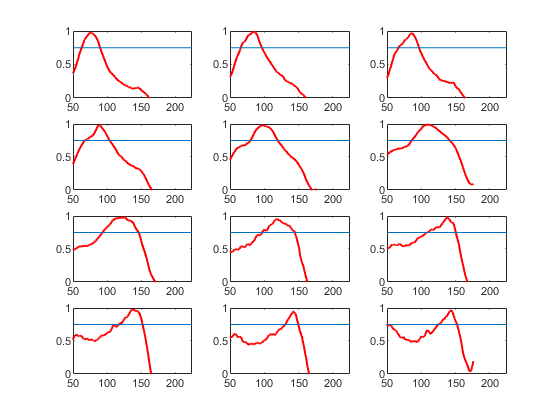

tmem6bandW(2) = NaN;
tmem6PeakLoc = tmem6PeakLoc*scale;
tmem6pk7 = (tmem6PeakLoc(5)-tmem6PeakLoc(1));
tmem6pk12 = (tmem6PeakLoc(7)-tmem6PeakLoc(1));
tmem6pk15 = (tmem6PeakLoc(8)-tmem6PeakLoc(1));
figure
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem7BW = (tmem7.meanLIC(i).profileraw'-0.1)/(nanmax(tmem7.meanLIC(i).profileraw(50:225)'-0.1));
    plot(smooth(tmem7BW(50:225)),'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem7bandW(i) = sum(smooth(tmem7BW(50:225)) > perctile)*scale;
    [tmem7Peak(i) tmem7PeakLoc(i)] = max(smooth(tmem7.meanLIC(i).profileraw(50:225)'));
    tmem7PeakLoc(i) = tmem7PeakLoc(i)+49;
end

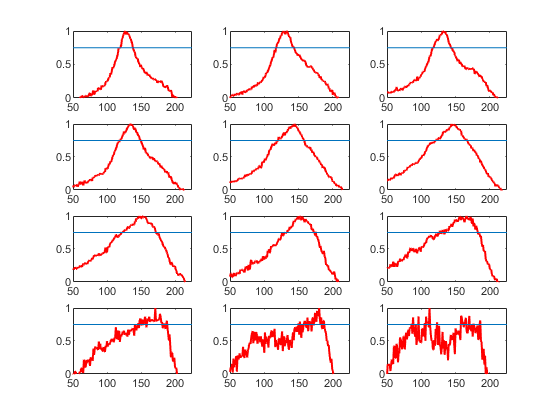

tmem7PeakLoc = tmem7PeakLoc*scale;
tmem7pk7 = (tmem7PeakLoc(5)-tmem7PeakLoc(1));
tmem7pk12 = (tmem7PeakLoc(7)-tmem7PeakLoc(1));
tmem7pk15 = (tmem7PeakLoc(8)-tmem7PeakLoc(1));

figure
scale = 7.65; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem5BW = (tmem5.meanLIC(i).profileraw'-0.1)/(nanmax(tmem5.meanLIC(i).profileraw(50:225)'-0.1));
    plot(tmem5BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem5bandW(i) = sum(smooth(tmem5BW(50:225)) > perctile)*scale;
    [tmem5Peak(i) tmem5PeakLoc(i)] = max(smooth(tmem5.meanLIC(i).profileraw(50:225)'));
    tmem5PeakLoc(i) = tmem5PeakLoc(i)+49;
end

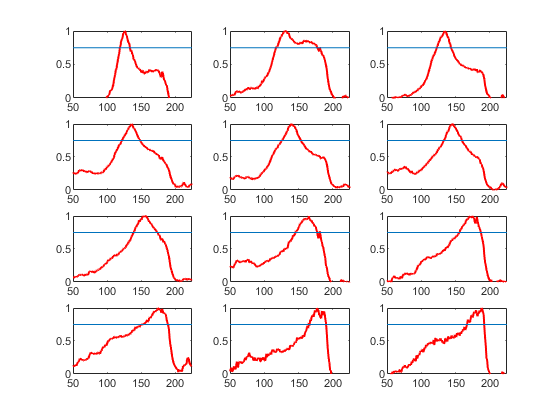

tmem5PeakLoc = tmem5PeakLoc*scale;
tmem5pk7 = (tmem5PeakLoc(5)-tmem5PeakLoc(1));
tmem5pk12 = (tmem5PeakLoc(7)-tmem5PeakLoc(1));
tmem5pk15 = (tmem5PeakLoc(8)-tmem5PeakLoc(1));
tmem5bandW(10) = NaN;
tmem5PeakLoc(10) = NaN;
figure
scale = 7.63; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem9BW = (tmem9.meanLIC(i).profileraw'-0.1)/(nanmax(tmem9.meanLIC(i).profileraw(50:225)'-0.1));
    plot(tmem9BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem9bandW(i) = sum(smooth(tmem9BW(50:225)) > perctile)*scale;
    [tmem9Peak(i) tmem9PeakLoc(i)] = max(smooth(tmem9.meanLIC(i).profileraw(50:225)'));
    tmem9PeakLoc(i) = tmem9PeakLoc(i)+49;
end

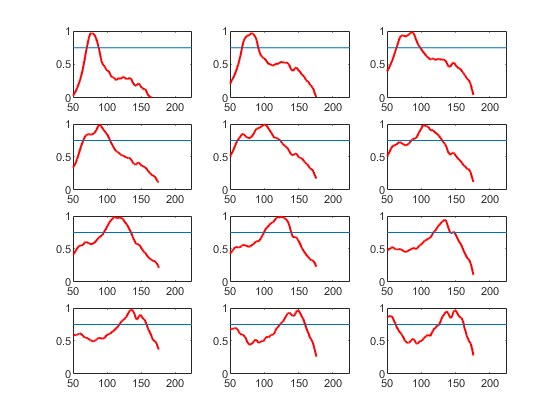

tmem9PeakLoc = tmem9PeakLoc*scale;
tmem9bandW(2) = NaN;
tmem9pk7 = (tmem9PeakLoc(5)-tmem9PeakLoc(1));
tmem9pk12 = (tmem9PeakLoc(7)-tmem9PeakLoc(1));
tmem9pk15 = (tmem9PeakLoc(8)-tmem9PeakLoc(1));

figure
scale = 7.62; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem10BW = (tmem10.meanLIC(i).profileraw'-0.1)/(nanmax(tmem10.meanLIC(i).profileraw(50:225)'-0.1));
    plot(smooth(tmem10BW(50:225)),'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem10bandW(i) = sum(smooth(tmem10BW(50:225)) > perctile)*scale;
    [tmem10Peak(i) tmem10PeakLoc(i)] = max(smooth(tmem10.meanLIC(i).profileraw(50:225)'));
    tmem10PeakLoc(i) = tmem10PeakLoc(i)+49;
end

tmem10PeakLoc = tmem10PeakLoc*scale;

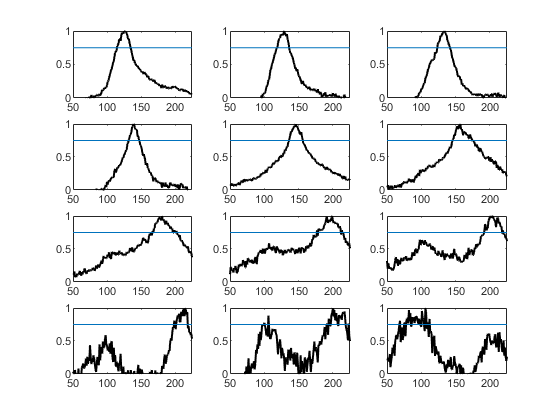

% control bandwidth
% plot individual normalized linescans
figure
perctile = 0.75; % 80th percentile, normalized
scale = 7.64; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con11BW = (con11.meanLIC(i).profileraw'-0.1)/(nanmax(con11.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con11BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con11bandW(i) = sum(smooth(con11BW(50:225)) > perctile)*scale;
    [con11Peak(i) con11PeakLoc(i)] = max(smooth(con11.meanLIC(i).profileraw(50:225)'));
    con11PeakLoc(i) = con11PeakLoc(i)+49;
end

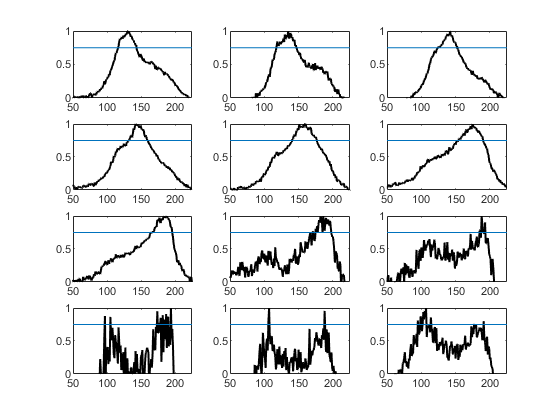

con11PeakLoc = con11PeakLoc*scale;
con11pk7 = (con11PeakLoc(5)-con11PeakLoc(1));
con11pk12 = (con11PeakLoc(7)-con11PeakLoc(1));
con11pk15 = (con11PeakLoc(8)-con11PeakLoc(1));
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con12BW = (con12.meanLIC(i).profileraw'-0.1)/(nanmax(con12.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con12BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con12bandW(i) = sum(smooth(con12BW(50:225)) > perctile)*scale;
    [con12Peak(i) con12PeakLoc(i)] = max(smooth(con12.meanLIC(i).profileraw(50:225)'));
    con12PeakLoc(i) = con12PeakLoc(i)+49;
end

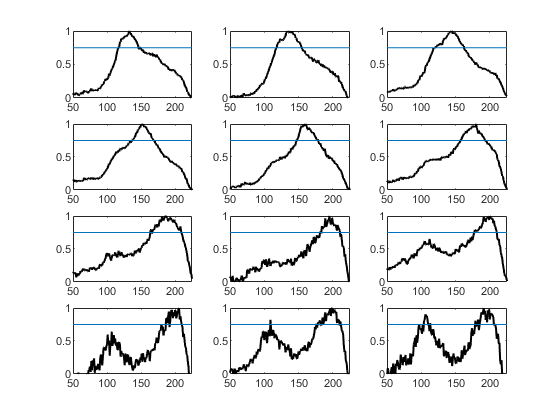

con12PeakLoc = con12PeakLoc*scale;
con12bandW(10) = NaN;
con12bandW(11) = NaN;
con12bandW(12) = NaN;
con12pk7 = (con12PeakLoc(5)-con12PeakLoc(1));
con12pk12 = (con12PeakLoc(7)-con12PeakLoc(1));
con12pk15 = (con12PeakLoc(8)-con12PeakLoc(1));
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con13BW = (con13.meanLIC(i).profileraw'-0.1)/(nanmax(con13.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con13BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con13bandW(i) = sum(smooth(con13BW(50:225)) > perctile)*scale;
        [con13Peak(i) con13PeakLoc(i)] = max(smooth(con13.meanLIC(i).profileraw(50:225)'));
    con13PeakLoc(i) = con13PeakLoc(i)+49;
end

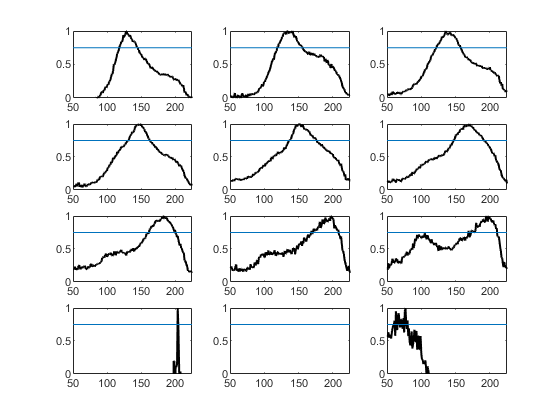

con13PeakLoc = con13PeakLoc*scale;
con13pk7 = (con13PeakLoc(5)-con13PeakLoc(1));
con13pk12 = (con13PeakLoc(7)-con13PeakLoc(1));
con13pk15 = (con13PeakLoc(8)-con13PeakLoc(1));
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con2BW = (con2.meanLIC(i).profileraw'-0.1)/(max(con2.meanLIC(i).profileraw(51:225)'-0.1));
    plot(con2BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con2bandW(i) = sum(smooth(con2BW(50:225)) > perctile)*scale;
        [con2Peak(i) con2PeakLoc(i)] = max(smooth(con2.meanLIC(i).profileraw(51:225)'));
    con2PeakLoc(i) = con2PeakLoc(i)+50;
end

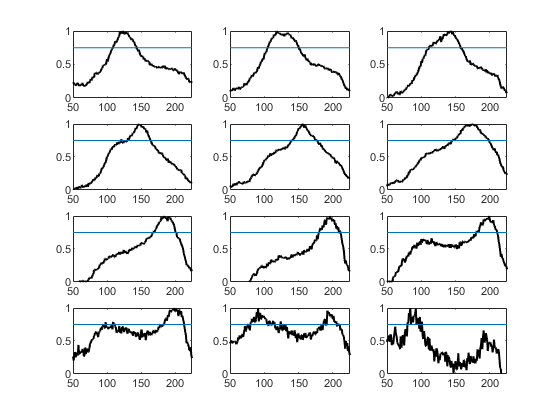

con2PeakLoc = con2PeakLoc*scale;
con2bandW(12) = NaN;
con2bandW(10) = NaN;
con2pk7 = (con2PeakLoc(5)-con2PeakLoc(1));
con2pk12 = (con2PeakLoc(7)-con2PeakLoc(1));
con2pk15 = (con2PeakLoc(8)-con2PeakLoc(1));
figure
scale = 6.85; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con14BW = (con14.meanLIC(i).profileraw'-0.1)/(nanmax(con14.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con14BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con14bandW(i) = sum(smooth(con14BW(50:225)) > perctile)*scale;
        [con14Peak(i) con14PeakLoc(i)] = max(smooth(con14.meanLIC(i).profileraw(50:225)'));
    con14PeakLoc(i) = con14PeakLoc(i)+49;
end

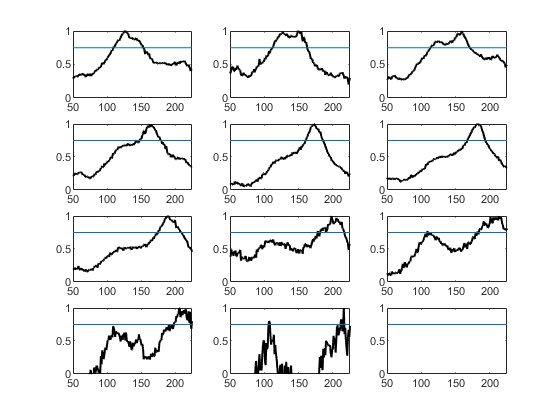

con14PeakLoc = con14PeakLoc*scale;
con14pk7 = (con14PeakLoc(5)-con14PeakLoc(1));
con14pk12 = (con14PeakLoc(7)-con14PeakLoc(1));
con14pk15 = (con14PeakLoc(8)-con14PeakLoc(1));

figure
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con5BW = (con5.meanLIC(i).profileraw'-0.1)/(nanmax(con5.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con5BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con5bandW(i) = sum(smooth(con5BW(50:225)) > perctile)*scale;
        [con5Peak(i) con5PeakLoc(i)] = max(smooth(con5.meanLIC(i).profileraw(50:225)'));
    con5PeakLoc(i) = con5PeakLoc(i)+49;
end

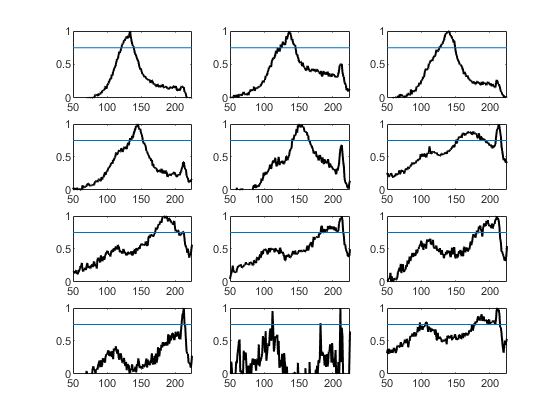

con5bandW(2) = NaN;
con5bandW(3) = NaN;
con5PeakLoc = con5PeakLoc*scale;
con5pk7 = (con5PeakLoc(5)-con5PeakLoc(1));
con5pk12 = (con5PeakLoc(7)-con5PeakLoc(1));
con5pk15 = (con5PeakLoc(8)-con5PeakLoc(1));

figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con7BW = (con7.meanLIC(i).profileraw'-0.1)/(nanmax(con7.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con7BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con7bandW(i) = sum(smooth(con7BW(50:225)) > perctile)*scale;
        [con7Peak(i) con7PeakLoc(i)] = max(smooth(con7.meanLIC(i).profileraw(50:225)'));
    con7PeakLoc(i) = con7PeakLoc(i)+49;
end

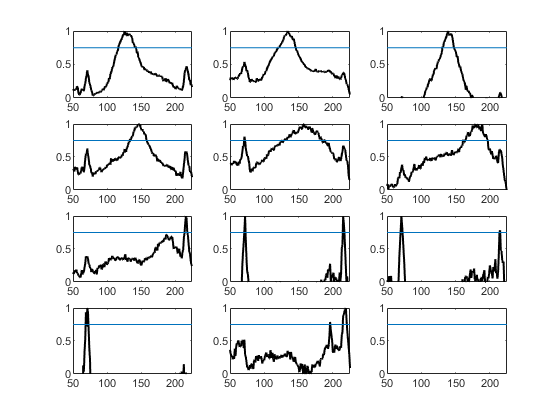

con7PeakLoc =con7PeakLoc*scale;
con7pk7 = (con7PeakLoc(5)-con7PeakLoc(1));
con7pk12 = (con7PeakLoc(7)-con7PeakLoc(1));
%con7pk15 = (con7PeakLoc(8)-con7PeakLoc(1))*scale;
con7bandW(6) = NaN;
con7PeakLoc(6) = NaN;
con7bandW(8) = NaN;
con7PeakLoc(8) = NaN;
con7bandW(9) = NaN;
con7PeakLoc(9) = NaN;
con7bandW(10) = NaN;
con7PeakLoc(10) = NaN;

figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con15BW = (con15.meanLIC(i).profileraw'-0.1)/(nanmax(con15.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con15BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con15bandW(i) = sum(smooth(con15BW(50:225)) > perctile)*scale;
        [con15Peak(i) con15PeakLoc(i)] = max(smooth(con15.meanLIC(i).profileraw(50:225)'));
    con15PeakLoc(i) = con15PeakLoc(i)+49;
end

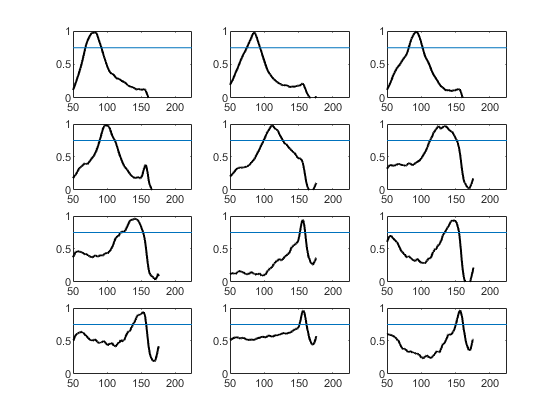

con15PeakLoc =con15PeakLoc*scale;
con15bandW(5) = NaN;
con15PeakLoc(5) = NaN;
con15bandW(7) = NaN;
con15PeakLoc(7) = NaN;
con15bandW(8) = NaN;
con15PeakLoc(8) = NaN;
con15bandW(9) = NaN;
con15PeakLoc(9) = NaN;
con15bandW(10) = NaN;
con15PeakLoc(10) = NaN;

figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con16BW = (con16.meanLIC(i).profileraw'-0.1)/(nanmax(con16.meanLIC(i).profileraw(50:225)'-0.1));
    plot(smooth(con16BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con16bandW(i) = sum(smooth(con16BW(50:225)) > perctile)*scale;
        [con16Peak(i) con16PeakLoc(i)] = max(smooth(con16.meanLIC(i).profileraw(50:225)'));
    con16PeakLoc(i) = con16PeakLoc(i)+49;
end

con16PeakLoc =con16PeakLoc*scale;
con16bandW(6) = NaN;
con16PeakLoc(6) = NaN;
con16bandW(8) = NaN;
con16PeakLoc(8) = NaN;
con16bandW(10) = NaN;
con16PeakLoc(10) = NaN;


% % compare all bw
% conditions = {'Control','cKO'};
% ylbl = 'bandwidth';
% dim = [1 1];
% figure
% conBW = struct;
% tmemBW = struct;
% for i = 1:10
%     figure
%     conBW(i).BW = [con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i)];
%     tmemBW(i).BW = [tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i)];
%     [h p] = compare2(conBW(i).BW,tmemBW(i).BW,conditions,ylbl,dim);
%     p
%     ylim([0 60]);
% end


% plot 3 - 3, 9.5, 15 kHz BW- trend towards increased BW with higher freq
% but noy yet significant with multiple comparison correction

% i = 1;
% dim = [1 1];
%   figure
%     conBW(i).BW = [con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i),con5bandW(i)];
%     tmemBW(i).BW = [tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i)];
%     [fig1 h p1] = compare2(conBW(i).BW,tmemBW(i).BW,conditions,ylbl,dim);
%     p1
%     ylim([0 60]);
%      figQuality(gcf,gca,[1 2])
% i = 6;
% dim = [1 1];
%     conBW(i).BW = [con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i),con5bandW(i)];
%     tmemBW(i).BW = [tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i)];
%     [fig2 h p2] = compare2(conBW(i).BW,tmemBW(i).BW,conditions,ylbl,dim);
%     p2
%     ylim([0 60]);
%          figQuality(gcf,gca,[1 2])
% i = 8;
% dim = [1 1];
%     conBW(i).BW = [con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i),con5bandW(i)]
%     tmemBW(i).BW = [tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i)];
%     [fig3 h p3] = compare2(conBW(i).BW,tmemBW(i).BW,conditions,ylbl,dim);
%     p3
%     ylim([0 60]);
%  figQuality(gcf,gca,[1 2])
%  
%  subP = handleTheSubplot({fig1,fig2,fig3},[1 3]);
% figQuality(subP,gca,[3 2])
% 
% 
% [CorrP CorrA h] = fdr_BH([p1,p2,p3],0.05)


% mean bandwidth
% plus smoothing, inclusion of 24 kHz
perctile = 0.75; % 80th percentile, normalized
conMeanMatx = [];
tmemMeanMatx = [];
for i = 1:10
    conbandW(i) = sum(con(i).norm(50:225) > perctile);
    tmembandW(i) = sum(tmem(i).norm(50:225) > perctile);
    conMean(i) =nanmean([con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i),con5bandW(i),con7bandW(i),con15bandW(i),con16bandW(i)]);
    conMeanMatx = [conMeanMatx;[con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i),con5bandW(i),con7bandW(i),con15bandW(i),con16bandW(i)]];
    tmemMean(i) = nanmean([tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i),tmem5bandW(i),tmem9bandW(i),tmem10bandW(i)]);
    tmemMeanMatx = [tmemMeanMatx;[tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i),tmem5bandW(i),tmem9bandW(i),tmem10bandW(i)]];
    sterrConBW(i) = nanstd([con11bandW(i),con12bandW(i),con13bandW(i),con2bandW(i),con14bandW(i),con5bandW(i),con7bandW(i),con15bandW(i),con16bandW(i)])/sqrt(9);
    sterrtmemBW(i) = nanstd([tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i),tmem5bandW(i),tmem9bandW(i),tmem10bandW(i)])/sqrt(8);    
end
scale = 7.63; %um/pixel
figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '19 kHz'};
    c1 = shadedErrorBar(k,conMean,sterrConBW)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,tmemMean,sterrtmemBW,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


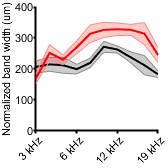

    c2.mainLine.LineWidth = 1.5;
ylim([0 400]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Normalized band width (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17'};
mousecko = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',conMeanMatx(:,7)',conMeanMatx(:,8)',conMeanMatx(:,9)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)',tmemMeanMatx(:,6)',tmemMeanMatx(:,7)',tmemMeanMatx(:,8)',]';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 170×4 table
    Genotype    Mouse     Location      BW  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }      152.8
    {'con'}     {'M1'}     {'2' }     137.52
    {'con'}     {'M1'}     {'3' }     137.52
    {'con'}     {'M1'}     {'4' }     122.24
    {'con'}     {'M1'}     {'5' }      152.8
    {'con'}     {'M1'}     {'6' }      229.2
    {'con'}     {'M1'}     {'7' }      267.4
    {'con'}     {'M1'}     {'8' }     275.04
    {'con'}     {'M1'}     {'9' }     221.56
    {'con'}     {'M1'}     {'10'}     145.16
    {'con'}     {'M2'}     {'1' }     196.02
    {'con'}     {'M2'}     {'2' }     210.54
    {'con'}     {'M2'}     {'3' }     203.28
    {'con'}     {'M2'}     {'4' }     203.28
    {'con'}     {'M2'}     {'5' }     261.36
    {'con'}     {'M2'}     {'6' }     268.62


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             151
    Fixed effects coefficients           2
    Random effects coefficients         27
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1685.7    1700.7    -837.83          1675.7  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE       tStat     DF     pValue        Lower     Upper 
    {'(Intercept)' }        221.37      15.94    13.888    149    1.1639e-28    189.87    252.87
    {'Genotype_cko'}        55.632      17.27    3.2214    149     0.0015667    21.507    89.757

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type           Est

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =   221.3713
   55.6320


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE       tStat     DF       pValue        Lower     Upper 
    {'(Intercept)' }        221.37      15.94    13.888    20.17    8.6917e-12    188.14     254.6
    {'Genotype_cko'}        55.632      17.27    3.2214    15.02        0.0057    18.827    92.437


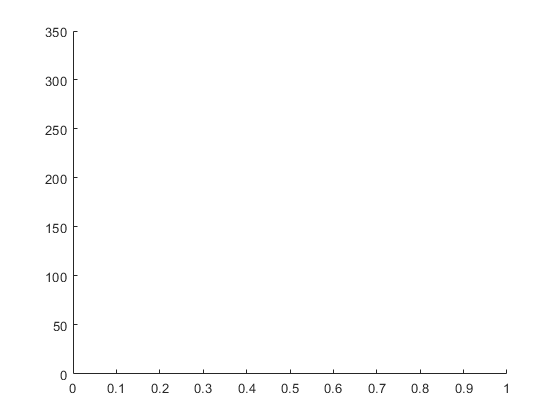


% mean BW across all fequencies
% get mean BW across all F by mouse
con40Mean = nanmean([conMeanMatx]);
tmem40Mean = nanmean([tmemMeanMatx]);
conditions = {'Control','cKO'};
dim=[1 2];
ylbl = 'Mean bandwidth (um)';


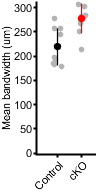

fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 22
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 0.0051

h = 1

[fig1 p h] = compare2(con40Mean,tmem40Mean,conditions,ylbl,dim)

ylim([0 350])



% plot peak location (minus 3 kHz)
conMeanMatx = [];
tmemMeanMatx = [];
for i = 1:10
    conMeanLoc(i) = nanmean([con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con2PeakLoc(i),con14PeakLoc(i),con5PeakLoc(i),con7PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)]);
    conMeanMatx = [conMeanMatx;[con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con2PeakLoc(i),con14PeakLoc(i),con5PeakLoc(i),con7PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)]];
    sterrConLoc(i) = nanstd([con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con2PeakLoc(i),con14PeakLoc(i),con5PeakLoc(i),con7PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)])/sqrt(9);
    tmemMeanLoc(i) = nanmean([tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem6PeakLoc(i),tmem7PeakLoc(i),tmem5PeakLoc(i),tmem9PeakLoc(i),tmem10PeakLoc(i)]);
    tmemMeanMatx = [tmemMeanMatx;[tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem6PeakLoc(i),tmem7PeakLoc(i),tmem5PeakLoc(i),tmem9PeakLoc(i),tmem10PeakLoc(i)]];
    sterrTmemLoc(i) = nanstd([tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem6PeakLoc(i),tmem7PeakLoc(i),tmem5PeakLoc(i),tmem9PeakLoc(i),tmem10PeakLoc(i)])/sqrt(8);
end

conMeanLoc0db = conMeanLoc;
tmemMeanLoc0db = tmemMeanLoc;
figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '19 kHz'};
    c1 = shadedErrorBar(k,conMeanLoc-conMeanLoc(1),sterrConLoc)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,tmemMeanLoc-tmemMeanLoc(1),sterrTmemLoc,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


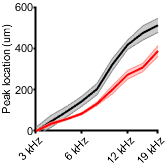

    c2.mainLine.LineWidth = 1.5;
ylim([0 600]);
xlim([1 9]);
xticks([1 4 7 9])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17'};
mousecko = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',conMeanMatx(:,7)',conMeanMatx(:,8)',conMeanMatx(:,9)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)',tmemMeanMatx(:,6)',tmemMeanMatx(:,7)',tmemMeanMatx(:,8)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 170×4 table
    Genotype    Mouse     Location      BW  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }     970.28
    {'con'}     {'M1'}     {'2' }     977.92
    {'con'}     {'M1'}     {'3' }     1016.1
    {'con'}     {'M1'}     {'4' }       1062
    {'con'}     {'M1'}     {'5' }     1115.4
    {'con'}     {'M1'}     {'6' }     1184.2
    {'con'}     {'M1'}     {'7' }     1367.6
    {'con'}     {'M1'}     {'8' }     1512.7
    {'con'}     {'M1'}     {'9' }     1543.3
    {'con'}     {'M1'}     {'10'}       1635
    {'con'}     {'M2'}     {'1' }     958.32
    {'con'}     {'M2'}     {'2' }     994.62
    {'con'}     {'M2'}     {'3' }     1016.4
    {'con'}     {'M2'}     {'4' }     1045.4
    {'con'}     {'M2'}     {'5' }     1147.1
    {'con'}     {'M2'}     {'6' }     1277.8


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             157
    Fixed effects coefficients           2
    Random effects coefficients         27
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1759.5    1774.7    -874.76          1749.5  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF     pValue        Lower      Upper  
    {'(Intercept)' }        1231.6      58.873      20.92    155    5.3683e-47     1115.3     1347.9
    {'Genotype_cko'}        -71.17      26.062    -2.7308    155     0.0070495    -122.65    -19.688

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type  

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta = 	1.0e+03 *

    1.2316
   -0.0712


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat      DF        pValue        Lower      Upper  
    {'(Intercept)' }        1231.6      58.873      20.92    10.757    4.6499e-10     1101.7     1361.6
    {'Genotype_cko'}        -71.17      26.062    -2.7308    15.231      0.015308    -126.65    -15.695



i = 1; %3 khz response
figure
subplot(1,4,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
 i = 6; %7.5  kHz
 subplot(1,4,2)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con(i).mean(51:225)));
 l1_2 = line([x1_2+50 x1_2+50],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':'
 l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(tmem(i).mean(50:225)));
 l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
 patch([x1_2+50 x1_2+50 x2_2+49 x2_2+49], [0 y2_2 y2_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
  ylim([0 0.35])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
  i = 8; % 12 kHz
 subplot(1,4,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std,'lineprops','k');
 c1.mainLine.LineWidth = 1.5;
  [y1_3 x1_3] = nanmax(smooth(con(i).mean(51:225)));
 l1_3 = line([x1_3+50 x1_3+50],[0,y1_3]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':';
 l1_3.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y2_3 x2_3] = nanmax(smooth(tmem(i).mean(50:225)));
 l2_3 = line([x2_3+49 x2_3+49],[0,y2_3]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':';
 l2_3.LineWidth = 1;
 ylim([0 0.35])
 xlim([50 225])
  patch([x1_3+50 x1_3+50 x2_3+49 x2_3+49], [0 y2_3 y2_3 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[4 1])
 i = 1;
 subplot(1,4,4)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
%print(gcf,'-dpdf')

% separated by genotype
i = 1; %3 khz response
figure
subplot(1,4,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
%  c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%  [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
%  l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
%  l2_1.Color = 'r';
%  l2_1.LineStyle = ':';
%  l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 
  i = 6; %7.5  kHz
 subplot(1,4,2)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con(i).mean(51:225)));
 l1_2 = line([x1_2+50 x1_2+50],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':'
 l1_2.LineWidth = 1;
%  c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%  [y2_2 x2_2] = nanmax(smooth(tmem(i).mean(50:225)));
%  l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
%  l2_2.Color = 'r';
%  l2_2.LineStyle = ':';
%  l2_2.LineWidth = 1;
%  patch([x1_2+50 x1_2+50 x2_2+49 x2_2+49], [0 y2_2 y2_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
   ylim([0 0.35])
 xlim([50 225])
 
  i = 8; % 12 kHz
 subplot(1,4,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std,'lineprops','k');
 c1.mainLine.LineWidth = 1.5;
  [y1_3 x1_3] = nanmax(smooth(con(i).mean(51:225)));
 l1_3 = line([x1_3+50 x1_3+50],[0,y1_3]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':';
 l1_3.LineWidth = 1;
%  c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%   [y2_3 x2_3] = nanmax(smooth(tmem(i).mean(50:225)));
%  l2_3 = line([x2_3+49 x2_3+49],[0,y2_3]);
%  l2_3.Color = 'r';
%  l2_3.LineStyle = ':';
%  l2_3.LineWidth = 1;
 ylim([0 0.35])
 xlim([50 225])
%  patch([x1_3+50 x1_3+50 x2_3+49 x2_3+49], [0 y2_3 y2_3 0],'k','EdgeColor','none','FaceAlpha',0.1);
 i = 1; %3 khz response
subplot(1,4,4)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
%  c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%  [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
%  l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
%  l2_1.Color = 'r';
%  l2_1.LineStyle = ':';
%  l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])

figQuality(gcf,gca,[4 1])
%print(gcf,'-dpdf')

i = 1; %3 khz response
figure
subplot(1,4,1)
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%  c1.mainLine.LineWidth = 1.5;
%  hold on
%  [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
%  l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
%  l1_1.Color = 'k';
%  l1_1.LineStyle = ':';
%  l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 hold on
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 
  i = 6; %7.5  kHz
 subplot(1,4,2)
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%  c1.mainLine.LineWidth = 1.5;
%  [y1_2 x1_2] = nanmax(smooth(con(i).mean(51:225)));
%  l1_2 = line([x1_2+50 x1_2+50],[0,y1_2]);
%  l1_2.Color = 'k';
%  l1_2.LineStyle = ':'
%  l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(tmem(i).mean(50:225)));
 l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
%  patch([x1_2+50 x1_2+50 x2_2+49 x2_2+49], [0 y2_2 y2_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
   ylim([0 0.35])
 xlim([50 225])
 
  i = 8; % 12 kHz
 subplot(1,4,3)
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std,'lineprops','k');
%  c1.mainLine.LineWidth = 1.5;
%   [y1_3 x1_3] = nanmax(smooth(con(i).mean(51:225)));
%  l1_3 = line([x1_3+50 x1_3+50],[0,y1_3]);
%  l1_3.Color = 'k';
%  l1_3.LineStyle = ':';
%  l1_3.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y2_3 x2_3] = nanmax(smooth(tmem(i).mean(50:225)));
 l2_3 = line([x2_3+49 x2_3+49],[0,y2_3]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':';
 l2_3.LineWidth = 1;
 ylim([0 0.35])
 xlim([50 225])
%  patch([x1_3+50 x1_3+50 x2_3+49 x2_3+49], [0 y2_3 y2_3 0],'k','EdgeColor','none','FaceAlpha',0.1);
i = 1; %3 khz response

subplot(1,4,4)
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%  c1.mainLine.LineWidth = 1.5;
%  hold on
%  [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
%  l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
%  l1_1.Color = 'k';
%  l1_1.LineStyle = ':';
%  l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 hold on
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225]) 

figQuality(gcf,gca,[4 1])
print(gcf,'-dpdf')

% plot 12-24 kHz profiles

i = 7; %3 khz response
figure
subplot(1,2,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 i = 10;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
 figQuality(gcf,gca,[2 1])

i = 7; %3 khz norm
subplot(1,2,2)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 10
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':'
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[2 1])
print(gcf,'-dpdf')



 
% figure
%% normalized plots 
% for i = 1:12
%     subplot(4,3,i)
%     plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
%     hold on
%     plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
%     ylim([0 1])
%     xlim([50 225])
% end

figure
i = 1; %3 khz norm
subplot(1,4,1)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':'
 l2_1.LineWidth = 1;

i = 6; % 7.5 khz norm
subplot(1,4,2)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
     l1_2 = line([x1_2+50 x1_2+50],[0,1]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':'
 l1_2.LineWidth = 1;
 l2_2 = line([x2_2+49 x2_2+49],[0,1]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':'
 l2_2.LineWidth = 1;
  patch([x1_2+50 x1_2+50 x2_2+49 x2_2+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[4 1])

  i = 8; %12 khz norm
subplot(1,4,3)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225]) 
         l1_3 = line([x1_3+50 x1_3+50],[0,1]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':'
 l1_3.LineWidth = 1;
 l2_3 = line([x2_3+49 x2_3+49],[0,1]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':'
 l2_3.LineWidth = 1;
   patch([x1_3+50 x1_3+50 x2_3+49 x2_3+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[4 1])
i = 1; %3 khz norm
subplot(1,4,4)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':'
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[4 1])

     print(gcf,'-dpdf')  
%   i = 8; %15 khz vs 24 kHz norm 
% subplot(1,3,3)
% i = 7;
%     plot(con(i).mean/nanmax(con(i).mean(50:225)),'b','LineWidth',1.5)
%     hold on
%     i = 10;
%     plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
%     ylim([0 1])
%     xlim([50 225]) 
%          l1_3 = line([x1_3+50 x1_3+50],[0,1]);
%  l1_3.Color = 'k';
%  l1_3.LineStyle = '--'
%  l1_3.LineWidth = 1;
%  l2_3 = line([x2_3+50 x2_3+50],[0,1]);
%  l2_3.Color = 'r';
%  l2_3.LineStyle = '--'
%  l2_3.LineWidth = 1;
% figQuality(gcf,gca,[3 1])


% Plot spatial overlap

figure
i = 1; %3 khz response
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_1c x1_1c] = nanmax(smooth(con(i).mean(51:240)));
 hold on
 i =7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))
 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1c+50 x1_1c+50],[0,y1_1c]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))
 l2_1 = line([x2_1c+50 x2_1c+50],[0,y2_1c]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 y1_1c y1_1c 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])
 
 subplot(1,3,2)
 i = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y1_1 x1_1] = nanmax(smooth(tmem(i).mean(51:240)));
 hold on
 i = 7;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))
 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))
 l2_1 = line([x2_1+50 x2_1+50],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1+50 x1_1+50 x2_1+50 x2_1+50], [0 y2_1 y2_1 0],'r','EdgeColor','none','FaceAlpha',0.1);
figQuality(gcf,gca,[3 1])
i = 1; %3 khz response
subplot(1,3,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_1c x1_1c] = nanmax(smooth(con(i).mean(51:240)));
 hold on
 i =7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))
 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1c+50 x1_1c+50],[0,y1_1c]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))
 l2_1 = line([x2_1c+50 x2_1c+50],[0,y2_1c]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 y1_1c y1_1c 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])
%print(gcf,'-dpdf') 

figure
i = 1; %3 khz
subplot(1,3,1)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 7;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1c+50 x1_1c+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1c+50 x2_1c+50],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':'
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 
%cKO
i = 1; %3 khz
subplot(1,3,2)
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    hold on
    i = 7;
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':'
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+50 x2_1+50],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':'
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1+50 x1_1+50 x2_1+50 x2_1+50], [0 1 1 0],'r','EdgeColor','none','FaceAlpha',0.1);
i = 1; %3 khz
subplot(1,3,3)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 7;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1c+50 x1_1c+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1c+50 x2_1c+50],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':'
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 print(gcf,'-dpdf') 



% plot normalized bandwith, aligned to peak
i = 5; 
[val conMax] = nanmax(smooth(con(i).mean(51:225)));
[val tmemMax] = nanmax(smooth(tmem(i).mean(51:225)));
diff = conMax - tmemMax;
x = [51:1:225];
figure
subplot(1,2,1)
    plot(x-diff,con(i).mean(51:225)/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(x,tmem(i).mean(51:225)/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l2_1 = line([50 225],[0.75,0.75]);
 l2_1.Color = 'k';
 l2_1.LineWidth = 1;
figQuality(gcf,gca,[2 1])

i = 8; 
[val conMax] = nanmax(smooth(con(i).mean(51:225)));
[val tmemMax] = nanmax(smooth(tmem(i).mean(51:225)));
diff = conMax - tmemMax;
x = [51:1:225];
subplot(1,2,2)
    plot(x-diff,con(i).mean(51:225)/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(x,tmem(i).mean(51:225)/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l2_1 = line([50 225],[0.75,0.75]);
 l2_1.Color = 'k';
 l2_1.LineWidth = 1;
figQuality(gcf,gca,[2 1])





% plot peak separation distance, by animal

tmem7pksep = [tmem1pk7,tmem2pk7,tmem3pk7,tmem6pk7,tmem7pk7,tmem5pk7,tmem9pk7]
con7pksep = [con11pk7,con12pk7,con13pk7,con2pk7,con14pk7,con5pk7,con7pk7]

con12pksep = [con11pk12,con12pk12,con13pk12,con2pk12,con14pk12,con5pk12,con7pk12]
tmem12pksep = [tmem1pk12,tmem2pk12,tmem3pk12,tmem6pk12,tmem7pk12,tmem5pk12,tmem9pk12]

con15pksep = [con11pk15,con12pk15,con13pk15,con2pk15,con14pk15,con5pk15]
tmem15pksep = [tmem1pk15,tmem2pk15,tmem3pk15,tmem6pk15,tmem7pk15,tmem5pk15,tmem9pk15]

figure;
conditions1 = {'Control','cKO'};
ylbl1 = '3-7.5 kHz spatial separation (um)';
dim1 = [1 2];
[fig1 p1 h] = compare2(con7pksep,tmem7pksep,conditions1,ylbl1,dim1)
p1
ylim([0 700])

figure;
conditions1 = {'Control','cKO'};
ylbl1 = '3-12 kHz spatial separation';
dim1 = [1 2];
[fig2 p2 h] = compare2(con12pksep,tmem12pksep,conditions1,ylbl1,dim1)
p2
ylim([0 700])

figure;
conditions1 = {'Control','cKO'};
ylbl1 = '3-15 kHz spatial separation (um)';
dim1 = [1 2];
[fig3 p3 h] = compare2(con15pksep,tmem15pksep,conditions1,ylbl1,dim1)
p3
ylim([0 700])

subP = handleTheSubplot({fig1,fig2,fig3},[1 3]);
figQuality(subP,gca,[3 2])

[CorrP CorrA h] = fdr_BH([p1,p2],0.05)

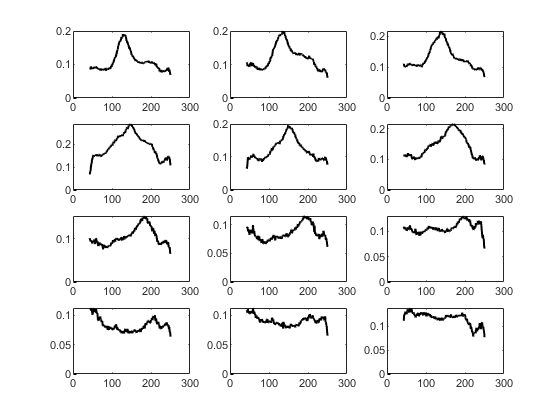

% plot linescans from lower intensity stimulation

% 80 dB SPL
con2 = load('319_3_20dBprofile3khz.mat'); 
con11 = load('442_1_20dBprofile3khz.mat');
con12 = load('442_2_20dBprofile3khz.mat');
con13 = load('438_1_20dBprofile3khz.mat');
con14 = load('443_3_20dBprofile3khz.mat');
con5 = load('338_1_20dBprofile3khz.mat'); %meh
con7 = load('346_1_20dBprofile3khz.mat');
con15 = load('493_2_20dBprofile3khz.mat'); % lots of movement
con16 = load('504_1_20dBprofile3khz.mat');

tmem1 = load('302_3_20dBprofile3khz.mat');
tmem2 = load('306_3_20dBprofile3khz.mat');
tmem3 = load('338_2_20dBprofile3khz.mat');
tmem6 = load('440_1_20dBprofile3khz.mat'); % no 3Khz, 3.7 kHz response
tmem7 = load('440_2_20dBprofile3khz.mat'); % no 3Khz, 3.7 kHz response
tmem5 = load('434_3_20dBprofile3khz.mat');
tmem9 = load('472_3_20dBprofile3khz.mat'); 
tmem10 = load('496_2_20dBprofile3khz.mat'); 

tmem6.meanLIC(1).profileraw = [NaN(1,250)]';
tmem6.meanLIC(2).profileraw = [NaN(1,250)]';

tmem7.meanLIC(1).profileraw = [NaN(1,250)]';
tmem7.meanLIC(2).profileraw = [NaN(1,250)]';

% check individual profiles
figure
for i = 1:12
    subplot(4,3,i)
    plot(con2.meanLIC(i).profileraw','k','LineWidth',1.5)
end

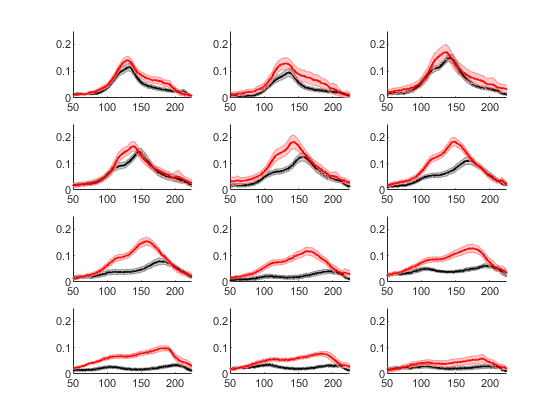



% all freq
figure
tmem = struct();
con = struct();
tecta = struct();
x = [1:1:250];
for i = 1:12
    tmem(i).mean = nanmean([tmem6.meanLIC(i).profileraw';tmem7.meanLIC(i).profileraw';tmem1.meanLIC(i).profileraw';tmem2.meanLIC(i).profileraw';tmem3.meanLIC(i).profileraw';tmem5.meanLIC(i).profileraw';tmem9.meanLIC(i).profileraw';tmem10.meanLIC(i).profileraw';],1)-0.08;
    con(i).mean = nanmean([con11.meanLIC(i).profileraw';con12.meanLIC(i).profileraw';con13.meanLIC(i).profileraw';con14.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con7.meanLIC(i).profileraw';con15.meanLIC(i).profileraw';con16.meanLIC(i).profileraw'],1)-0.08;
    %tecta(i).mean = nanmean([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)-0.1;
    tmem(i).std = nanstd([tmem6.meanLIC(i).profileraw';tmem7.meanLIC(i).profileraw';tmem1.meanLIC(i).profileraw';tmem2.meanLIC(i).profileraw';tmem3.meanLIC(i).profileraw';tmem5.meanLIC(i).profileraw';tmem9.meanLIC(i).profileraw';tmem10.meanLIC(i).profileraw';],1)/sqrt(8);
    con(i).std = nanstd([con11.meanLIC(i).profileraw';con12.meanLIC(i).profileraw';con13.meanLIC(i).profileraw';con14.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con7.meanLIC(i).profileraw';con15.meanLIC(i).profileraw';con16.meanLIC(i).profileraw'],1)/sqrt(9);
    %tecta(i).std = nanstd([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)/sqrt(2);
    subplot(4,3,i)
    c1 = shadedErrorBar(x,con(i).mean,con(i).std);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
     % c1 = shadedErrorBar(x,tecta(i).mean,tecta(i).std,'lineprops','b');
    %c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    xlim([50 225])
end

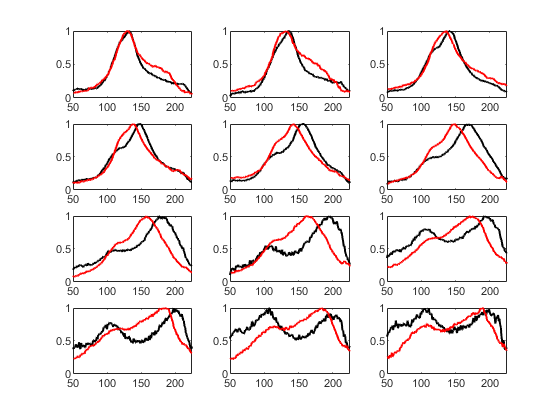


% all freq normalized

% normalized plots 
figure
for i = 1:12
    subplot(4,3,i)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    con(i).norm = con(i).mean/nanmax(con(i).mean(51:225));
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    tmem(i).norm = tmem(i).mean/nanmax(tmem(i).mean(51:225));
   % plot(tecta(i).mean/nanmax(tecta(i).mean(50:225)),'b','LineWidth',1.5)
    % tecta(i).norm = tecta(i).mean/nanmax(tecta(i).mean(50:225));
    ylim([0 1])
    xlim([50 225])
end


% for figure
i = 1; %3 khz response
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean));
 l1_1 = line([x1_1 x1_1],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))
 l2_1 = line([x2_1+50 x2_1+50],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  figQuality(gcf,gca,[3 1])
 i = 6; %9.5 kHz
 subplot(1,3,2)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con(i).mean(50:225)));
 l1_2 = line([x1_2+50 x1_2+50],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':';
 l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(tmem(i).mean(51:225)));
 l2_2 = line([x2_2+50 x2_2+50],[0,y2_2]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  patch([x1_2+50 x1_2+50 x2_2+50 x2_2+50], [0 y2_2 y2_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[3 1])
  i = 8; % 15 kHz
 subplot(1,3,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_3 x1_3] = nanmax(smooth(con(i).mean(50:225)));
 l1_3 = line([x1_3+50 x1_3+50],[0,y1_3]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':';
 l1_3.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y2_3 x2_3] = nanmax(smooth(tmem(i).mean(51:225)));
 l2_3 = line([x2_3+50 x2_3+50],[0,y2_3]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':';
 l2_3.LineWidth = 1;
 ylim([0 0.35])
 xlim([50 225])
  patch([x1_3+50 x1_3+50 x2_3+50 x2_3+50], [0 y2_3 y2_3 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])
%print(gcf,'-dpdf')


figure
i = 1; %3 khz norm
subplot(1,3,1)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1 x1_1],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+50 x2_1+50],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
i = 6; % 7.5 khz norm
subplot(1,3,2)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
     l1_2 = line([x1_2+50 x1_2+50],[0,1]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':';
 l1_2.LineWidth = 1;
 l2_2 = line([x2_2+50 x2_2+50],[0,1]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
   patch([x1_2+50 x1_2+50 x2_2+50 x2_2+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);

 figQuality(gcf,gca,[3 1])
  i = 8; %12 khz norm
subplot(1,3,3)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225]) 
         l1_3 = line([x1_3+50 x1_3+50],[0,1]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':';
 l1_3.LineWidth = 1;
 l2_3 = line([x2_3+50 x2_3+50],[0,1]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':';
 l2_3.LineWidth = 1;
   patch([x1_3+50 x1_3+50 x2_3+50 x2_3+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);

figQuality(gcf,gca,[3 1])
% print(gcf,'-dpdf') 
 
 

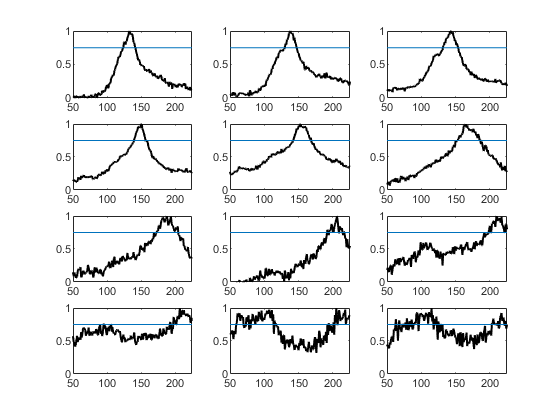

% 80 dB band width

% control bandwidth
% plot individual normalized linescans
figure
scale = 7.64; %um/pixel
perctile = 0.75; % 80th percentile, normalized
for i = 1:12
    subplot(4,3,i)
    con11BW = (con11.meanLIC(i).profileraw'-0.08)/(nanmax(con11.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con11BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con11bandW(i) = sum(con11BW(50:225) > perctile)*scale;
    [con11Peak(i) con11PeakLoc(i)] = max(smooth(con11.meanLIC(i).profileraw(50:225)'));
    con11PeakLoc(i) = con11PeakLoc(i)+49;
end

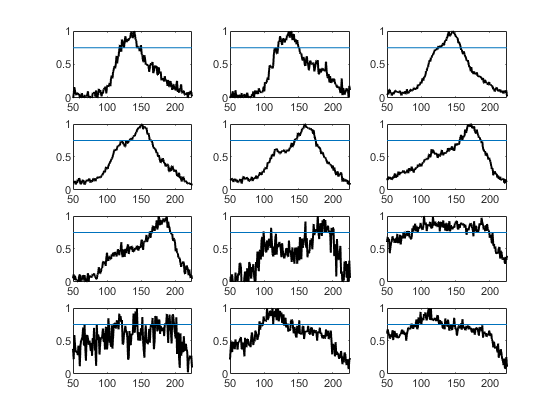

con11PeakLoc = con11PeakLoc*scale;
con11PeakLoc(11) = NaN;
    con11bandW(8) = NaN;
    con11bandW(11) = NaN;
    con11bandW(12) = NaN;
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con12BW = (con12.meanLIC(i).profileraw'-0.08)/(nanmax(con12.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con12BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con12bandW(i) = sum(con12BW(50:225) > perctile)*scale;
    [con12Peak(i) con12PeakLoc(i)] = max(smooth(con12.meanLIC(i).profileraw(50:225)'));
    con12PeakLoc(i) = con12PeakLoc(i)+49;
end

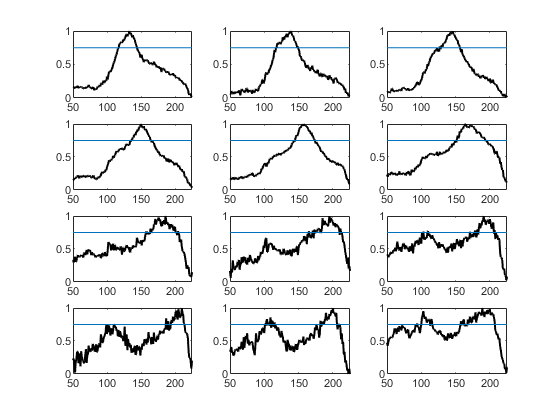

con12PeakLoc = con12PeakLoc*scale;
    con12bandW(8) = NaN;
    con12PeakLoc(8) = NaN;
    con12PeakLoc(9) = NaN;
    con12PeakLoc(10) = NaN;
    con12bandW(9) = NaN;
    con12bandW(10) = NaN;
    con12bandW(11) = NaN;
    con12bandW(12) = NaN;
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con13BW = (con13.meanLIC(i).profileraw'-0.08)/(nanmax(con13.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con13BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con13bandW(i) = sum(con13BW(50:225) > perctile)*scale;
        [con13Peak(i) con13PeakLoc(i)] = max(smooth(con13.meanLIC(i).profileraw(50:225)'));
    con13PeakLoc(i) = con13PeakLoc(i)+49;
end

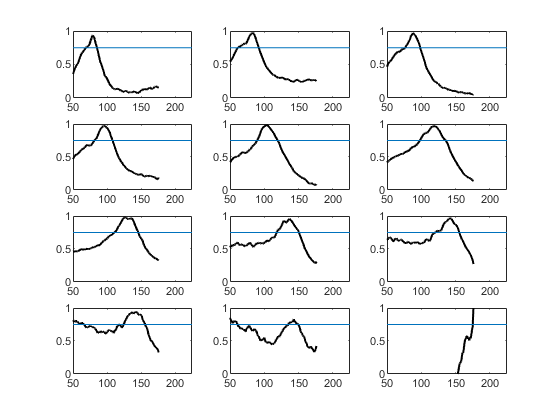

con13PeakLoc = con13PeakLoc*scale;

figure
scale = 6.85; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con14BW = (con14.meanLIC(i).profileraw'-0.08)/(nanmax(con14.meanLIC(i).profileraw(50:225)'-0.08));
    plot(smooth(con14BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con14bandW(i) = sum(con14BW(50:225) > perctile)*scale;
    
    [con14Peak(i) con14PeakLoc(i)] = max(smooth(con14.meanLIC(i).profileraw(50:225)'));
    con14PeakLoc(i) = con14PeakLoc(i)+49;
end

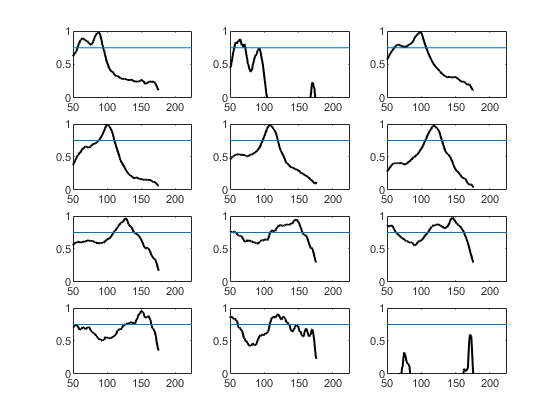

con14PeakLoc = con14PeakLoc*scale;
con14bandW(10)=NaN;
con14PeakLoc(10) = NaN;
con14bandW(12)=NaN;
figure
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con5BW = (con5.meanLIC(i).profileraw'-0.08)/(nanmax(con5.meanLIC(i).profileraw(50:225)'-0.08));
    plot(smooth(con5BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con5bandW(i) = sum(con5BW(50:225) > perctile)*scale;
   [con5Peak(i) con5PeakLoc(i)] = max(smooth(con5.meanLIC(i).profileraw(50:225)'));
    con5PeakLoc(i) = con5PeakLoc(i)+49;
end

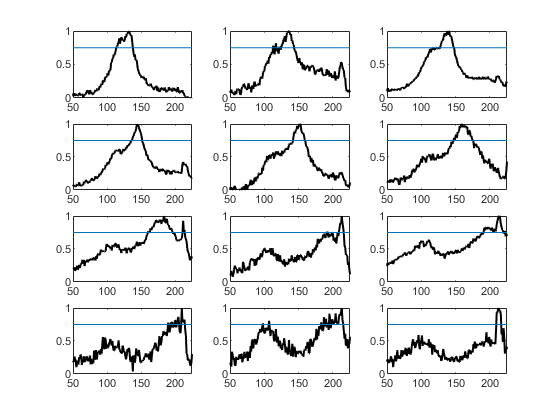

con5PeakLoc = con5PeakLoc*scale;
con5bandW(2)= NaN;
con5PeakLoc(2) = NaN;
con5bandW(8)= NaN;
con5PeakLoc(8) = NaN;
con5bandW(9)= NaN;
con5PeakLoc(9) = NaN;
con5bandW(10)= NaN;
con5PeakLoc(10) = NaN;
con5bandW(12)= NaN;

figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con7BW = (con7.meanLIC(i).profileraw'-0.08)/(nanmax(con7.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con7BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con7bandW(i) = sum(con7BW(50:225) > perctile)*scale;
   [con7Peak(i) con7PeakLoc(i)] = max(smooth(con7.meanLIC(i).profileraw(50:225)'));
    con7PeakLoc(i) = con7PeakLoc(i)+49;
end

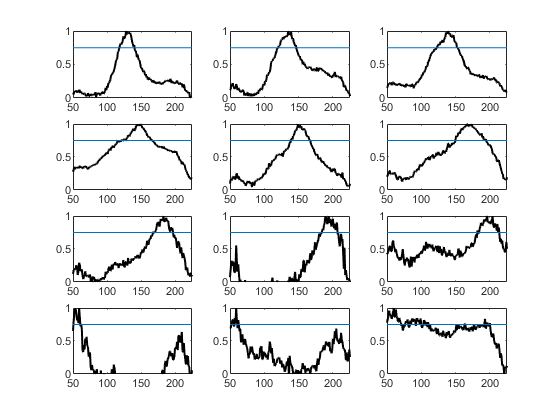

con7PeakLoc = con7PeakLoc*scale;
con7bandW(8) = NaN;
con7PeakLoc(8) = NaN;
con7bandW(9) = NaN;
con7PeakLoc(9) = NaN;
con7bandW(10) = NaN;
con7PeakLoc(10) = NaN;

figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con2BW = (con2.meanLIC(i).profileraw'-0.08)/(nanmax(con2.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con2BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con2bandW(i) = sum(con2BW(50:225) > perctile)*scale;
   [con2Peak(i) con2PeakLoc(i)] = max(smooth(con2.meanLIC(i).profileraw(50:225)'));
    con2PeakLoc(i) = con2PeakLoc(i)+49;
end

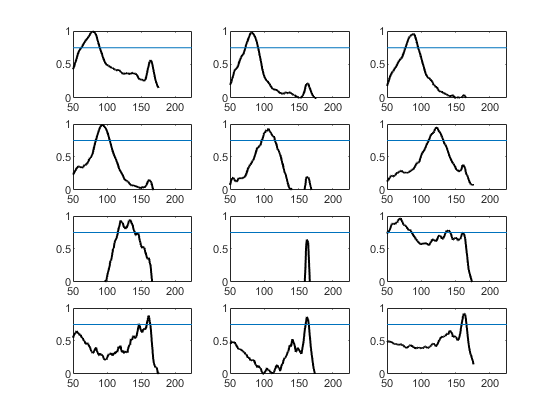

con2PeakLoc = con2PeakLoc*scale;
con2bandW(10) = NaN;
con2PeakLoc(10) = NaN;


figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con15BW = (con15.meanLIC(i).profileraw'-0.08)/(nanmax(con15.meanLIC(i).profileraw(50:225)'-0.08));
    plot(smooth(con15BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con15bandW(i) = sum(con15BW(50:225) > perctile)*scale;
   [con15Peak(i) con15PeakLoc(i)] = max(smooth(con15.meanLIC(i).profileraw(50:225)'));
    con15PeakLoc(i) = con15PeakLoc(i)+49;
end

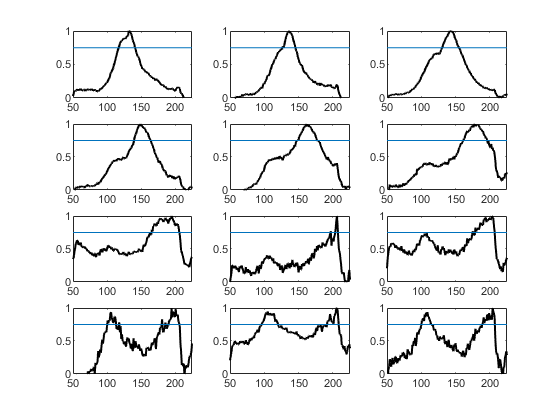

con15PeakLoc = con15PeakLoc*scale;
con15bandW(7) = NaN;
con15PeakLoc(7) = NaN;
con15bandW(8) = NaN;
con15PeakLoc(8) = NaN;
con15bandW(9) = NaN;
con15PeakLoc(9) = NaN;
con15bandW(10) = NaN;
con15PeakLoc(10) = NaN;

figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con16BW = (con16.meanLIC(i).profileraw'-0.08)/(nanmax(con16.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con16BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con16bandW(i) = sum(con16BW(50:225) > perctile)*scale;
   [con16Peak(i) con16PeakLoc(i)] = max(smooth(con16.meanLIC(i).profileraw(50:225)'));
    con16PeakLoc(i) = con16PeakLoc(i)+49;
end

con16PeakLoc = con16PeakLoc*scale;
con16bandW(8) = NaN;
con16PeakLoc(8) = NaN;
con16bandW(10) = NaN;
con16PeakLoc(10) = NaN;

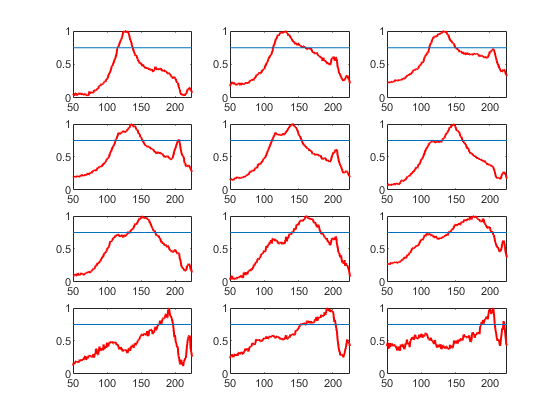


figure
scale = 7.63; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem1BW = (tmem1.meanLIC(i).profileraw'-0.08)/(nanmax(tmem1.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem1BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem1bandW(i) = sum(tmem1BW(50:225) > perctile)*scale;
    [tmem1Peak(i) tmem1PeakLoc(i)] = max(smooth(tmem1.meanLIC(i).profileraw(50:225)'));
    tmem1PeakLoc(i) = tmem1PeakLoc(i)+49;
end

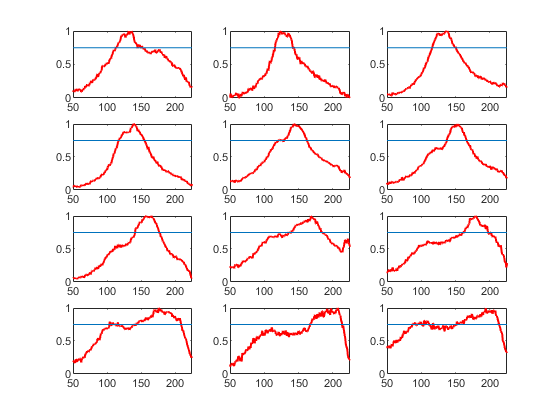

tmem1PeakLoc =  tmem1PeakLoc*scale;
figure
scale = 7.64; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem2BW = (tmem2.meanLIC(i).profileraw'-0.08)/(nanmax(tmem2.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem2BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem2bandW(i) = sum(tmem2BW(50:225) > perctile)*scale;
    [tmem2Peak(i) tmem2PeakLoc(i)] = max(smooth(tmem2.meanLIC(i).profileraw(50:225)'));
    tmem2PeakLoc(i) = tmem2PeakLoc(i)+49;
end

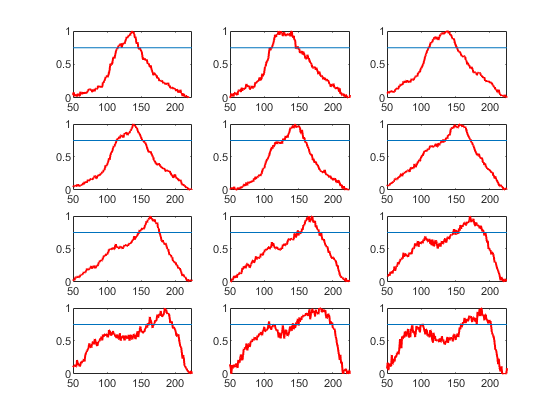

tmem2PeakLoc =  tmem2PeakLoc*scale;
tmem2bandW(10) = NaN;
tmem2PeakLoc(10) = NaN;
figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem3BW = (tmem3.meanLIC(i).profileraw'-0.08)/(nanmax(tmem3.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem3BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem3bandW(i) = sum(tmem3BW(50:225) > perctile)*scale;
    [tmem3Peak(i) tmem3PeakLoc(i)] = max(smooth(tmem3.meanLIC(i).profileraw(50:225)'));
    tmem3PeakLoc(i) = tmem3PeakLoc(i)+49;
end

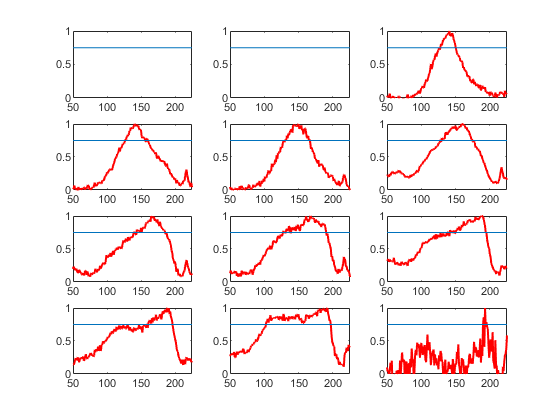

tmem3PeakLoc =  tmem3PeakLoc*scale;
figure
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem6BW = (tmem6.meanLIC(i).profileraw'-0.08)/(nanmax(tmem6.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem6BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem6bandW(i) = sum(tmem6BW(50:225) > perctile)*scale;
    [tmem6Peak(i) tmem6PeakLoc(i)] = max(smooth(tmem6.meanLIC(i).profileraw(50:225)'));
    tmem6PeakLoc(i) = tmem6PeakLoc(i)+49;
end

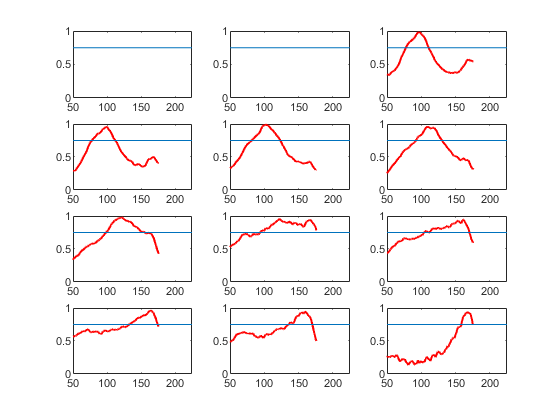

tmem6PeakLoc =  tmem6PeakLoc*scale;
    tmem6bandW(1) = NaN;
    tmem6PeakLoc(1) = NaN;
    tmem6bandW(2) = NaN;
     tmem6PeakLoc(2) = NaN;
    tmem6bandW(12) = NaN;
figure
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem7BW = (tmem7.meanLIC(i).profileraw'-0.08)/(nanmax(tmem7.meanLIC(i).profileraw(50:225)'-0.08));
    plot(smooth(tmem7BW(50:225)),'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem7bandW(i) = sum(tmem7BW(50:225) > perctile)*scale;
    [tmem7Peak(i) tmem7PeakLoc(i)] = max(smooth(tmem7.meanLIC(i).profileraw(50:225)'));
    tmem7PeakLoc(i) = tmem7PeakLoc(i)+49;
end

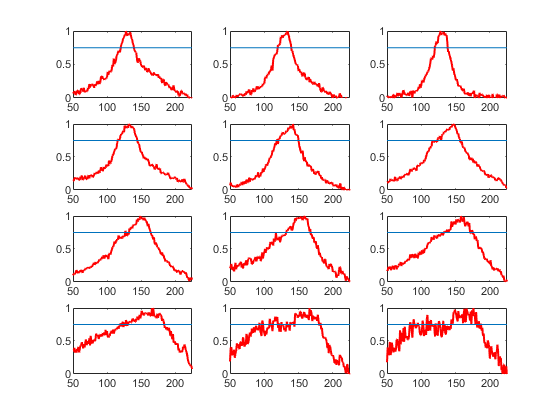

tmem7PeakLoc =  tmem7PeakLoc*scale;
    tmem7bandW(1) = NaN;
    tmem6PeakLoc(1) = NaN;
    tmem7bandW(2) = NaN;
    tmem7bandW(8) = NaN;
    tmem7bandW(9) = NaN;

figure
scale = 7.65; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem5BW = (tmem5.meanLIC(i).profileraw'-0.08)/(nanmax(tmem5.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem5BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem5bandW(i) = sum(tmem5BW(50:225) > perctile)*scale;
    [tmem5Peak(i) tmem5PeakLoc(i)] = max(smooth(tmem5.meanLIC(i).profileraw(50:225)'));
    tmem5PeakLoc(i) = tmem5PeakLoc(i)+49;
end

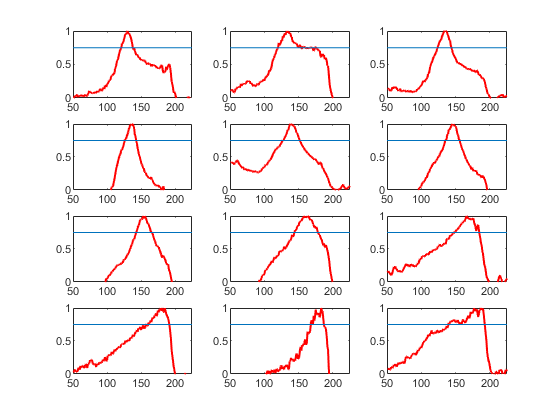

tmem5PeakLoc =  tmem5PeakLoc*scale;
figure
scale = 7.63; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem9BW = (tmem9.meanLIC(i).profileraw'-0.1)/(nanmax(tmem9.meanLIC(i).profileraw(51:225)'-0.1));
    plot(tmem9BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem9bandW(i) = sum(tmem9BW(51:225) > perctile)*scale;
    [tmem9Peak(i) tmem9PeakLoc(i)] = max(smooth(tmem9.meanLIC(i).profileraw(51:225)'));
    tmem9PeakLoc(i) = tmem9PeakLoc(i)+49;
end

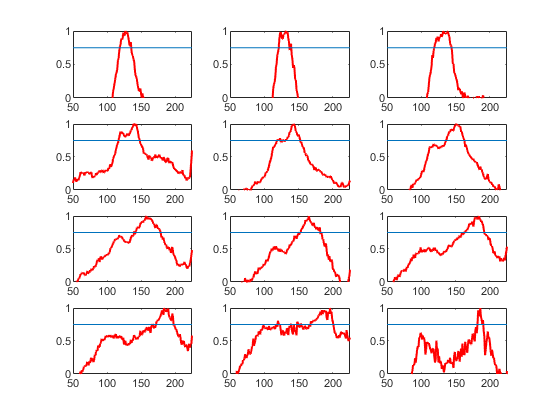

tmem9PeakLoc =  tmem9PeakLoc*scale;
%tmem9bandW(2) = NaN;
%tmem9pk7 = (tmem9PeakLoc(5)-tmem9PeakLoc(1))*scale;
%tmem9pk12 = (tmem9PeakLoc(7)-tmem9PeakLoc(1))*scale;
%tmem9pk15 = (tmem9PeakLoc(8)-tmem9PeakLoc(1))*scale;

figure
scale = 7.62; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem10BW = (tmem10.meanLIC(i).profileraw'-0.1)/(nanmax(tmem10.meanLIC(i).profileraw(51:225)'-0.1));
    plot(tmem10BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem10bandW(i) = sum(tmem10BW(51:225) > perctile)*scale;
    [tmem10Peak(i) tmem10PeakLoc(i)] = max(smooth(tmem10.meanLIC(i).profileraw(51:225)'));
    tmem10PeakLoc(i) = tmem10PeakLoc(i)+49;
end

tmem10PeakLoc =  tmem10PeakLoc*scale;
tmem10bandW(5) = NaN;

% plot peak location (minus 3 kHz)
conMeanMatx = [];
tmemMeanMatx = [];
for i = 1:10
    conMeanLoc(i) = nanmean([con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con2PeakLoc(i),con14PeakLoc(i),con5PeakLoc(i),con7PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)]);
    conMeanMatx = [conMeanMatx;[con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con2PeakLoc(i),con14PeakLoc(i),con5PeakLoc(i),con7PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)]];
    sterrConLoc(i) = nanstd([con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con2PeakLoc(i),con14PeakLoc(i),con5PeakLoc(i),con7PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)])/sqrt(9);
    tmemMeanLoc(i) = nanmean([tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem5PeakLoc(i),tmem9PeakLoc(i),tmem10PeakLoc(i)]);
    tmemMeanMatx = [tmemMeanMatx;[tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem5PeakLoc(i),tmem9PeakLoc(i),tmem10PeakLoc(i)]];
    sterrTmemLoc(i) = nanstd([tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem5PeakLoc(i),tmem9PeakLoc(i),tmem10PeakLoc(i)])/sqrt(6);
end

conMeanLoc20db = conMeanLoc;
tmemMeanLoc20db = tmemMeanLoc;

figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '24 kHz'};
    c1 = shadedErrorBar(k,conMeanLoc-min(conMeanLoc),sterrConLoc)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,tmemMeanLoc-min(tmemMeanLoc),sterrTmemLoc,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


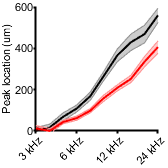

    c2.mainLine.LineWidth = 1.5;
ylim([0 600]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')


genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17'};
mousecko = {'M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
PK = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',conMeanMatx(:,7)',conMeanMatx(:,8)',conMeanMatx(:,9)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)',tmemMeanMatx(:,6)']';

tbl = table(geno,mouse,location,PK,'VariableNames',{'Genotype','Mouse','Location','PK'})

tbl = 150×4 table
    Genotype    Mouse     Location      PK  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }     1023.8
    {'con'}     {'M1'}     {'2' }       1062
    {'con'}     {'M1'}     {'3' }     1100.2
    {'con'}     {'M1'}     {'4' }     1138.4
    {'con'}     {'M1'}     {'5' }     1161.3
    {'con'}     {'M1'}     {'6' }     1260.6
    {'con'}     {'M1'}     {'7' }     1428.7
    {'con'}     {'M1'}     {'8' }     1566.2
    {'con'}     {'M1'}     {'9' }     1619.7
    {'con'}     {'M1'}     {'10'}     1619.7
    {'con'}     {'M2'}     {'1' }     1001.9
    {'con'}     {'M2'}     {'2' }     994.62
    {'con'}     {'M2'}     {'3' }       1060
    {'con'}     {'M2'}     {'4' }       1089
    {'con'}     {'M2'}     {'5' }     1161.6
    {'con'}     {'M2'}     {'6' }     1241.5


lme = fitlme(tbl,'PK~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             131
    Fixed effects coefficients           2
    Random effects coefficients         25
    Covariance parameters                3

Formula:
    PK ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1456.5    1470.8    -723.23          1446.5  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF     pValue        Lower     Upper  
    {'(Intercept)' }         1224.9     55.958     21.889    129    2.8957e-45    1114.2     1335.6
    {'Genotype_cko'}        -81.167       26.3    -3.0863    129     0.0024811    -133.2    -29.133

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type     

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta = 	1.0e+03 *

    1.2249
   -0.0812


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat      DF        pValue        Lower      Upper  
    {'(Intercept)' }         1224.9     55.958     21.889    10.636    3.4467e-10     1101.2     1348.5
    {'Genotype_cko'}        -81.167       26.3    -3.0863    13.074     0.0086228    -137.95    -24.383


perctile = 0.75; % 75th percentile, normalized
conMeanMatx = [];
tmemMeanMatx = [];
for i = 1:10
    conbandW(i) = sum(con(i).norm(50:225) > perctile);
    tmembandW(i) = sum(tmem(i).norm(50:225) > perctile);
    conMean(i) =nanmean([con11bandW(i),con12bandW(i),con13bandW(i),con14bandW(i),con5bandW(i),con2bandW(i),con7bandW(i),con15bandW(i),con16bandW(i)]);
    conMeanMatx = [conMeanMatx;[con11bandW(i),con12bandW(i),con13bandW(i),con14bandW(i),con5bandW(i),con2bandW(i),con7bandW(i),con15bandW(i),con16bandW(i)]];
    tmemMean(i) = nanmean([tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i),tmem5bandW(i),tmem9bandW(i),tmem10bandW(i)]);
    tmemMeanMatx = [tmemMeanMatx;[tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i),tmem5bandW(i),tmem9bandW(i),tmem10bandW(i)]];
    sterrConBW(i) = nanstd([con11bandW(i),con12bandW(i),con13bandW(i),con14bandW(i),con5bandW(i),con2bandW(i),con7bandW(i),con15bandW(i),con16bandW(i)])/sqrt(9);
    sterrtmemBW(i) = nanstd([tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem6bandW(i),tmem7bandW(i),tmem5bandW(i),tmem9bandW(i),tmem10bandW(i)])/sqrt(8);    
end


figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '24 kHz'};
    c1 = shadedErrorBar(k,conMean,sterrConBW)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,tmemMean,sterrtmemBW,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


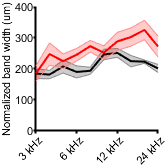

    c2.mainLine.LineWidth = 1.5;
ylim([0 400]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Normalized band width (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M17','M17','M17','M17','M17','M17','M17','M17','M17','M17'};
mousecko = {'M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',conMeanMatx(:,7)',conMeanMatx(:,8)',conMeanMatx(:,9)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)',tmemMeanMatx(:,6)',tmemMeanMatx(:,7)',tmemMeanMatx(:,8)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 170×4 table
    Genotype    Mouse     Location      BW  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }     137.52
    {'con'}     {'M1'}     {'2' }     137.52
    {'con'}     {'M1'}     {'3' }     175.72
    {'con'}     {'M1'}     {'4' }     137.52
    {'con'}     {'M1'}     {'5' }     198.64
    {'con'}     {'M1'}     {'6' }      267.4
    {'con'}     {'M1'}     {'7' }     244.48
    {'con'}     {'M1'}     {'8' }        NaN
    {'con'}     {'M1'}     {'9' }     198.64
    {'con'}     {'M1'}     {'10'}      229.2
    {'con'}     {'M2'}     {'1' }     188.76
    {'con'}     {'M2'}     {'2' }     232.32
    {'con'}     {'M2'}     {'3' }     239.58
    {'con'}     {'M2'}     {'4' }     225.06
    {'con'}     {'M2'}     {'5' }     225.06
    {'con'}     {'M2'}     {'6' }     225.06


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             143
    Fixed effects coefficients           2
    Random effects coefficients         27
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1591.5    1606.2    -790.75          1581.5  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)' }        212.76      13.904    15.303    141    9.1996e-32    185.28    240.25
    {'Genotype_cko'}        51.772      16.864      3.07    141     0.0025687    18.433     85.11

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type           

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =   212.7626
   51.7717


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue      Lower     Upper 
    {'(Intercept)' }        212.76      13.904    15.303    19.677    2.18e-12    183.73     241.8
    {'Genotype_cko'}        51.772      16.864      3.07    14.883    0.007838    15.802    87.741




% get mean BW across all F by mouse
con40Mean = nanmean([conMeanMatx]);
tmem40Mean = nanmean([tmemMeanMatx]);
conditions = {'Control','cKO'};
dim=[1 2];
ylbl = 'Mean bandwidth (um)';
figure
ylim([0 350])

[fig1 p h] = compare2(con40Mean,tmem40Mean,conditions,ylbl,dim)

fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 74
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 0.0045

h = 1

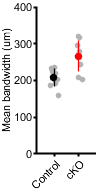

ylim([0 400])

figQuality(gcf,gca,[1 2])

% show overlap 6-12 kHz 

figure
i = 4; %6 khz response
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_1c x1_1c] = nanmax(smooth(con(i).mean(51:225)))

y1_1c = 0.1440

x1_1c = 98

 hold on
 i =7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0780

x2_1c = 128

 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1c+50 x1_1c+50],[0,y1_1c]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0780

x2_1c = 128

 l2_1 = line([x2_1c+50 x2_1c+50],[0,y2_1c]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 y1_1c y1_1c 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])
 
 subplot(1,3,2)
 i = 4;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y1_1 x1_1] = nanmax(smooth(tmem(i).mean(51:225)));
 hold on
 i = 7;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))

y2_1 = 0.1536

x2_1 = 108

 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))

y2_1 = 0.1536

x2_1 = 108

 l2_1 = line([x2_1+50 x2_1+50],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1+50 x1_1+50 x2_1+50 x2_1+50], [0 y2_1 y2_1 0],'r','EdgeColor','none','FaceAlpha',0.1);
figQuality(gcf,gca,[3 1])

i = 4; %3 khz response
subplot(1,3,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_1c x1_1c] = nanmax(smooth(con(i).mean(51:225)));
 hold on
 i =7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0780

x2_1c = 128

 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1c+50 x1_1c+50],[0,y1_1c]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0780

x2_1c = 128

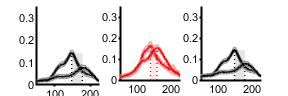

 l2_1 = line([x2_1c+50 x2_1c+50],[0,y2_1c]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 y1_1c y1_1c 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])

%print(gcf,'-dpdf') 

figure
i = 4; %3 khz
subplot(1,3,1)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 7;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1c+50 x1_1c+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'

l1_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [148 148]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l1_1.LineWidth = 1;
 l2_1 = line([x2_1c+50 x2_1c+50],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':'

l2_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [178 178]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 
%cKO
i = 4; %3 khz
subplot(1,3,2)
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    hold on
    i = 7;
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':'

l1_1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [139 139]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+50 x2_1+50],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':'

l2_1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [158 158]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1+50 x1_1+50 x2_1+50 x2_1+50], [0 1 1 0],'r','EdgeColor','none','FaceAlpha',0.1);
i = 4; %3 khz
subplot(1,3,3)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 7;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1c+50 x1_1c+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'

l1_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [148 148]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l1_1.LineWidth = 1;
 l2_1 = line([x2_1c+50 x2_1c+50],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':'

l2_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [178 178]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


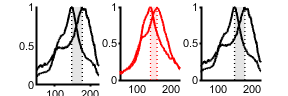

 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 print(gcf,'-dpdf') 

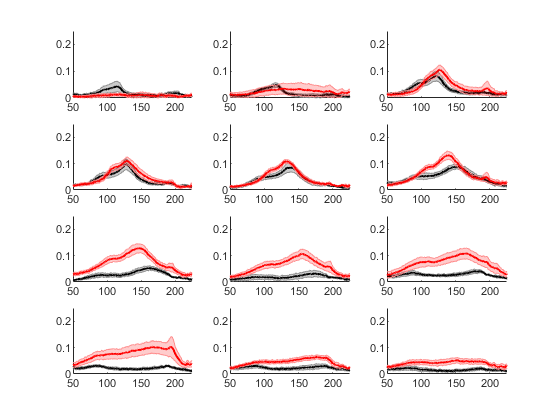

% 65 dB SPL profiles
% centered at 6 kHz

con11 = load('442_1_40dBprofile3khz.mat');
con12 = load('442_2_40dBprofile3khz.mat');
con13 = load('438_1_40dBprofile3khz.mat');
con2 = load('319_3_40dBprofile3khz.mat'); %poor quality
% con7 has blood vessel motion, no 40db for con14, con5 has no 6Khz
con7 = load('346_1_40dBprofile3khz.mat');
con5 = load('338_1_40dBprofile3khz.mat');
con15 = load('493_2_40dBprofile3khz.mat');
con16 = load('504_1_40dBprofile3khz.mat');

tmem1 = load('302_3_40dBprofile3khz.mat');
tmem2 = load('306_3_40dBprofile3khz.mat');
tmem3 = load('338_2_40dBprofile3khz.mat');
tmem5 = load('434_3_40dBprofile3khz.mat');
tmem10 = load('496_2_40dBprofile3khz.mat');
tmem6 = load('440_1_40dBprofile3khz.mat');
tmem7 = load('440_2_40dBprofile3khz.mat');
% tmem6, tmem 7 have no 6 khz response

% check individual profiles
% figure
% for i = 1:12
%     subplot(4,3,i)
%     plot(con2.meanLIC(i).profileraw','k','LineWidth',1.5)
% end

% all freq
figure
tmem = struct();
con = struct();
tecta = struct();
x = [1:1:250];
for i = 1:12
    tmem(i).mean = nanmean([tmem1.meanLIC(i).profileraw';tmem2.meanLIC(i).profileraw';tmem3.meanLIC(i).profileraw';tmem5.meanLIC(i).profileraw';tmem10.meanLIC(i).profileraw';],1)-0.07;
    con(i).mean = nanmean([con11.meanLIC(i).profileraw';con12.meanLIC(i).profileraw';con13.meanLIC(i).profileraw';con15.meanLIC(i).profileraw';con16.meanLIC(i).profileraw';],1)-0.07;
    %tecta(i).mean = nanmean([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)-0.1;
    tmem(i).std = nanstd([tmem1.meanLIC(i).profileraw';tmem2.meanLIC(i).profileraw';tmem3.meanLIC(i).profileraw';tmem5.meanLIC(i).profileraw';tmem10.meanLIC(i).profileraw';],1)/sqrt(5);
    con(i).std = nanstd([con11.meanLIC(i).profileraw';con12.meanLIC(i).profileraw';con13.meanLIC(i).profileraw';con15.meanLIC(i).profileraw';con16.meanLIC(i).profileraw';],1)/sqrt(5);
    %tecta(i).std = nanstd([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)/sqrt(2);
    subplot(4,3,i)
    c1 = shadedErrorBar(x,con(i).mean,con(i).std);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
     % c1 = shadedErrorBar(x,tecta(i).mean,tecta(i).std,'lineprops','b');
    %c1.mainLine.LineWidth = 1.5;
    ylim([0 0.25])
    xlim([50 225])
end

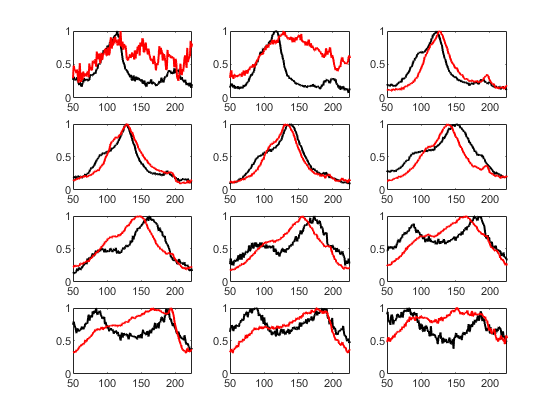


% all freq normalized

% normalized plots 
figure
for i = 1:12
    subplot(4,3,i)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    con(i).norm = con(i).mean/nanmax(con(i).mean(50:225));
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    tmem(i).norm = tmem(i).mean/nanmax(tmem(i).mean(50:225));
   % plot(tecta(i).mean/nanmax(tecta(i).mean(50:225)),'b','LineWidth',1.5)
    % tecta(i).norm = tecta(i).mean/nanmax(tecta(i).mean(50:225));
    ylim([0 1])
    xlim([50 225])
end

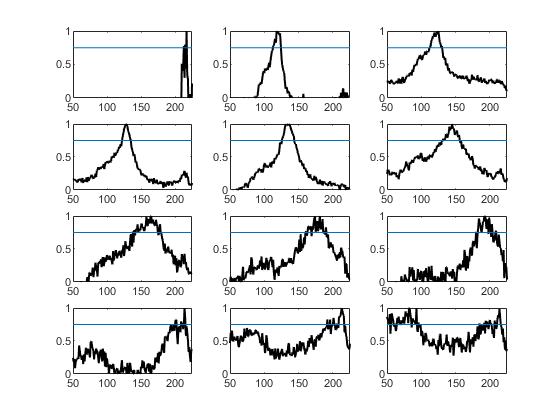

% determine peak location + bandwidth
figure
scale = 7.64; %um/pixel
perctile = 0.75; % 80th percentile, normalized
for i = 1:12
    subplot(4,3,i)
    con11BW = (con11.meanLIC(i).profileraw'-0.08)/(nanmax(con11.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con11BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con11bandW(i) = sum(con11BW(50:225) > perctile)*scale;
    [con11Peak(i) con11PeakLoc(i)] = max(smooth(con11.meanLIC(i).profileraw(50:225)'));
    con11PeakLoc(i) = con11PeakLoc(i)+49;
end

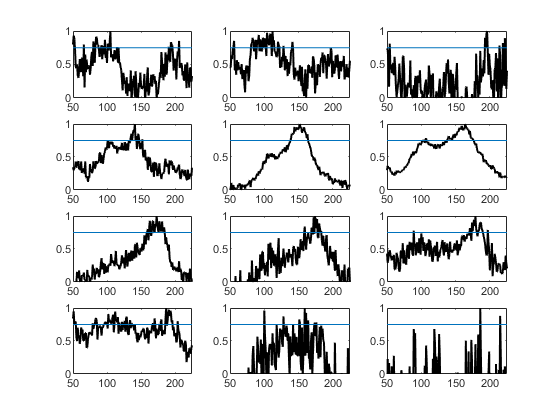

con11PeakLoc = con11PeakLoc*scale;
% con11PeakLoc(11) = NaN;
con1bandW(1) = NaN;
con11bandW(10) = NaN;
%     con11bandW(12) = NaN;
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con12BW = (con12.meanLIC(i).profileraw'-0.08)/(nanmax(con12.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con12BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con12bandW(i) = sum(con12BW(50:225) > perctile)*scale;
    [con12Peak(i) con12PeakLoc(i)] = max(smooth(con12.meanLIC(i).profileraw(50:225)'));
    con12PeakLoc(i) = con12PeakLoc(i)+49;
end

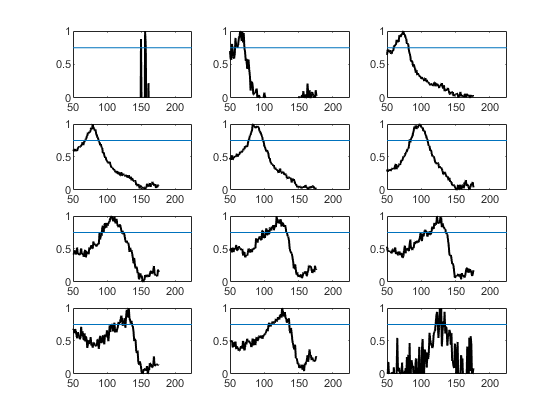

con12PeakLoc = con12PeakLoc*scale;
con12bandW(1) = NaN;
con12bandW(2) = NaN;
con12bandW(3) = NaN;
     con12bandW(4) = NaN;
%     con12PeakLoc(8) = NaN;
%     con12PeakLoc(9) = NaN;
     con12PeakLoc(10) = NaN;
     con12bandW(8) = NaN;
     con12bandW(9) = NaN;
     con12bandW(10) = NaN;
figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con13BW = (con13.meanLIC(i).profileraw'-0.08)/(nanmax(con13.meanLIC(i).profileraw(50:225)'-0.08));
    plot((con13BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con13bandW(i) = sum(con13BW(50:225) > perctile)*scale;
        [con13Peak(i) con13PeakLoc(i)] = max(smooth(con13.meanLIC(i).profileraw(50:225)'));
    con13PeakLoc(i) = con13PeakLoc(i)+49;
end

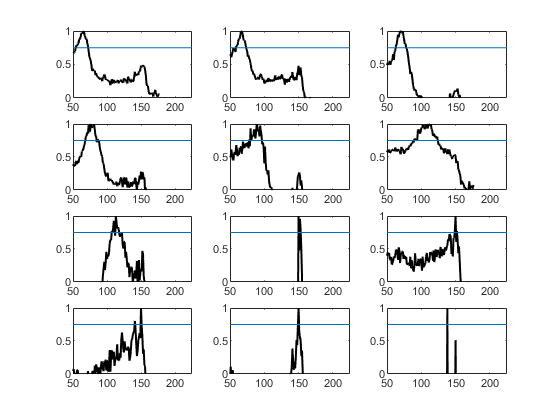

con13PeakLoc = con13PeakLoc*scale;
con13bandW(1) = NaN;
con13bandW(2) = NaN;

     figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con15BW = (con15.meanLIC(i).profileraw'-0.08)/(nanmax(con15.meanLIC(i).profileraw(50:225)'-0.08));
    plot((con15BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con15bandW(i) = sum(con15BW(50:225) > perctile)*scale;
   [con15Peak(i) con15PeakLoc(i)] = max(smooth(con15.meanLIC(i).profileraw(50:225)'));
    con15PeakLoc(i) = con15PeakLoc(i)+49;
end

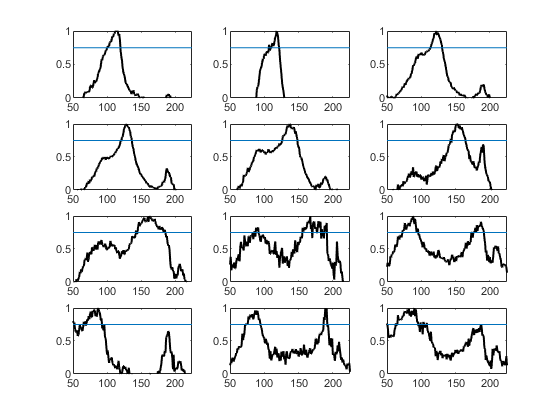

con15PeakLoc = con15PeakLoc*scale;
con15bandW(7) = NaN;
con15PeakLoc(7) = NaN;
con15bandW(8) = NaN;
con15PeakLoc(8) = NaN;
con15bandW(9) = NaN;
con15PeakLoc(9) = NaN;
con15bandW(10) = NaN;
con15PeakLoc(10) = NaN;
figure;
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con16BW = (con16.meanLIC(i).profileraw'-0.08)/(nanmax(con16.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con16BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con16bandW(i) = sum(con16BW(50:225) > perctile)*scale;
   [con16Peak(i) con16PeakLoc(i)] = max(smooth(con16.meanLIC(i).profileraw(50:225)'));
    con16PeakLoc(i) = con16PeakLoc(i)+49;
end

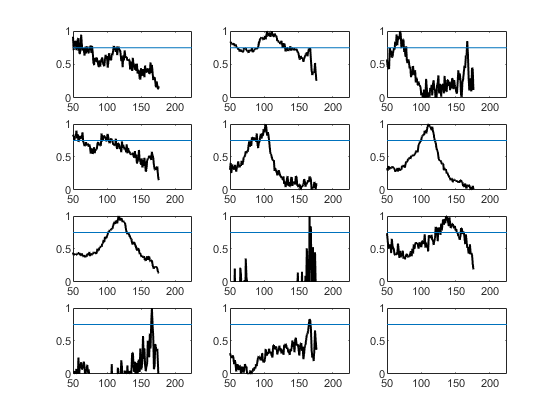

con16PeakLoc = con16PeakLoc*scale;
con16bandW(1) = NaN;
con16bandW(2) = NaN;
con16bandW(8) = NaN;
con16PeakLoc(8) = NaN;
con16bandW(9) = NaN;
con16PeakLoc(9) = NaN;
con16bandW(10) = NaN;
con16PeakLoc(10) = NaN;

figure
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con5BW = (con5.meanLIC(i).profileraw'-0.08)/(nanmax(con5.meanLIC(i).profileraw(50:225)'-0.08));
    plot((con5BW(50:225)),'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con5bandW(i) = sum(con5BW(50:225) > perctile)*scale;
   [con5Peak(i) con5PeakLoc(i)] = max(smooth(con5.meanLIC(i).profileraw(50:225)'));
    con5PeakLoc(i) = con5PeakLoc(i)+49;
end

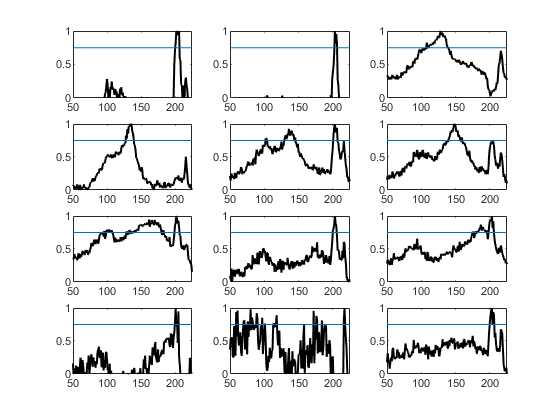

con5PeakLoc = con5PeakLoc*scale;
 con5bandW(1:5)= NaN;
 con5bandW(8:12)= NaN;
 
figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con7BW = (con7.meanLIC(i).profileraw'-0.08)/(nanmax(con7.meanLIC(i).profileraw(50:225)'-0.08));
    plot(con7BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con7bandW(i) = sum(con7BW(50:225) > perctile)*scale;
   [con7Peak(i) con7PeakLoc(i)] = max(smooth(con7.meanLIC(i).profileraw(50:225)'));
    con7PeakLoc(i) = con7PeakLoc(i)+49;
end

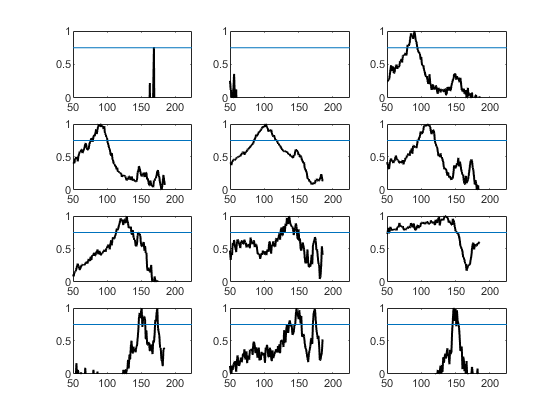

con7PeakLoc = con7PeakLoc*scale;
con7bandW(1:2) = NaN;
con7bandW(5) = NaN;
con7bandW(7:12) = NaN;

figure
scale = 7.26; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con2BW = (con2.meanLIC(i).profileraw'-0.08)/(nanmax(con2.meanLIC(i).profileraw(30:170)'-0.08));
    plot(con2BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con2bandW(i) = sum(con2BW(30:170) > perctile)*scale;
   [con2Peak(i) con2PeakLoc(i)] = max(smooth(con2.meanLIC(i).profileraw(30:170)'));
    con2PeakLoc(i) = con2PeakLoc(i)+49;
end

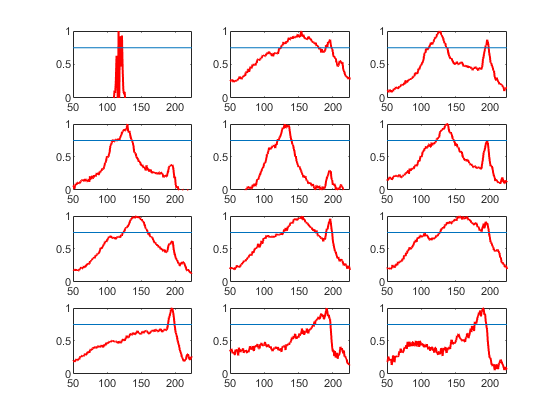

con2PeakLoc = con2PeakLoc*scale;
con2bandW(1:2) = NaN;
con2bandW(9:12) = NaN;

figure
scale = 7.63; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem1BW = (tmem1.meanLIC(i).profileraw'-0.08)/(nanmax(tmem1.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem1BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem1bandW(i) = sum(tmem1BW(50:225) > perctile)*scale;
    [tmem1Peak(i) tmem1PeakLoc(i)] = max(smooth(tmem1.meanLIC(i).profileraw(50:225)'));
    tmem1PeakLoc(i) = tmem1PeakLoc(i)+49;
end

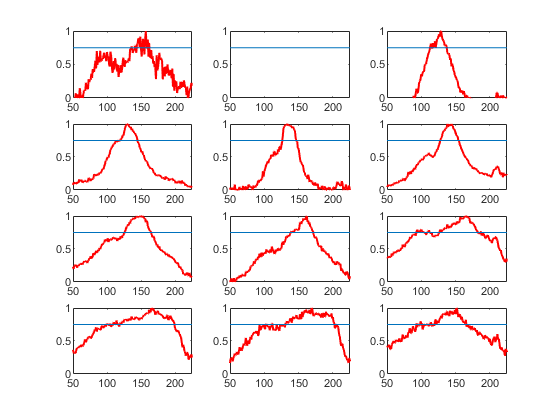

tmem1PeakLoc =  tmem1PeakLoc*scale;
tmem1PeakLoc(10) = NaN;
tmem1bandW(1) = NaN;
tmem1bandW(2) = NaN;
tmem1bandW(3) = NaN;
tmem1bandW(9) = NaN;
tmem1bandW(10) = NaN;

figure
scale = 7.64; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem2BW = (tmem2.meanLIC(i).profileraw'-0.08)/(nanmax(tmem2.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem2BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem2bandW(i) = sum(tmem2BW(50:225) > perctile)*scale;
    [tmem2Peak(i) tmem2PeakLoc(i)] = max(smooth(tmem2.meanLIC(i).profileraw(50:225)'));
    tmem2PeakLoc(i) = tmem2PeakLoc(i)+49;
end

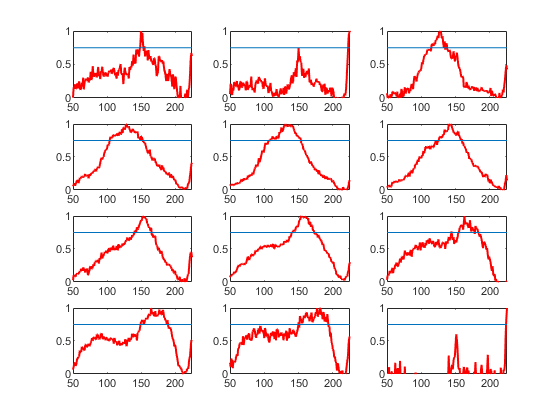

tmem2PeakLoc =  tmem2PeakLoc*scale;
tmem2bandW(1) = NaN;
tmem2bandW(2) = NaN;
tmem2bandW(3) = NaN;
tmem2bandW(10) = NaN;
figure
scale = 7.66; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem3BW = (tmem3.meanLIC(i).profileraw'-0.08)/(nanmax(tmem3.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem3BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem3bandW(i) = sum(tmem3BW(50:225) > perctile)*scale;
    [tmem3Peak(i) tmem3PeakLoc(i)] = max(smooth(tmem3.meanLIC(i).profileraw(50:225)'));
    tmem3PeakLoc(i) = tmem3PeakLoc(i)+49;
end

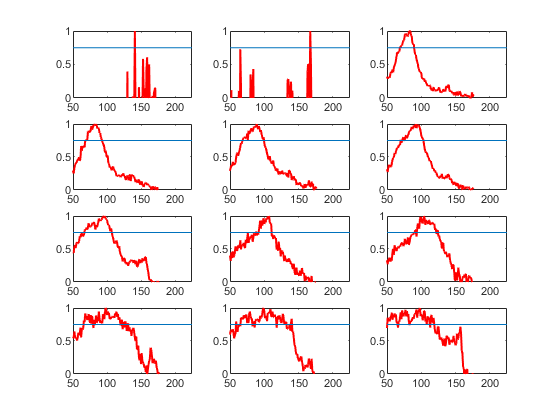

tmem3PeakLoc =  tmem3PeakLoc*scale;
tmem3PeakLoc(10) = NaN;
tmem3bandW(1) = NaN;
tmem3bandW(2) = NaN;

figure
scale = 7.65; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem5BW = (tmem5.meanLIC(i).profileraw'-0.08)/(nanmax(tmem5.meanLIC(i).profileraw(50:225)'-0.08));
    plot((tmem5BW(50:225)),'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem5bandW(i) = sum(tmem5BW(50:225) > perctile)*scale;
    [tmem5Peak(i) tmem5PeakLoc(i)] = max(smooth(tmem5.meanLIC(i).profileraw(50:225)'));
    tmem5PeakLoc(i) = tmem5PeakLoc(i)+49;
end

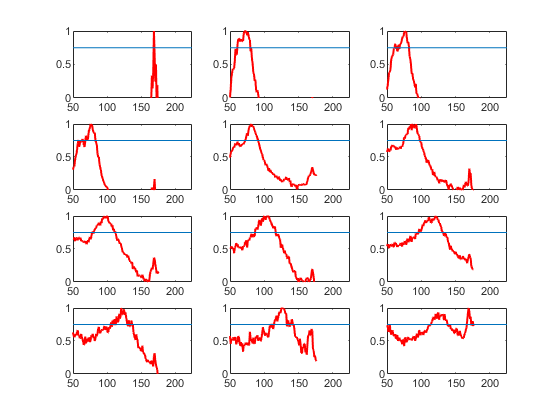

tmem5PeakLoc =  tmem5PeakLoc*scale;
tmem5PeakLoc(10) = NaN;
tmem5bandW(1) = NaN;
tmem5bandW(2) = NaN;
tmem5bandW(10) = NaN;

figure
scale = 7.62; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem10BW = (tmem10.meanLIC(i).profileraw'-0.08)/(nanmax(tmem10.meanLIC(i).profileraw(50:225)'-0.08));
    plot((tmem10BW(50:225)),'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem10bandW(i) = sum(tmem10BW(50:225) > perctile)*scale;
    [tmem10Peak(i) tmem10PeakLoc(i)] = max(smooth(tmem10.meanLIC(i).profileraw(50:225)'));
    tmem10PeakLoc(i) = tmem10PeakLoc(i)+49;
end

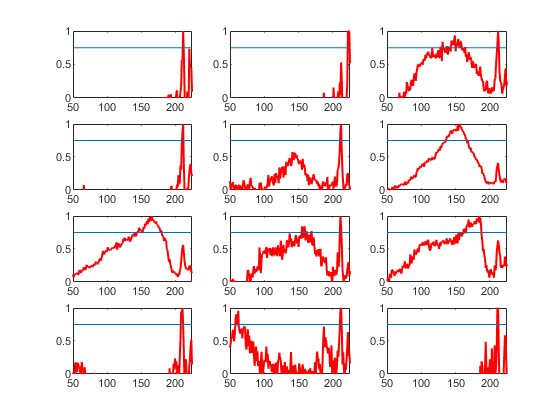

tmem10PeakLoc =  tmem10PeakLoc*scale;
tmem10bandW(1) = NaN;
tmem10bandW(2) = NaN;
tmem10bandW(3) = NaN;
tmem10bandW(10) = NaN;

figure
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem6BW = (tmem6.meanLIC(i).profileraw'-0.08)/(nanmax(tmem6.meanLIC(i).profileraw(50:225)'-0.08));
    plot(tmem6BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem6bandW(i) = sum(tmem6BW(50:225) > perctile)*scale;
    [tmem6Peak(i) tmem6PeakLoc(i)] = max(smooth(tmem6.meanLIC(i).profileraw(50:225)'));
    tmem6PeakLoc(i) = tmem6PeakLoc(i)+49;
end

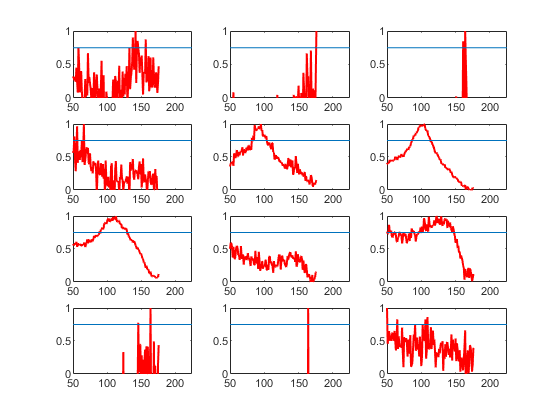

tmem6PeakLoc =  tmem6PeakLoc*scale;
    tmem6bandW(1:5) = NaN;
    tmem6bandW(8) = NaN;
    tmem6bandW(10:12) = NaN;
figure
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    tmem7BW = (tmem7.meanLIC(i).profileraw'-0.08)/(nanmax(tmem7.meanLIC(i).profileraw(50:225)'-0.08));
    plot((tmem7BW(50:225)),'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    tmem7bandW(i) = sum(tmem7BW(50:225) > perctile)*scale;
    [tmem7Peak(i) tmem7PeakLoc(i)] = max(smooth(tmem7.meanLIC(i).profileraw(50:225)'));
    tmem7PeakLoc(i) = tmem7PeakLoc(i)+49;
end

tmem7PeakLoc =  tmem7PeakLoc*scale;
    tmem7bandW(1:4) = NaN;
    tmem7bandW(8:12) = NaN;


% plot peak distance from 6 kHz peak
conMeanMatx = [];
tmemMeanMatx = [];
for i = 4:10
    conMeanLoc(i) = nanmean([con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)]);
    conMeanMatx = [conMeanMatx;[con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)]];
    sterrConLoc(i) = nanstd([con11PeakLoc(i),con12PeakLoc(i),con13PeakLoc(i),con15PeakLoc(i),con16PeakLoc(i)])/sqrt(5);
    tmemMeanLoc(i) = nanmean([tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem5PeakLoc(i),tmem10PeakLoc(i)]);
    tmemMeanMatx = [tmemMeanMatx; [tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem5PeakLoc(i),tmem10PeakLoc(i)]];
    sterrTmemLoc(i) = nanstd([tmem1PeakLoc(i),tmem2PeakLoc(i),tmem3PeakLoc(i),tmem5PeakLoc(i),tmem10PeakLoc(i)])/sqrt(5);
end

conMeanLoc40db = conMeanLoc;
tmemMeanLoc40db = tmemMeanLoc;
sterrConLoc40db = sterrConLoc;
sterrTmemLoc40db = sterrTmemLoc;

figure
k = 1:1:10;
conditions = {'3 kHz','6 kHz', '12 kHz', '19 kHz'};
    c1 = shadedErrorBar(k,conMeanLoc-(conMeanLoc(4)),sterrConLoc)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,tmemMeanLoc-(tmemMeanLoc(4)),sterrTmemLoc,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


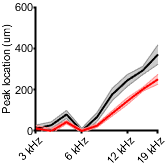

    c2.mainLine.LineWidth = 1.5;
ylim([0 600]);
xlim([1 9]);
xticks([1 4 7 9])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')


genoBasecon = {'con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M10','M10','M10','M10','M10','M10','M10'};
mousecko = {'M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9',};
mouse = [mousecon,mousecko]';
locationBase = {'4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
PK = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)']';

tbl = table(geno,mouse,location,PK,'VariableNames',{'Genotype','Mouse','Location','PK'})

tbl = 70×4 table
    Genotype    Mouse     Location      PK  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'4' }     977.92
    {'con'}     {'M1'}     {'5' }     1031.4
    {'con'}     {'M1'}     {'6' }     1107.8
    {'con'}     {'M1'}     {'7' }     1245.3
    {'con'}     {'M1'}     {'8' }     1314.1
    {'con'}     {'M1'}     {'9' }     1466.9
    {'con'}     {'M1'}     {'10'}     1627.3
    {'con'}     {'M2'}     {'4' }     1009.1
    {'con'}     {'M2'}     {'5' }     1103.5
    {'con'}     {'M2'}     {'6' }     1190.6
    {'con'}     {'M2'}     {'7' }       1256
    {'con'}     {'M2'}     {'8' }     1263.2
    {'con'}     {'M2'}     {'9' }     1292.3
    {'con'}     {'M2'}     {'10'}        NaN
    {'con'}     {'M3'}     {'4' }     929.28
    {'con'}     {'M3'}     {'5' }     972.84


lme = fitlme(tbl,'PK~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              59
    Fixed effects coefficients           2
    Random effects coefficients         17
    Covariance parameters                3

Formula:
    PK ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    661.05    671.27    -325.53          651.05  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF    pValue        Lower      Upper  
    {'(Intercept)' }         1204.3     55.845     21.566    57    4.2987e-29     1092.5     1316.2
    {'Genotype_cko'}        -69.528      23.32    -2.9815    57     0.0042133    -116.23    -22.831

Random effects covariance parameters (95% CIs):
Group: Location (7 Levels)
    Name1                  Name2                  Type      

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta = 	1.0e+03 *

    1.2043
   -0.0695


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat      DF        pValue        Lower      Upper  
    {'(Intercept)' }         1204.3     55.845     21.566     6.917    1.3362e-07       1072     1336.7
    {'Genotype_cko'}        -69.528      23.32    -2.9815    8.8437      0.015709    -122.42    -16.633


% 40 dB atten bandwidth estimate

perctile = 0.75; % 75th percentile, normalized
conMeanMatx = [];
tmemMeanMatx = [];
for i = 3:10
    conbandW(i) = sum(con(i).norm(50:225) > perctile);
    tmembandW(i) = sum(tmem(i).norm(50:225) > perctile);
    conMean(i) =nanmean([con11bandW(i),con12bandW(i),con13bandW(i),con15bandW(i),con16bandW(i),con5bandW(i),con7bandW(i),con2bandW(i)]);
    conMeanMatx = [conMeanMatx;[con11bandW(i),con12bandW(i),con13bandW(i),con15bandW(i),con16bandW(i),con5bandW(i),con7bandW(i),con2bandW(i)]];
    tmemMean(i) = nanmean([tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem5bandW(i),tmem10bandW(i),tmem6bandW(i),tmem7bandW(i)]);
    tmemMeanMatx = [tmemMeanMatx; [tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem5bandW(i),tmem10bandW(i),tmem6bandW(i),tmem7bandW(i)]];
    sterrConBW(i) = nanstd([con11bandW(i),con12bandW(i),con13bandW(i),con15bandW(i),con16bandW(i),con5bandW(i),con7bandW(i),con2bandW(i)])/sqrt(7);
    sterrtmemBW(i) = nanstd([tmem1bandW(i),tmem2bandW(i),tmem3bandW(i),tmem5bandW(i),tmem10bandW(i),tmem6bandW(i),tmem7bandW(i)])/sqrt(6);    
end
conMean(1) = NaN;
conMean(2) = NaN;
tmemMean(1) = NaN;
tmemMean(2) = NaN;
figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '24 kHz'};
    c1 = shadedErrorBar(k,conMean,sterrConBW)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,tmemMean,sterrtmemBW,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


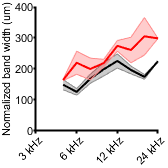

    c2.mainLine.LineWidth = 1.5;
ylim([0 400]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Normalized band width (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

% get mean BW across all F by mouse
con40Mean = nanmean([conMeanMatx]);
tmem40Mean = nanmean([tmemMeanMatx]);
conditions = {'Control','cKO'};
dim=[1 2];
ylbl = 'Mean bandwidth (um)';
figure
[fig2 p h] = compare2(con40Mean,tmem40Mean,conditions,ylbl,dim)

fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 1.6523e-04

h = 1

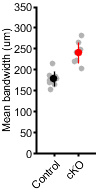

ylim([0 350])
figQuality(gcf,gca,[1 2])

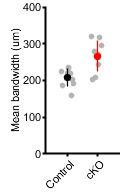

subP = handleTheSubplot({fig1,fig2},[1 2]);

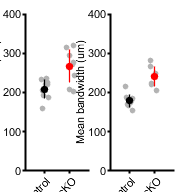

ylim([0 400])
%yticks([0 50 100 150 200 250 300 350])
figQuality(subP,gca,[1.8 1.8])
ylim([0 400])

%yticks([0 50 100 150 200 250 300 350])


genoBasecon = {'con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13',};
mousecko = {'M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M14','M14','M14','M14','M14','M14','M14','M14','M15','M15','M15','M15','M15','M15','M15','M15',};
mouse = [mousecon,mousecko]';
locationBase = {'3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
PK = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',conMeanMatx(:,7)',conMeanMatx(:,8)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)',tmemMeanMatx(:,6)',tmemMeanMatx(:,7)']';

tbl = table(geno,mouse,location,PK,'VariableNames',{'Genotype','Mouse','Location','PK'})

tbl = 120×4 table
    Genotype    Mouse     Location      PK  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'3' }     145.16
    {'con'}     {'M1'}     {'4' }      99.32
    {'con'}     {'M1'}     {'5' }     137.52
    {'con'}     {'M1'}     {'6' }     206.28
    {'con'}     {'M1'}     {'7' }      267.4
    {'con'}     {'M1'}     {'8' }     206.28
    {'con'}     {'M1'}     {'9' }     160.44
    {'con'}     {'M1'}     {'10'}        NaN
    {'con'}     {'M2'}     {'3' }        NaN
    {'con'}     {'M2'}     {'4' }        NaN
    {'con'}     {'M2'}     {'5' }      181.5
    {'con'}     {'M2'}     {'6' }     304.92
    {'con'}     {'M2'}     {'7' }     159.72
    {'con'}     {'M2'}     {'8' }        NaN
    {'con'}     {'M2'}     {'9' }        NaN
    {'con'}     {'M2'}     {'10'}        NaN


lme = fitlme(tbl,'PK~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              76
    Fixed effects coefficients           2
    Random effects coefficients         23
    Covariance parameters                3

Formula:
    PK ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    856.16    867.68    -423.08          846.16  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)' }        183.59      15.242    12.045    74    4.0814e-19    153.22    213.96
    {'Genotype_cko'}        57.488       15.61    3.6827    74    0.00043621    26.384    88.593

Random effects covariance parameters (95% CIs):
Group: Location (8 Levels)
    Name1                  Name2                  Type           Esti

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =   183.5924
   57.4882


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }        183.59      15.242    12.045    11.169    9.6159e-08    150.11    217.08
    {'Genotype_cko'}        57.488       15.61    3.6827    69.735    0.00045162    26.352    88.624


% for figure
i = 4; %6 khz response
figure
subplot(1,4,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean));
 l1_1 = line([x1_1 x1_1],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
 i = 6; %9.5 kHz
 subplot(1,4,2)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con(i).mean(50:225)));
 l1_2 = line([x1_2+49 x1_2+49],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':';
 l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(tmem(i).mean(50:225)));
 l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  patch([x1_2+49 x1_2+49 x2_2+49 x2_2+49], [0 y2_2 y2_2 0],'k','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[3 1])
  i = 8; % 15 kHz
 subplot(1,4,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_3 x1_3] = nanmax(smooth(con(i).mean(50:225)));
 l1_3 = line([x1_3+49 x1_3+49],[0,y1_3]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':';
 l1_3.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y2_3 x2_3] = nanmax(smooth(tmem(i).mean(50:225)));
 l2_3 = line([x2_3+49 x2_3+49],[0,y2_3]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':';
 l2_3.LineWidth = 1;
 ylim([0 0.35])
 xlim([50 225])
 patch([x1_3+49 x1_3+49 x2_3+49 x2_3+49], [0 y2_3 y2_3 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[4 1])
 i = 4; %6 khz response
subplot(1,4,4)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean));
 l1_1 = line([x1_1 x1_1],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(50:225)))
 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
  figQuality(gcf,gca,[4 1])
%print(gcf,'-dpdf')


figure
i = 4; %6 khz norm
subplot(1,4,1)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1 x1_1],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
i = 6; %12 khz norm
subplot(1,4,2)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
     l1_2 = line([x1_2+49 x1_2+49],[0,1]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':';
 l1_2.LineWidth = 1;
 l2_2 = line([x2_2+49 x2_2+49],[0,1]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
 patch([x1_2+49 x1_2+49 x2_2+49 x2_2+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[4 1])
  i = 8; %15 khz norm
subplot(1,4,3)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225]) 
         l1_3 = line([x1_3+49 x1_3+49],[0,1]);
 l1_3.Color = 'k';
 l1_3.LineStyle = ':';
 l1_3.LineWidth = 1;
 l2_3 = line([x2_3+49 x2_3+49],[0,1]);
 l2_3.Color = 'r';
 l2_3.LineStyle = ':';
 l2_3.LineWidth = 1;
    patch([x1_3+49 x1_3+49 x2_3+49 x2_3+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
figQuality(gcf,gca,[3 1])
i = 4; %6 khz norm
subplot(1,4,4)
    plot(con(i).mean/nanmax(con(i).mean(50:225)),'k','LineWidth',1.5)
    hold on
    plot(tmem(i).mean/nanmax(tmem(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1 x1_1],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[4 1])
% print(gcf,'-dpdf') 
 

% show overlap 6-12 kHz 

figure
i = 4; %6 khz response
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_1c x1_1c] = nanmax(smooth(con(i).mean(51:225)))

y1_1c = 0.0961

x1_1c = 78

 hold on
 i =7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0524

x2_1c = 112

 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1c+50 x1_1c+50],[0,y1_1c]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0524

x2_1c = 112

 l2_1 = line([x2_1c+50 x2_1c+50],[0,y2_1c]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 y1_1c y1_1c 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])
 
 subplot(1,3,2)
 i = 4;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
  [y1_1 x1_1] = nanmax(smooth(tmem(i).mean(51:225)));
 hold on
 i = 7;
 c1 = shadedErrorBar(x,tmem(i).mean,tmem(i).std,'lineprops','r');
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))

y2_1 = 0.1273

x2_1 = 98

 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1 x2_1] = nanmax(smooth(tmem(i).mean(51:225)))

y2_1 = 0.1273

x2_1 = 98

 l2_1 = line([x2_1+50 x2_1+50],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1+50 x1_1+50 x2_1+50 x2_1+50], [0 y2_1 y2_1 0],'r','EdgeColor','none','FaceAlpha',0.1);
figQuality(gcf,gca,[3 1])

i = 4; %3 khz response
subplot(1,3,3)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
  [y1_1c x1_1c] = nanmax(smooth(con(i).mean(51:225)));
 hold on
 i =7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0524

x2_1c = 112

 c1.mainLine.LineWidth = 1.5;
    l1_1 = line([x1_1c+50 x1_1c+50],[0,y1_1c]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1c x2_1c] = nanmax(smooth(con(i).mean(51:225)))

y2_1c = 0.0524

x2_1c = 112

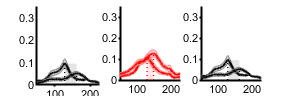

 l2_1 = line([x2_1c+50 x2_1c+50],[0,y2_1c]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.35])
 xlim([50 225])
 patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 y1_1c y1_1c 0],'k','EdgeColor','none','FaceAlpha',0.1);
 figQuality(gcf,gca,[3 1])

%print(gcf,'-dpdf') 

figure
i = 4; %3 khz
subplot(1,3,1)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 7;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1c+50 x1_1c+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'

l1_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [128 128]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l1_1.LineWidth = 1;
 l2_1 = line([x2_1c+50 x2_1c+50],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':'

l2_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [162 162]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
 
%cKO
i = 4; %3 khz
subplot(1,3,2)
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    hold on
    i = 7;
    plot(tmem(i).mean/nanmax(tmem(i).mean(51:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':'

l1_1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [129 129]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+50 x2_1+50],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':'

l2_1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [148 148]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1+50 x1_1+50 x2_1+50 x2_1+50], [0 1 1 0],'r','EdgeColor','none','FaceAlpha',0.1);
i = 4; %3 khz
subplot(1,3,3)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    i = 7;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1c+50 x1_1c+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':'

l1_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [128 128]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


 l1_1.LineWidth = 1;
 l2_1 = line([x2_1c+50 x2_1c+50],[0,1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':'

l2_1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [162 162]
              YData: [0 1]
              ZData: [1×0 double]

  Show all properties


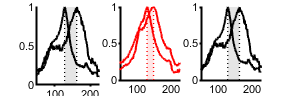

 l2_1.LineWidth = 1;
 figQuality(gcf,gca,[3 1])
patch([x1_1c+50 x1_1c+50 x2_1c+50 x2_1c+50], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
% print(gcf,'-dpdf') 

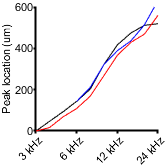


% reviewer figure - spatial location with sound level 

% control 
figure
k = 1:1:10;
hold on
conditions = {'3 kHz','6 kHz', '12 kHz', '24 kHz'};
    plot(k,conMeanLoc0db-(conMeanLoc0db(1)),'k')
   hold on
 plot(k,conMeanLoc20db-(conMeanLoc20db(1)),'r')
k = 4:1:10;
  plot(k,(conMeanLoc40db(4:10)-conMeanLoc40db(4)+(conMeanLoc0db(4)-conMeanLoc0db(1))),'b')
    
ylim([0 600]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

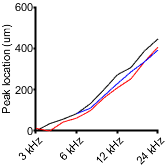

% cko 
figure
k = 1:1:10;
hold on
conditions = {'3 kHz','6 kHz', '12 kHz', '24 kHz'};
    plot(k,tmemMeanLoc0db-(tmemMeanLoc0db(1)),'k')
   hold on
 plot(k,tmemMeanLoc20db-(min(tmemMeanLoc20db)),'r')
k = 4:1:10;
  plot(k,(tmemMeanLoc40db(4:10)-tmemMeanLoc40db(4)+(tmemMeanLoc0db(4)-tmemMeanLoc0db(1))),'b')
    
ylim([0 600]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])